clear;
Sigma_temp = [];
H_temp = [];

for j = 0 : 6 %Graet_0 ~ Great_x
    Sigma = zeros(1);
    H_1 = [];
    k = 1;
    for w = 8 : 11
        for w_1 = 0 : 9
            c = ['B_P' num2str(j) '_' num2str(w) '_' num2str(w_1)]; %Branch_Parameter
            c_1 = ['D:\Qt_projects\data6\Great\Great_' num2str(j) '\B_P' num2str(w) '.' num2str(w_1) '00000.dat'];
            a = ['Bold' num2str(j) '_' num2str(w) '_' num2str(w_1)]; %Bold_Signal
            a_1 = ['D:\Qt_projects\data6\Great\Great_' num2str(j) '\Bold' num2str(w) '.' num2str(w_1) '00000.dat'];
            
            %importdata
            if exist(c_1, 'fiLe') == 2 && exist(a_1, 'fiLe') == 2
                e = importdata(c_1);
                eval([c '=e']);
                Sigma(k) = eval(c);
                d = importdata(a_1);
                eval([a '=d']);
                f = eval(a);
                
                for i = 1 : length(f(:, 1))
                    H1 = HurstCompute(f(i, :));
                    H2(i) = H1(1);
                end
                
                H_1(k) = mean(H2);
                k = k + 1;
            end
        end
    end
    
    Sigma_temp = [Sigma_temp; Sigma];
    H_temp = [H_temp; H_1];
end

B_P0_8_0 = 0.3581

Bold0_8_0 =     0.0251    0.0204    0.0201    0.0226    0.0219    0.0217    0.0231    0.0213    0.0224    0.0185    0.0211    0.0219    0.0216    0.0241    0.0201    0.0230    0.0206    0.0265    0.0207    0.0217    0.0218    0.0223    0.0239    0.0192    0.0245    0.0234    0.0219    0.0242    0.0208    0.0232    0.0214    0.0218    0.0203    0.0228    0.0221    0.0228    0.0213    0.0253    0.0202    0.0228    0.0213    0.0215    0.0226    0.0227    0.0244    0.0224    0.0210    0.0226    0.0214    0.0219
    0.0276    0.0239    0.0195    0.0230    0.0234    0.0221    0.0246    0.0220    0.0221    0.0217    0.0226    0.0210    0.0208    0.0217    0.0198    0.0231    0.0226    0.0224    0.0207    0.0249    0.0224    0.0206    0.0216    0.0213    0.0206    0.0219    0.0209    0.0242    0.0204    0.0235    0.0205    0.0235    0.0220    0.0197    0.0222    0.0231    0.0204    0.0234    0.0218    0.0219    0.0218    0.0200    0.0217    0.0231    0.0192    0.0256    0.0196    0.0223    0.0

B_P0_8_1 = 0.2490

Bold0_8_1 =     0.0255    0.0186    0.0233    0.0217    0.0227    0.0194    0.0246    0.0214    0.0220    0.0205    0.0208    0.0240    0.0208    0.0208    0.0207    0.0225    0.0216    0.0250    0.0194    0.0248    0.0216    0.0235    0.0235    0.0246    0.0208    0.0239    0.0211    0.0247    0.0224    0.0233    0.0218    0.0214    0.0227    0.0219    0.0204    0.0225    0.0228    0.0199    0.0245    0.0246    0.0197    0.0213    0.0206    0.0216    0.0250    0.0211    0.0217    0.0222    0.0228    0.0214
    0.0272    0.0234    0.0218    0.0200    0.0249    0.0225    0.0208    0.0216    0.0234    0.0207    0.0192    0.0228    0.0226    0.0236    0.0265    0.0214    0.0220    0.0223    0.0233    0.0231    0.0214    0.0226    0.0212    0.0222    0.0249    0.0211    0.0251    0.0216    0.0230    0.0244    0.0214    0.0226    0.0208    0.0213    0.0202    0.0223    0.0235    0.0233    0.0248    0.0196    0.0229    0.0199    0.0209    0.0228    0.0227    0.0240    0.0239    0.0213    0.0

B_P0_8_2 = 0.2703

Bold0_8_2 =     0.0266    0.0229    0.0214    0.0217    0.0259    0.0197    0.0210    0.0287    0.0169    0.0228    0.0218    0.0217    0.0224    0.0220    0.0194    0.0239    0.0190    0.0225    0.0232    0.0211    0.0222    0.0239    0.0227    0.0208    0.0224    0.0223    0.0255    0.0207    0.0237    0.0208    0.0213    0.0229    0.0238    0.0211    0.0204    0.0234    0.0231    0.0191    0.0251    0.0213    0.0238    0.0216    0.0192    0.0224    0.0220    0.0225    0.0216    0.0242    0.0209    0.0207
    0.0274    0.0255    0.0210    0.0210    0.0231    0.0265    0.0211    0.0226    0.0266    0.0236    0.0223    0.0251    0.0213    0.0238    0.0215    0.0225    0.0230    0.0226    0.0247    0.0231    0.0241    0.0212    0.0242    0.0225    0.0221    0.0234    0.0197    0.0236    0.0205    0.0213    0.0235    0.0246    0.0223    0.0229    0.0232    0.0269    0.0213    0.0224    0.0227    0.0224    0.0228    0.0201    0.0243    0.0216    0.0250    0.0239    0.0206    0.0217    0.0

B_P0_8_3 = 0.2920

Bold0_8_3 =     0.0270    0.0231    0.0219    0.0211    0.0246    0.0201    0.0226    0.0192    0.0224    0.0217    0.0234    0.0209    0.0223    0.0222    0.0220    0.0269    0.0199    0.0241    0.0235    0.0195    0.0250    0.0220    0.0259    0.0236    0.0220    0.0215    0.0193    0.0217    0.0237    0.0218    0.0243    0.0206    0.0210    0.0212    0.0206    0.0210    0.0228    0.0238    0.0204    0.0215    0.0228    0.0201    0.0220    0.0252    0.0200    0.0211    0.0226    0.0229    0.0208    0.0225
    0.0284    0.0221    0.0254    0.0208    0.0192    0.0235    0.0255    0.0220    0.0224    0.0198    0.0271    0.0229    0.0225    0.0235    0.0223    0.0203    0.0178    0.0214    0.0244    0.0213    0.0221    0.0212    0.0204    0.0233    0.0237    0.0252    0.0221    0.0215    0.0236    0.0226    0.0239    0.0224    0.0242    0.0221    0.0251    0.0183    0.0204    0.0216    0.0218    0.0211    0.0229    0.0227    0.0235    0.0261    0.0233    0.0197    0.0210    0.0238    0.0

B_P0_8_4 = 0.2889

Bold0_8_4 =     0.0280    0.0228    0.0207    0.0245    0.0231    0.0231    0.0203    0.0208    0.0235    0.0205    0.0251    0.0231    0.0202    0.0224    0.0243    0.0208    0.0233    0.0229    0.0246    0.0232    0.0191    0.0234    0.0219    0.0249    0.0248    0.0234    0.0233    0.0263    0.0203    0.0230    0.0252    0.0194    0.0202    0.0244    0.0216    0.0211    0.0221    0.0249    0.0220    0.0217    0.0213    0.0236    0.0209    0.0212    0.0221    0.0226    0.0234    0.0194    0.0237    0.0232
    0.0275    0.0207    0.0218    0.0245    0.0272    0.0215    0.0236    0.0232    0.0207    0.0270    0.0210    0.0255    0.0217    0.0208    0.0203    0.0213    0.0228    0.0232    0.0216    0.0229    0.0201    0.0238    0.0215    0.0227    0.0219    0.0239    0.0224    0.0247    0.0227    0.0227    0.0261    0.0227    0.0208    0.0226    0.0205    0.0248    0.0238    0.0213    0.0217    0.0207    0.0226    0.0217    0.0227    0.0251    0.0223    0.0219    0.0227    0.0218    0.0

B_P0_8_5 = 0.3151

Bold0_8_5 =     0.0310    0.0234    0.0189    0.0221    0.0201    0.0214    0.0240    0.0234    0.0226    0.0267    0.0203    0.0225    0.0246    0.0212    0.0296    0.0260    0.0219    0.0243    0.0247    0.0190    0.0252    0.0216    0.0231    0.0213    0.0218    0.0247    0.0215    0.0208    0.0209    0.0269    0.0197    0.0211    0.0215    0.0242    0.0224    0.0225    0.0225    0.0235    0.0260    0.0234    0.0246    0.0243    0.0214    0.0223    0.0203    0.0217    0.0231    0.0227    0.0236    0.0243
    0.0300    0.0215    0.0215    0.0246    0.0208    0.0278    0.0223    0.0239    0.0226    0.0205    0.0228    0.0226    0.0235    0.0228    0.0252    0.0229    0.0221    0.0249    0.0246    0.0187    0.0221    0.0208    0.0222    0.0251    0.0179    0.0236    0.0244    0.0210    0.0230    0.0255    0.0186    0.0225    0.0243    0.0219    0.0220    0.0200    0.0245    0.0209    0.0247    0.0248    0.0222    0.0207    0.0218    0.0233    0.0249    0.0226    0.0207    0.0214    0.0

B_P0_8_6 = 0.3660

Bold0_8_6 =     0.0324    0.0193    0.0227    0.0192    0.0214    0.0216    0.0258    0.0214    0.0222    0.0229    0.0248    0.0194    0.0239    0.0239    0.0248    0.0240    0.0218    0.0220    0.0208    0.0194    0.0231    0.0205    0.0196    0.0243    0.0228    0.0224    0.0223    0.0219    0.0214    0.0233    0.0231    0.0236    0.0229    0.0206    0.0227    0.0228    0.0219    0.0231    0.0217    0.0199    0.0217    0.0236    0.0218    0.0218    0.0203    0.0223    0.0223    0.0226    0.0214    0.0270
    0.0285    0.0222    0.0222    0.0211    0.0240    0.0186    0.0222    0.0231    0.0238    0.0229    0.0273    0.0216    0.0243    0.0269    0.0237    0.0193    0.0245    0.0206    0.0216    0.0215    0.0215    0.0246    0.0243    0.0220    0.0280    0.0258    0.0252    0.0247    0.0239    0.0215    0.0237    0.0193    0.0237    0.0242    0.0246    0.0213    0.0263    0.0257    0.0205    0.0247    0.0260    0.0260    0.0211    0.0225    0.0241    0.0267    0.0241    0.0215    0.0

B_P0_8_7 = 0.4052

Bold0_8_7 =     0.0296    0.0210    0.0235    0.0252    0.0216    0.0252    0.0228    0.0263    0.0230    0.0222    0.0262    0.0259    0.0226    0.0218    0.0224    0.0208    0.0269    0.0218    0.0254    0.0274    0.0206    0.0234    0.0251    0.0264    0.0282    0.0241    0.0227    0.0287    0.0243    0.0192    0.0238    0.0224    0.0251    0.0236    0.0245    0.0283    0.0199    0.0225    0.0210    0.0226    0.0239    0.0227    0.0237    0.0286    0.0213    0.0261    0.0219    0.0220    0.0277    0.0198
    0.0314    0.0219    0.0263    0.0244    0.0241    0.0241    0.0266    0.0231    0.0236    0.0255    0.0224    0.0215    0.0230    0.0256    0.0244    0.0251    0.0215    0.0225    0.0247    0.0233    0.0208    0.0247    0.0226    0.0209    0.0232    0.0253    0.0239    0.0246    0.0228    0.0236    0.0288    0.0219    0.0244    0.0232    0.0237    0.0237    0.0206    0.0238    0.0235    0.0244    0.0236    0.0220    0.0229    0.0247    0.0249    0.0224    0.0192    0.0256    0.0

B_P0_8_8 = 0.6370

Bold0_8_8 =     0.0297    0.0198    0.0221    0.0252    0.0283    0.0233    0.0221    0.0198    0.0248    0.0216    0.0211    0.0249    0.0249    0.0239    0.0231    0.0285    0.0238    0.0236    0.0240    0.0221    0.0234    0.0237    0.0251    0.0228    0.0250    0.0225    0.0242    0.0216    0.0261    0.0255    0.0229    0.0280    0.0222    0.0235    0.0254    0.0213    0.0238    0.0200    0.0261    0.0232    0.0228    0.0222    0.0244    0.0245    0.0218    0.0217    0.0230    0.0243    0.0230    0.0238
    0.0326    0.0188    0.0241    0.0229    0.0214    0.0235    0.0222    0.0249    0.0229    0.0236    0.0226    0.0214    0.0252    0.0185    0.0238    0.0250    0.0251    0.0237    0.0244    0.0222    0.0235    0.0219    0.0228    0.0203    0.0249    0.0229    0.0258    0.0242    0.0231    0.0239    0.0235    0.0217    0.0211    0.0246    0.0233    0.0236    0.0198    0.0245    0.0238    0.0196    0.0262    0.0233    0.0268    0.0207    0.0248    0.0223    0.0231    0.0239    0.0

B_P0_8_9 = 0.4582

Bold0_8_9 =     0.0304    0.0197    0.0233    0.0232    0.0208    0.0255    0.0225    0.0235    0.0228    0.0217    0.0199    0.0250    0.0240    0.0232    0.0231    0.0228    0.0245    0.0211    0.0259    0.0238    0.0226    0.0238    0.0232    0.0293    0.0240    0.0228    0.0239    0.0250    0.0265    0.0257    0.0183    0.0254    0.0267    0.0190    0.0240    0.0212    0.0240    0.0216    0.0231    0.0293    0.0232    0.0281    0.0225    0.0212    0.0222    0.0223    0.0244    0.0249    0.0213    0.0229
    0.0379    0.0238    0.0225    0.0251    0.0237    0.0266    0.0242    0.0217    0.0260    0.0221    0.0219    0.0245    0.0237    0.0221    0.0244    0.0231    0.0232    0.0245    0.0213    0.0296    0.0233    0.0250    0.0205    0.0240    0.0216    0.0231    0.0218    0.0238    0.0240    0.0236    0.0202    0.0227    0.0230    0.0219    0.0240    0.0212    0.0239    0.0228    0.0229    0.0246    0.0226    0.0239    0.0232    0.0210    0.0216    0.0245    0.0227    0.0222    0.0

B_P0_9_0 = 0.9467

Bold0_9_0 =     0.0322    0.0188    0.0240    0.0239    0.0225    0.0224    0.0231    0.0216    0.0243    0.0210    0.0246    0.0223    0.0247    0.0225    0.0242    0.0245    0.0224    0.0253    0.0222    0.0223    0.0227    0.0201    0.0241    0.0245    0.0229    0.0248    0.0206    0.0251    0.0228    0.0208    0.0232    0.0212    0.0227    0.0253    0.0182    0.0227    0.0245    0.0244    0.0196    0.0226    0.0239    0.0249    0.0187    0.0234    0.0205    0.0211    0.0241    0.0296    0.0198    0.0261
    0.0349    0.0246    0.0208    0.0245    0.0240    0.0240    0.0255    0.0234    0.0225    0.0282    0.0215    0.0235    0.0254    0.0244    0.0251    0.0231    0.0244    0.0251    0.0240    0.0273    0.0210    0.0254    0.0242    0.0196    0.0217    0.0244    0.0247    0.0223    0.0240    0.0239    0.0268    0.0265    0.0221    0.0247    0.0204    0.0212    0.0269    0.0246    0.0269    0.0236    0.0217    0.0232    0.0230    0.0267    0.0218    0.0212    0.0244    0.0247    0.0

B_P0_9_1 = 0.6451

Bold0_9_1 =     0.0368    0.0210    0.0248    0.0248    0.0239    0.0248    0.0261    0.0216    0.0240    0.0242    0.0218    0.0240    0.0234    0.0229    0.0271    0.0248    0.0228    0.0241    0.0225    0.0242    0.0229    0.0229    0.0237    0.0258    0.0229    0.0194    0.0260    0.0216    0.0261    0.0218    0.0236    0.0220    0.0232    0.0220    0.0245    0.0218    0.0242    0.0214    0.0265    0.0235    0.0254    0.0226    0.0258    0.0240    0.0240    0.0258    0.0232    0.0248    0.0237    0.0273
    0.0378    0.0212    0.0240    0.0246    0.0214    0.0252    0.0229    0.0220    0.0253    0.0228    0.0265    0.0246    0.0228    0.0246    0.0263    0.0229    0.0261    0.0248    0.0216    0.0209    0.0266    0.0226    0.0218    0.0268    0.0227    0.0230    0.0257    0.0263    0.0261    0.0211    0.0257    0.0252    0.0231    0.0234    0.0236    0.0261    0.0227    0.0320    0.0186    0.0280    0.0245    0.0241    0.0263    0.0226    0.0253    0.0247    0.0275    0.0218    0.0

B_P0_9_2 = 1.1128

Bold0_9_2 =     0.0415    0.0350    0.0189    0.0250    0.0240    0.0233    0.0247    0.0231    0.0232    0.0265    0.0223    0.0235    0.0247    0.0213    0.0285    0.0213    0.0255    0.0250    0.0212    0.0254    0.0277    0.0250    0.0249    0.0200    0.0242    0.0232    0.0246    0.0260    0.0257    0.0255    0.0265    0.0208    0.0234    0.0250    0.0245    0.0213    0.0246    0.0236    0.0211    0.0247    0.0263    0.0245    0.0229    0.0263    0.0246    0.0236    0.0264    0.0249    0.0220    0.0222
    0.0383    0.0203    0.0247    0.0258    0.0188    0.0235    0.0201    0.0236    0.0245    0.0274    0.0269    0.0249    0.0248    0.0252    0.0212    0.0267    0.0226    0.0283    0.0199    0.0257    0.0206    0.0212    0.0195    0.0242    0.0235    0.0264    0.0231    0.0223    0.0241    0.0254    0.0229    0.0242    0.0231    0.0231    0.0235    0.0220    0.0235    0.0251    0.0255    0.0240    0.0252    0.0249    0.0223    0.0239    0.0242    0.0233    0.0268    0.0250    0.0

B_P0_9_3 = 0.5825

Bold0_9_3 =     0.0386    0.0181    0.0258    0.0234    0.0293    0.0194    0.0280    0.0250    0.0229    0.0237    0.0243    0.0275    0.0227    0.0232    0.0242    0.0281    0.0271    0.0241    0.0221    0.0227    0.0311    0.0236    0.0235    0.0221    0.0274    0.0244    0.0232    0.0243    0.0225    0.0265    0.0236    0.0220    0.0229    0.0240    0.0277    0.0214    0.0235    0.0236    0.0220    0.0251    0.0250    0.0274    0.0229    0.0221    0.0235    0.0265    0.0252    0.0240    0.0205    0.0259
    0.0386    0.0236    0.0260    0.0196    0.0243    0.0246    0.0313    0.0285    0.0258    0.0243    0.0252    0.0271    0.0214    0.0231    0.0315    0.0336    0.0250    0.0207    0.0238    0.0240    0.0263    0.0263    0.0276    0.0212    0.0255    0.0261    0.0197    0.0251    0.0240    0.0284    0.0243    0.0278    0.0286    0.0322    0.0397    0.0209    0.0263    0.0261    0.0303    0.0225    0.0238    0.0267    0.0238    0.0242    0.0253    0.0237    0.0233    0.0272    0.0

B_P0_9_4 = 0.6403

Bold0_9_4 =     0.0383    0.0203    0.0261    0.0226    0.0239    0.0217    0.0234    0.0219    0.0216    0.0267    0.0214    0.0222    0.0243    0.0239    0.0225    0.0278    0.0241    0.0242    0.0265    0.0243    0.0264    0.0233    0.0273    0.0242    0.0245    0.0230    0.0255    0.0251    0.0242    0.0242    0.0216    0.0236    0.0228    0.0225    0.0226    0.0252    0.0232    0.0204    0.0247    0.0219    0.0235    0.0228    0.0263    0.0203    0.0253    0.0261    0.0270    0.0274    0.0221    0.0232
    0.0423    0.0141    0.0284    0.0343    0.0234    0.0235    0.0260    0.0220    0.0270    0.0257    0.0207    0.0247    0.0231    0.0284    0.0202    0.0211    0.0258    0.0236    0.0236    0.0252    0.0291    0.0201    0.0243    0.0260    0.0282    0.0225    0.0240    0.0251    0.0246    0.0250    0.0253    0.0245    0.0251    0.0217    0.0244    0.0262    0.0259    0.0204    0.0251    0.0314    0.0212    0.0238    0.0269    0.0299    0.0208    0.0225    0.0345    0.0209    0.0

B_P0_9_5 = 1.1837

Bold0_9_5 =     0.0354    0.0238    0.0267    0.0233    0.0302    0.0139    0.0208    0.0254    0.0220    0.0265    0.0254    0.0269    0.0248    0.0213    0.0213    0.0256    0.0286    0.0283    0.0229    0.0266    0.0253    0.0234    0.0256    0.0211    0.0238    0.0251    0.0222    0.0245    0.0220    0.0182    0.0221    0.0234    0.0216    0.0267    0.0227    0.0258    0.0219    0.0250    0.0252    0.0243    0.0255    0.0221    0.0233    0.0237    0.0239    0.0257    0.0197    0.0249    0.0252    0.0229
    0.0428    0.0196    0.0322    0.0262    0.0212    0.0280    0.0240    0.0269    0.0248    0.0251    0.0251    0.0240    0.0245    0.0273    0.0234    0.0240    0.0274    0.0241    0.0247    0.0243    0.0234    0.0253    0.0231    0.0279    0.0229    0.0253    0.0262    0.0227    0.0261    0.0358    0.0144    0.0262    0.0234    0.0244    0.0238    0.0211    0.0239    0.0251    0.0248    0.0220    0.0277    0.0225    0.0278    0.0228    0.0235    0.0282    0.0249    0.0254    0.0

B_P0_9_6 = 1.1513

Bold0_9_6 =     0.0393    0.0220    0.0250    0.0251    0.0242    0.0238    0.0254    0.0172    0.0221    0.0232    0.0234    0.0218    0.0262    0.0248    0.0227    0.0260    0.0232    0.0272    0.0228    0.0259    0.0285    0.0229    0.0224    0.0224    0.0249    0.0260    0.0251    0.0215    0.0235    0.0202    0.0270    0.0243    0.0230    0.0256    0.0205    0.0240    0.0243    0.0258    0.0293    0.0266    0.0206    0.0228    0.0202    0.0230    0.0283    0.0219    0.0238    0.0221    0.0231    0.0220
    0.0424    0.0203    0.0250    0.0224    0.0231    0.0230    0.0238    0.0290    0.0207    0.0264    0.0242    0.0247    0.0266    0.0269    0.0209    0.0264    0.0239    0.0220    0.0265    0.0273    0.0230    0.0289    0.0204    0.0217    0.0269    0.0356    0.0218    0.0246    0.0283    0.0255    0.0231    0.0277    0.0248    0.0270    0.0276    0.0257    0.0330    0.0277    0.0206    0.0263    0.0226    0.0239    0.0208    0.0227    0.0296    0.0247    0.0262    0.0236    0.0

B_P0_9_7 = 1.5039

Bold0_9_7 =     0.0442    0.0131    0.0269    0.0251    0.0242    0.0271    0.0231    0.0258    0.0225    0.0249    0.0253    0.0239    0.0248    0.0271    0.0263    0.0247    0.0249    0.0250    0.0285    0.0245    0.0286    0.0253    0.0210    0.0228    0.0205    0.0219    0.0272    0.0252    0.0240    0.0269    0.0247    0.0250    0.0226    0.0256    0.0236    0.0242    0.0257    0.0264    0.0249    0.0260    0.0263    0.0289    0.0232    0.0277    0.0384    0.0272    0.0264    0.0209    0.0240    0.0279
    0.0460    0.0210    0.0248    0.0230    0.0267    0.0246    0.0329    0.0339    0.0243    0.0291    0.0275    0.0237    0.0242    0.0264    0.0263    0.0292    0.0254    0.0237    0.0279    0.0231    0.0244    0.0225    0.0191    0.0260    0.0231    0.0254    0.0216    0.0278    0.0285    0.0210    0.0257    0.0260    0.0242    0.0359    0.0233    0.0267    0.0289    0.0258    0.0257    0.0240    0.0279    0.0222    0.0242    0.0280    0.0385    0.0238    0.0350    0.0329    0.0

B_P0_9_8 = 1.3067

Bold0_9_8 =     0.0397    0.0260    0.0249    0.0232    0.0250    0.0281    0.0208    0.0246    0.0318    0.0245    0.0231    0.0278    0.0224    0.0307    0.0241    0.0258    0.0222    0.0247    0.0235    0.0261    0.0218    0.0230    0.0221    0.0259    0.0231    0.0246    0.0234    0.0266    0.0248    0.0230    0.0237    0.0256    0.0222    0.0279    0.0264    0.0255    0.0243    0.0267    0.0243    0.0254    0.0232    0.0272    0.0226    0.0275    0.0222    0.0220    0.0247    0.0261    0.0238    0.0267
    0.0418    0.0194    0.0352    0.0205    0.0244    0.0279    0.0249    0.0273    0.0220    0.0302    0.0222    0.0193    0.0269    0.0272    0.0250    0.0246    0.0247    0.0268    0.0167    0.0232    0.0235    0.0224    0.0349    0.0196    0.0245    0.0231    0.0276    0.0228    0.0261    0.0280    0.0352    0.0287    0.0315    0.0259    0.0297    0.0241    0.0239    0.0250    0.0246    0.0217    0.0260    0.0229    0.0234    0.0244    0.0252    0.0314    0.0216    0.0288    0.0

B_P0_9_9 = 0.9946

Bold0_9_9 =     0.0415    0.0254    0.0262    0.0218    0.0181    0.0273    0.0234    0.0360    0.0379    0.0172    0.0340    0.0215    0.0240    0.0270    0.0295    0.0186    0.0229    0.0259    0.0280    0.0387    0.0155    0.0257    0.0251    0.0262    0.0243    0.0233    0.0266    0.0294    0.0217    0.0255    0.0258    0.0303    0.0254    0.0230    0.0229    0.0260    0.0244    0.0226    0.0215    0.0255    0.0244    0.0218    0.0228    0.0230    0.0250    0.0262    0.0212    0.0242    0.0270    0.0242
    0.0467    0.0048    0.0396    0.0133    0.0263    0.0223    0.0268    0.0252    0.0316    0.0204    0.0221    0.0206    0.0229    0.0246    0.0191    0.0403    0.0131    0.0238    0.0243    0.0292    0.0292    0.0329    0.0237    0.0292    0.0201    0.0239    0.0258    0.0259    0.0238    0.0260    0.0245    0.0219    0.0242    0.0253    0.0262    0.0301    0.0338    0.0207    0.0261    0.0284    0.0189    0.0324    0.0450    0.0199    0.0264    0.0240    0.0275    0.0228    0.0

B_P0_10_0 = 1.7939

Bold0_10_0 =     0.0475    0.0306    0.0161    0.0249    0.0234    0.0281    0.0257    0.0245    0.0237    0.0268    0.0265    0.0205    0.0259    0.0243    0.0257    0.0263    0.0253    0.0323    0.0241    0.0234    0.0320    0.0274    0.0263    0.0234    0.0240    0.0253    0.0220    0.0278    0.0234    0.0245    0.0280    0.0215    0.0255    0.0257    0.0239    0.0282    0.0240    0.0244    0.0273    0.0217    0.0288    0.0223    0.0245    0.0274    0.0232    0.0253    0.0379    0.0222    0.0250    0.0246
    0.0472    0.0126    0.0287    0.0277    0.0274    0.0257    0.0265    0.0231    0.0264    0.0238    0.0255    0.0275    0.0246    0.0246    0.0294    0.0282    0.0302    0.0231    0.0227    0.0275    0.0247    0.0226    0.0257    0.0246    0.0254    0.0242    0.0275    0.0268    0.0249    0.0209    0.0198    0.0275    0.0261    0.0299    0.0232    0.0298    0.0289    0.0320    0.0186    0.0321    0.0355    0.0402    0.0226    0.0313    0.0272    0.0295    0.0426    0.0308    0.

B_P0_10_1 = 1.6803

Bold0_10_1 =     0.0447    0.0149    0.0256    0.0215    0.0255    0.0251    0.0276    0.0254    0.0246    0.0232    0.0275    0.0254    0.0244    0.0238    0.0241    0.0224    0.0272    0.0241    0.0222    0.0258    0.0224    0.0253    0.0225    0.0263    0.0281    0.0258    0.0254    0.0247    0.0254    0.0237    0.0221    0.0224    0.0248    0.0225    0.0225    0.0219    0.0252    0.0241    0.0307    0.0220    0.0257    0.0232    0.0228    0.0330    0.0243    0.0255    0.0304    0.0222    0.0259    0.0257
    0.0449    0.0149    0.0221    0.0238    0.0286    0.0248    0.0234    0.0270    0.0243    0.0234    0.0252    0.0224    0.0256    0.0239    0.0266    0.0238    0.0254    0.0316    0.0314    0.0214    0.0264    0.0270    0.0256    0.0261    0.0314    0.0224    0.0273    0.0273    0.0278    0.0282    0.0239    0.0300    0.0242    0.0324    0.0417    0.0214    0.0255    0.0199    0.0258    0.0232    0.0245    0.0273    0.0256    0.0246    0.0236    0.0324    0.0222    0.0269    0.

B_P0_10_2 = 1.9407

Bold0_10_2 =     0.0433    0.0475    0.0066    0.0312    0.0346    0.0203    0.0247    0.0284    0.0209    0.0262    0.0249    0.0247    0.0253    0.0245    0.0256    0.0246    0.0222    0.0241    0.0288    0.0216    0.0281    0.0250    0.0266    0.0274    0.0283    0.0215    0.0243    0.0252    0.0272    0.0246    0.0284    0.0259    0.0217    0.0272    0.0219    0.0246    0.0372    0.0321    0.0243    0.0292    0.0217    0.0302    0.0376    0.0269    0.0255    0.0263    0.0296    0.0248    0.0453    0.0110
    0.0445    0.0133    0.0259    0.0248    0.0289    0.0257    0.0252    0.0247    0.0349    0.0304    0.0273    0.0326    0.0416    0.0209    0.0340    0.0239    0.0235    0.0378    0.0193    0.0257    0.0258    0.0263    0.0307    0.0249    0.0327    0.0278    0.0239    0.0269    0.0283    0.0208    0.0265    0.0312    0.0340    0.0280    0.0251    0.0254    0.0273    0.0289    0.0397    0.0194    0.0295    0.0247    0.0258    0.0220    0.0250    0.0419    0.0239    0.0280    0.

B_P0_10_3 = 1.8496

Bold0_10_3 =     0.0449    0.0171    0.0247    0.0284    0.0306    0.0386    0.0167    0.0253    0.0263    0.0234    0.0247    0.0278    0.0243    0.0245    0.0280    0.0305    0.0228    0.0245    0.0228    0.0213    0.0255    0.0287    0.0234    0.0262    0.0331    0.0206    0.0274    0.0330    0.0241    0.0243    0.0266    0.0309    0.0221    0.0280    0.0252    0.0215    0.0262    0.0294    0.0287    0.0226    0.0274    0.0257    0.0401    0.0187    0.0231    0.0237    0.0285    0.0280    0.0272    0.0261
    0.0463    0.0413    0.0318    0.0271    0.0258    0.0432    0.0240    0.0299    0.0263    0.0264    0.0229    0.0273    0.0297    0.0234    0.0203    0.0255    0.0229    0.0286    0.0246    0.0265    0.0255    0.0254    0.0301    0.0268    0.0275    0.0207    0.0249    0.0253    0.0299    0.0314    0.0451    0.0109    0.0316    0.0239    0.0245    0.0249    0.0270    0.0385    0.0194    0.0289    0.0262    0.0303    0.0366    0.0209    0.0261    0.0233    0.0326    0.0307    0.

B_P0_10_4 = 2.0620

Bold0_10_4 =     0.0454    0.0376    0.0186    0.0323    0.0398    0.0241    0.0372    0.0299    0.0238    0.0240    0.0264    0.0272    0.0256    0.0285    0.0314    0.0274    0.0281    0.0228    0.0343    0.0301    0.0262    0.0236    0.0248    0.0251    0.0266    0.0260    0.0242    0.0246    0.0310    0.0232    0.0272    0.0264    0.0269    0.0227    0.0274    0.0222    0.0434    0.0117    0.0264    0.0275    0.0241    0.0259    0.0275    0.0240    0.0228    0.0296    0.0261    0.0250    0.0304    0.0202
    0.0446    0.0365    0.0326    0.0373    0.0355    0.0136    0.0288    0.0416    0.0342    0.0290    0.0227    0.0284    0.0217    0.0296    0.0408    0.0143    0.0310    0.0246    0.0308    0.0232    0.0477    0.0367    0.0260    0.0251    0.0234    0.0278    0.0249    0.0260    0.0301    0.0264    0.0271    0.0262    0.0254    0.0186    0.0342    0.0238    0.0266    0.0254    0.0300    0.0253    0.0426    0.0456    0.0234    0.0235    0.0249    0.0302    0.0321    0.0250    0.

B_P0_10_5 = 2.1051

Bold0_10_5 =     0.0432    0.0375    0.0214    0.0260    0.0274    0.0214    0.0273    0.0265    0.0249    0.0298    0.0281    0.0282    0.0275    0.0258    0.0370    0.0226    0.0260    0.0237    0.0292    0.0224    0.0255    0.0242    0.0240    0.0261    0.0264    0.0238    0.0299    0.0201    0.0288    0.0291    0.0242    0.0240    0.0266    0.0282    0.0243    0.0273    0.0229    0.0234    0.0314    0.0250    0.0310    0.0333    0.0196    0.0268    0.0220    0.0259    0.0269    0.0225    0.0255    0.0265
    0.0475    0.0387    0.0184    0.0228    0.0361    0.0254    0.0268    0.0245    0.0221    0.0275    0.0241    0.0240    0.0312    0.0270    0.0265    0.0272    0.0468    0.0418    0.0134    0.0267    0.0249    0.0343    0.0223    0.0263    0.0249    0.0274    0.0271    0.0318    0.0256    0.0330    0.0261    0.0457    0.0158    0.0258    0.0288    0.0286    0.0299    0.0226    0.0289    0.0364    0.0211    0.0206    0.0265    0.0368    0.0162    0.0349    0.0278    0.0284    0.

B_P0_10_6 = 2.3071

Bold0_10_6 =     0.0456    0.0289    0.0254    0.0236    0.0237    0.0248    0.0317    0.0466    0.0085    0.0309    0.0221    0.0268    0.0243    0.0410    0.0155    0.0296    0.0259    0.0269    0.0263    0.0267    0.0256    0.0267    0.0283    0.0247    0.0413    0.0211    0.0255    0.0250    0.0263    0.0282    0.0233    0.0281    0.0258    0.0231    0.0228    0.0335    0.0476    0.0124    0.0281    0.0270    0.0248    0.0269    0.0243    0.0257    0.0232    0.0297    0.0280    0.0343    0.0320    0.0216
    0.0480    0.0234    0.0406    0.0247    0.0266    0.0290    0.0277    0.0419    0.0194    0.0328    0.0269    0.0234    0.0249    0.0233    0.0443    0.0233    0.0435    0.0178    0.0242    0.0253    0.0272    0.0368    0.0163    0.0252    0.0232    0.0259    0.0248    0.0250    0.0284    0.0264    0.0265    0.0284    0.0258    0.0261    0.0299    0.0271    0.0427    0.0166    0.0249    0.0411    0.0159    0.0237    0.0186    0.0281    0.0326    0.0377    0.0218    0.0282    0.

B_P0_10_7 = 2.8549

Bold0_10_7 =     0.0470    0.0230    0.0242    0.0310    0.0262    0.0329    0.0412    0.0248    0.0223    0.0255    0.0299    0.0201    0.0242    0.0252    0.0482    0.0170    0.0453    0.0252    0.0430    0.0449    0.0175    0.0272    0.0321    0.0247    0.0198    0.0255    0.0255    0.0283    0.0255    0.0307    0.0247    0.0282    0.0253    0.0253    0.0229    0.0332    0.0217    0.0249    0.0254    0.0227    0.0293    0.0268    0.0369    0.0261    0.0242    0.0335    0.0308    0.0271    0.0242    0.0285
    0.0473    0.0347    0.0193    0.0297    0.0290    0.0295    0.0239    0.0284    0.0251    0.0262    0.0233    0.0265    0.0261    0.0300    0.0264    0.0274    0.0422    0.0331    0.0484    0.0035    0.0343    0.0310    0.0357    0.0191    0.0299    0.0460    0.0255    0.0229    0.0297    0.0267    0.0191    0.0220    0.0242    0.0259    0.0299    0.0280    0.0241    0.0426    0.0499    0.0274    0.0174    0.0356    0.0380    0.0329    0.0305    0.0371    0.0483    0.0132    0.

B_P0_10_8 = 3.9460

Bold0_10_8 =     0.0479    0.0277    0.0446    0.0157    0.0280    0.0310    0.0390    0.0471    0.0208    0.0432    0.0341    0.0222    0.0404    0.0264    0.0251    0.0261    0.0266    0.0467    0.0202    0.0307    0.0344    0.0253    0.0247    0.0310    0.0389    0.0221    0.0258    0.0226    0.0325    0.0215    0.0267    0.0268    0.0266    0.0286    0.0250    0.0212    0.0256    0.0328    0.0228    0.0454    0.0261    0.0283    0.0292    0.0215    0.0225    0.0258    0.0301    0.0247    0.0267    0.0352
    0.0488    0.0245    0.0483    0.0102    0.0275    0.0415    0.0503    0.0279    0.0259    0.0231    0.0380    0.0231    0.0381    0.0422    0.0165    0.0192    0.0340    0.0211    0.0468    0.0187    0.0268    0.0256    0.0265    0.0322    0.0260    0.0296    0.0248    0.0387    0.0254    0.0250    0.0307    0.0221    0.0301    0.0272    0.0334    0.0228    0.0258    0.0253    0.0269    0.0261    0.0266    0.0218    0.0378    0.0427    0.0487    0.0243    0.0189    0.0302    0.

B_P0_10_9 = 2.5312

Bold0_10_9 =     0.0478    0.0398    0.0273    0.0281    0.0188    0.0355    0.0212    0.0257    0.0255    0.0328    0.0273    0.0293    0.0216    0.0309    0.0245    0.0287    0.0271    0.0316    0.0206    0.0270    0.0251    0.0261    0.0202    0.0462    0.0163    0.0263    0.0253    0.0262    0.0268    0.0192    0.0357    0.0248    0.0310    0.0335    0.0272    0.0324    0.0315    0.0306    0.0312    0.0244    0.0300    0.0209    0.0269    0.0254    0.0239    0.0269    0.0279    0.0271    0.0264    0.0271
    0.0487    0.0058    0.0271    0.0303    0.0254    0.0369    0.0233    0.0261    0.0271    0.0339    0.0293    0.0487    0.0113    0.0274    0.0443    0.0231    0.0324    0.0221    0.0269    0.0347    0.0346    0.0262    0.0342    0.0296    0.0468    0.0072    0.0307    0.0217    0.0336    0.0436    0.0294    0.0175    0.0410    0.0483    0.0138    0.0267    0.0304    0.0239    0.0259    0.0260    0.0283    0.0346    0.0261    0.0203    0.0311    0.0511    0.0408    0.0136    0.

B_P0_11_0 = 3.5323

Bold0_11_0 =     0.0475    0.0268    0.0414    0.0175    0.0396    0.0308    0.0251    0.0323    0.0240    0.0428    0.0193    0.0302    0.0255    0.0415    0.0496    0.0074    0.0352    0.0473    0.0150    0.0257    0.0239    0.0371    0.0396    0.0300    0.0238    0.0363    0.0370    0.0316    0.0304    0.0344    0.0303    0.0252    0.0244    0.0262    0.0294    0.0267    0.0262    0.0313    0.0271    0.0444    0.0262    0.0310    0.0240    0.0280    0.0236    0.0247    0.0368    0.0162    0.0278    0.0428
    0.0484    0.0135    0.0245    0.0198    0.0340    0.0329    0.0379    0.0512    0.0075    0.0251    0.0235    0.0236    0.0243    0.0259    0.0229    0.0258    0.0255    0.0254    0.0222    0.0309    0.0180    0.0306    0.0280    0.0380    0.0287    0.0254    0.0299    0.0480    0.0168    0.0477    0.0193    0.0262    0.0252    0.0309    0.0272    0.0302    0.0277    0.0297    0.0465    0.0115    0.0310    0.0209    0.0375    0.0385    0.0238    0.0267    0.0454    0.0146    0.

B_P1_8_0 = 0.2189

Bold1_8_0 =     0.0267    0.0180    0.0224    0.0240    0.0198    0.0208    0.0211    0.0206    0.0220    0.0264    0.0221    0.0241    0.0232    0.0215    0.0239    0.0218    0.0229    0.0206    0.0200    0.0206    0.0212    0.0281    0.0174    0.0234    0.0234    0.0213    0.0234    0.0224    0.0207    0.0203    0.0217    0.0226    0.0222    0.0223    0.0214    0.0256    0.0201    0.0233    0.0198    0.0216    0.0221    0.0213    0.0192    0.0221    0.0212    0.0231    0.0209    0.0221    0.0222    0.0217
    0.0260    0.0213    0.0224    0.0220    0.0206    0.0218    0.0221    0.0227    0.0204    0.0232    0.0201    0.0251    0.0187    0.0203    0.0267    0.0192    0.0273    0.0212    0.0236    0.0204    0.0248    0.0209    0.0221    0.0253    0.0216    0.0219    0.0230    0.0239    0.0224    0.0240    0.0240    0.0233    0.0227    0.0225    0.0228    0.0203    0.0275    0.0227    0.0226    0.0267    0.0216    0.0234    0.0215    0.0214    0.0232    0.0241    0.0240    0.0234    0.0

B_P1_8_1 = 0.2214

Bold1_8_1 =     0.0294    0.0217    0.0206    0.0254    0.0201    0.0232    0.0204    0.0210    0.0225    0.0249    0.0230    0.0234    0.0223    0.0215    0.0204    0.0246    0.0200    0.0215    0.0228    0.0227    0.0227    0.0260    0.0214    0.0207    0.0216    0.0215    0.0236    0.0236    0.0215    0.0262    0.0207    0.0205    0.0231    0.0233    0.0246    0.0223    0.0214    0.0216    0.0221    0.0224    0.0196    0.0263    0.0203    0.0224    0.0197    0.0221    0.0192    0.0209    0.0250    0.0215
    0.0296    0.0211    0.0222    0.0214    0.0200    0.0249    0.0268    0.0214    0.0211    0.0256    0.0214    0.0214    0.0244    0.0195    0.0238    0.0216    0.0250    0.0242    0.0211    0.0220    0.0211    0.0245    0.0216    0.0196    0.0243    0.0240    0.0247    0.0213    0.0229    0.0237    0.0217    0.0242    0.0229    0.0221    0.0220    0.0231    0.0214    0.0257    0.0247    0.0207    0.0230    0.0241    0.0223    0.0223    0.0229    0.0260    0.0208    0.0217    0.0

B_P1_8_2 = 0.2514

Bold1_8_2 =     0.0282    0.0222    0.0201    0.0232    0.0240    0.0212    0.0217    0.0215    0.0197    0.0222    0.0244    0.0221    0.0229    0.0216    0.0213    0.0224    0.0241    0.0204    0.0206    0.0233    0.0211    0.0210    0.0185    0.0237    0.0218    0.0229    0.0237    0.0220    0.0201    0.0224    0.0229    0.0210    0.0231    0.0233    0.0196    0.0213    0.0202    0.0241    0.0215    0.0230    0.0219    0.0226    0.0251    0.0200    0.0273    0.0191    0.0249    0.0217    0.0215    0.0221
    0.0266    0.0220    0.0252    0.0226    0.0273    0.0238    0.0192    0.0262    0.0212    0.0235    0.0234    0.0206    0.0261    0.0213    0.0240    0.0214    0.0220    0.0219    0.0231    0.0227    0.0196    0.0219    0.0224    0.0205    0.0241    0.0213    0.0231    0.0217    0.0227    0.0239    0.0188    0.0211    0.0251    0.0219    0.0208    0.0243    0.0202    0.0199    0.0227    0.0220    0.0241    0.0241    0.0189    0.0203    0.0235    0.0201    0.0250    0.0201    0.0

B_P1_8_3 = 0.2653

Bold1_8_3 =     0.0295    0.0216    0.0215    0.0224    0.0239    0.0229    0.0226    0.0217    0.0220    0.0225    0.0193    0.0227    0.0237    0.0211    0.0229    0.0221    0.0179    0.0232    0.0207    0.0238    0.0216    0.0247    0.0213    0.0230    0.0213    0.0215    0.0220    0.0209    0.0220    0.0221    0.0212    0.0250    0.0203    0.0201    0.0225    0.0240    0.0225    0.0226    0.0180    0.0242    0.0218    0.0243    0.0225    0.0242    0.0239    0.0205    0.0206    0.0216    0.0235    0.0199
    0.0316    0.0286    0.0171    0.0239    0.0206    0.0225    0.0219    0.0234    0.0207    0.0212    0.0231    0.0248    0.0192    0.0220    0.0216    0.0211    0.0229    0.0195    0.0228    0.0235    0.0251    0.0198    0.0231    0.0208    0.0225    0.0220    0.0265    0.0219    0.0237    0.0252    0.0231    0.0227    0.0234    0.0223    0.0235    0.0208    0.0189    0.0229    0.0214    0.0239    0.0209    0.0237    0.0223    0.0208    0.0216    0.0217    0.0218    0.0222    0.0

B_P1_8_4 = 0.2834

Bold1_8_4 =     0.0284    0.0237    0.0221    0.0210    0.0202    0.0253    0.0221    0.0218    0.0229    0.0212    0.0220    0.0230    0.0253    0.0244    0.0216    0.0197    0.0201    0.0249    0.0236    0.0231    0.0228    0.0244    0.0212    0.0220    0.0216    0.0246    0.0199    0.0244    0.0229    0.0204    0.0243    0.0187    0.0232    0.0242    0.0193    0.0211    0.0226    0.0245    0.0244    0.0219    0.0249    0.0232    0.0213    0.0233    0.0223    0.0212    0.0245    0.0217    0.0194    0.0235
    0.0291    0.0245    0.0184    0.0268    0.0190    0.0225    0.0249    0.0223    0.0239    0.0219    0.0229    0.0211    0.0235    0.0239    0.0212    0.0211    0.0225    0.0241    0.0216    0.0240    0.0229    0.0242    0.0183    0.0232    0.0253    0.0209    0.0245    0.0252    0.0203    0.0234    0.0219    0.0198    0.0225    0.0243    0.0209    0.0216    0.0218    0.0234    0.0205    0.0254    0.0192    0.0244    0.0270    0.0215    0.0240    0.0207    0.0274    0.0198    0.0

B_P1_8_5 = 0.3200

Bold1_8_5 =     0.0292    0.0224    0.0250    0.0200    0.0233    0.0219    0.0247    0.0267    0.0253    0.0197    0.0256    0.0245    0.0222    0.0228    0.0227    0.0232    0.0217    0.0224    0.0235    0.0217    0.0233    0.0217    0.0216    0.0264    0.0218    0.0254    0.0195    0.0233    0.0277    0.0194    0.0244    0.0237    0.0282    0.0214    0.0228    0.0244    0.0207    0.0202    0.0221    0.0229    0.0235    0.0246    0.0228    0.0229    0.0225    0.0229    0.0236    0.0224    0.0247    0.0231
    0.0272    0.0233    0.0270    0.0216    0.0253    0.0265    0.0220    0.0212    0.0251    0.0208    0.0212    0.0220    0.0215    0.0229    0.0230    0.0239    0.0237    0.0227    0.0240    0.0226    0.0227    0.0226    0.0219    0.0261    0.0223    0.0233    0.0216    0.0250    0.0187    0.0244    0.0208    0.0222    0.0237    0.0237    0.0248    0.0207    0.0269    0.0190    0.0284    0.0188    0.0234    0.0208    0.0229    0.0210    0.0249    0.0221    0.0206    0.0255    0.0

B_P1_8_6 = 0.3599

Bold1_8_6 =     0.0326    0.0221    0.0244    0.0208    0.0242    0.0213    0.0234    0.0242    0.0229    0.0257    0.0227    0.0235    0.0233    0.0222    0.0294    0.0222    0.0215    0.0276    0.0196    0.0237    0.0236    0.0214    0.0247    0.0255    0.0227    0.0246    0.0207    0.0220    0.0252    0.0224    0.0239    0.0221    0.0239    0.0220    0.0237    0.0245    0.0236    0.0240    0.0206    0.0209    0.0260    0.0229    0.0253    0.0240    0.0211    0.0225    0.0266    0.0200    0.0262    0.0204
    0.0286    0.0191    0.0229    0.0226    0.0223    0.0232    0.0223    0.0229    0.0234    0.0239    0.0228    0.0258    0.0233    0.0235    0.0215    0.0214    0.0224    0.0197    0.0223    0.0230    0.0244    0.0216    0.0228    0.0224    0.0222    0.0225    0.0291    0.0211    0.0243    0.0274    0.0218    0.0248    0.0223    0.0247    0.0225    0.0212    0.0212    0.0234    0.0221    0.0226    0.0211    0.0211    0.0237    0.0249    0.0206    0.0228    0.0219    0.0234    0.0

B_P1_8_7 = 0.4306

Bold1_8_7 =     0.0295    0.0196    0.0263    0.0247    0.0238    0.0223    0.0247    0.0199    0.0241    0.0247    0.0253    0.0253    0.0216    0.0238    0.0208    0.0256    0.0203    0.0248    0.0195    0.0258    0.0240    0.0226    0.0243    0.0262    0.0197    0.0228    0.0260    0.0203    0.0244    0.0235    0.0211    0.0240    0.0230    0.0244    0.0226    0.0207    0.0235    0.0236    0.0265    0.0203    0.0233    0.0217    0.0214    0.0239    0.0290    0.0249    0.0232    0.0237    0.0234    0.0220
    0.0381    0.0268    0.0205    0.0240    0.0239    0.0209    0.0233    0.0257    0.0214    0.0238    0.0239    0.0243    0.0253    0.0226    0.0216    0.0201    0.0211    0.0209    0.0266    0.0237    0.0218    0.0243    0.0208    0.0219    0.0210    0.0255    0.0229    0.0193    0.0258    0.0234    0.0233    0.0238    0.0208    0.0202    0.0273    0.0242    0.0308    0.0184    0.0249    0.0304    0.0253    0.0213    0.0234    0.0180    0.0280    0.0249    0.0219    0.0224    0.0

B_P1_8_8 = 0.4172

Bold1_8_8 =     0.0352    0.0200    0.0260    0.0222    0.0248    0.0255    0.0190    0.0243    0.0233    0.0232    0.0245    0.0241    0.0253    0.0200    0.0215    0.0244    0.0241    0.0232    0.0213    0.0262    0.0300    0.0298    0.0317    0.0218    0.0264    0.0253    0.0323    0.0220    0.0275    0.0218    0.0194    0.0220    0.0250    0.0207    0.0230    0.0234    0.0248    0.0261    0.0241    0.0227    0.0235    0.0231    0.0231    0.0238    0.0281    0.0213    0.0240    0.0226    0.0203    0.0238
    0.0346    0.0263    0.0228    0.0254    0.0245    0.0217    0.0224    0.0249    0.0218    0.0257    0.0228    0.0236    0.0249    0.0222    0.0217    0.0255    0.0253    0.0218    0.0240    0.0230    0.0241    0.0218    0.0255    0.0235    0.0188    0.0229    0.0230    0.0265    0.0222    0.0229    0.0257    0.0216    0.0279    0.0209    0.0216    0.0234    0.0212    0.0247    0.0220    0.0222    0.0219    0.0249    0.0235    0.0236    0.0230    0.0236    0.0224    0.0209    0.0

B_P1_8_9 = 0.8724

Bold1_8_9 =     0.0345    0.0195    0.0282    0.0236    0.0230    0.0246    0.0207    0.0224    0.0259    0.0225    0.0210    0.0224    0.0223    0.0248    0.0273    0.0215    0.0234    0.0231    0.0238    0.0257    0.0256    0.0211    0.0230    0.0246    0.0249    0.0191    0.0252    0.0221    0.0232    0.0232    0.0237    0.0198    0.0236    0.0220    0.0233    0.0226    0.0242    0.0258    0.0243    0.0246    0.0222    0.0256    0.0232    0.0221    0.0245    0.0216    0.0233    0.0253    0.0231    0.0260
    0.0362    0.0272    0.0223    0.0253    0.0271    0.0224    0.0216    0.0264    0.0262    0.0186    0.0226    0.0259    0.0224    0.0248    0.0214    0.0235    0.0243    0.0205    0.0229    0.0243    0.0255    0.0215    0.0233    0.0248    0.0261    0.0246    0.0216    0.0256    0.0246    0.0212    0.0290    0.0264    0.0254    0.0228    0.0234    0.0252    0.0214    0.0229    0.0233    0.0278    0.0247    0.0278    0.0221    0.0277    0.0263    0.0209    0.0254    0.0211    0.0

B_P1_9_0 = 0.8020

Bold1_9_0 =     0.0297    0.0217    0.0228    0.0244    0.0220    0.0172    0.0193    0.0244    0.0262    0.0250    0.0261    0.0238    0.0250    0.0216    0.0248    0.0213    0.0268    0.0205    0.0235    0.0245    0.0210    0.0236    0.0261    0.0242    0.0221    0.0223    0.0230    0.0180    0.0304    0.0212    0.0237    0.0232    0.0221    0.0223    0.0225    0.0231    0.0224    0.0210    0.0246    0.0246    0.0228    0.0241    0.0225    0.0231    0.0258    0.0244    0.0236    0.0240    0.0240    0.0224
    0.0348    0.0265    0.0210    0.0248    0.0278    0.0277    0.0267    0.0211    0.0222    0.0295    0.0218    0.0256    0.0213    0.0226    0.0241    0.0222    0.0270    0.0274    0.0259    0.0237    0.0251    0.0220    0.0238    0.0227    0.0257    0.0209    0.0240    0.0238    0.0235    0.0240    0.0238    0.0242    0.0226    0.0251    0.0243    0.0249    0.0237    0.0260    0.0238    0.0268    0.0236    0.0232    0.0239    0.0243    0.0244    0.0232    0.0247    0.0251    0.0

B_P1_9_1 = 1.0193

Bold1_9_1 =     0.0288    0.0218    0.0257    0.0259    0.0222    0.0269    0.0237    0.0257    0.0283    0.0200    0.0231    0.0225    0.0218    0.0240    0.0219    0.0220    0.0234    0.0278    0.0234    0.0250    0.0289    0.0234    0.0244    0.0241    0.0303    0.0211    0.0248    0.0201    0.0264    0.0250    0.0335    0.0261    0.0240    0.0252    0.0261    0.0263    0.0207    0.0250    0.0233    0.0252    0.0230    0.0264    0.0239    0.0222    0.0229    0.0264    0.0207    0.0250    0.0230    0.0232
    0.0377    0.0232    0.0301    0.0222    0.0270    0.0178    0.0248    0.0227    0.0199    0.0250    0.0206    0.0245    0.0228    0.0269    0.0226    0.0268    0.0274    0.0232    0.0220    0.0263    0.0218    0.0218    0.0237    0.0208    0.0250    0.0219    0.0277    0.0211    0.0260    0.0246    0.0216    0.0266    0.0234    0.0209    0.0231    0.0313    0.0208    0.0276    0.0239    0.0234    0.0252    0.0268    0.0222    0.0241    0.0258    0.0223    0.0279    0.0245    0.0

B_P1_9_2 = 0.5551

Bold1_9_2 =     0.0367    0.0210    0.0241    0.0230    0.0232    0.0238    0.0251    0.0222    0.0257    0.0236    0.0223    0.0250    0.0214    0.0229    0.0251    0.0229    0.0229    0.0251    0.0228    0.0220    0.0303    0.0165    0.0245    0.0243    0.0219    0.0239    0.0240    0.0219    0.0237    0.0235    0.0262    0.0251    0.0256    0.0229    0.0220    0.0245    0.0216    0.0236    0.0222    0.0234    0.0235    0.0221    0.0224    0.0239    0.0193    0.0206    0.0232    0.0233    0.0232    0.0249
    0.0322    0.0241    0.0243    0.0215    0.0240    0.0221    0.0241    0.0213    0.0244    0.0261    0.0206    0.0224    0.0185    0.0244    0.0241    0.0195    0.0229    0.0253    0.0220    0.0258    0.0228    0.0208    0.0260    0.0228    0.0271    0.0236    0.0243    0.0203    0.0261    0.0244    0.0238    0.0232    0.0241    0.0234    0.0259    0.0262    0.0236    0.0222    0.0240    0.0247    0.0259    0.0221    0.0256    0.0239    0.0213    0.0246    0.0274    0.0257    0.0

B_P1_9_3 = 0.5772

Bold1_9_3 =     0.0413    0.0199    0.0216    0.0318    0.0205    0.0240    0.0267    0.0281    0.0269    0.0238    0.0260    0.0200    0.0235    0.0238    0.0234    0.0220    0.0276    0.0270    0.0242    0.0221    0.0309    0.0240    0.0234    0.0296    0.0211    0.0283    0.0237    0.0218    0.0266    0.0244    0.0211    0.0263    0.0289    0.0220    0.0230    0.0291    0.0255    0.0330    0.0206    0.0262    0.0232    0.0224    0.0271    0.0263    0.0249    0.0229    0.0247    0.0244    0.0219    0.0238
    0.0423    0.0180    0.0235    0.0214    0.0251    0.0243    0.0250    0.0261    0.0246    0.0212    0.0221    0.0233    0.0222    0.0233    0.0254    0.0252    0.0280    0.0205    0.0257    0.0205    0.0202    0.0226    0.0260    0.0234    0.0250    0.0195    0.0227    0.0206    0.0245    0.0254    0.0242    0.0256    0.0233    0.0242    0.0277    0.0206    0.0240    0.0250    0.0243    0.0228    0.0222    0.0260    0.0280    0.0230    0.0223    0.0225    0.0285    0.0224    0.0

B_P1_9_4 = 0.6851

Bold1_9_4 =     0.0360    0.0290    0.0227    0.0291    0.0248    0.0228    0.0224    0.0251    0.0222    0.0243    0.0229    0.0252    0.0252    0.0222    0.0267    0.0234    0.0287    0.0274    0.0264    0.0251    0.0248    0.0214    0.0267    0.0209    0.0225    0.0305    0.0200    0.0217    0.0254    0.0271    0.0357    0.0220    0.0224    0.0252    0.0281    0.0187    0.0270    0.0262    0.0203    0.0298    0.0285    0.0209    0.0257    0.0222    0.0225    0.0226    0.0277    0.0213    0.0216    0.0258
    0.0388    0.0207    0.0235    0.0274    0.0262    0.0254    0.0249    0.0176    0.0238    0.0182    0.0249    0.0298    0.0232    0.0288    0.0238    0.0227    0.0258    0.0249    0.0250    0.0228    0.0238    0.0238    0.0261    0.0251    0.0220    0.0233    0.0222    0.0270    0.0236    0.0253    0.0258    0.0244    0.0234    0.0304    0.0167    0.0246    0.0265    0.0238    0.0217    0.0275    0.0202    0.0240    0.0217    0.0257    0.0219    0.0246    0.0221    0.0250    0.0

B_P1_9_5 = 0.9316

Bold1_9_5 =     0.0397    0.0175    0.0224    0.0226    0.0252    0.0241    0.0248    0.0227    0.0261    0.0268    0.0212    0.0250    0.0245    0.0179    0.0225    0.0259    0.0279    0.0221    0.0240    0.0268    0.0268    0.0220    0.0247    0.0242    0.0269    0.0321    0.0226    0.0231    0.0247    0.0264    0.0278    0.0241    0.0215    0.0227    0.0248    0.0245    0.0267    0.0242    0.0240    0.0248    0.0267    0.0252    0.0262    0.0225    0.0225    0.0223    0.0214    0.0252    0.0236    0.0268
    0.0390    0.0287    0.0241    0.0233    0.0264    0.0208    0.0243    0.0258    0.0220    0.0238    0.0237    0.0241    0.0272    0.0282    0.0199    0.0268    0.0242    0.0221    0.0239    0.0238    0.0237    0.0218    0.0232    0.0248    0.0256    0.0234    0.0230    0.0227    0.0297    0.0249    0.0248    0.0216    0.0257    0.0245    0.0253    0.0371    0.0237    0.0231    0.0267    0.0190    0.0226    0.0262    0.0250    0.0262    0.0212    0.0211    0.0223    0.0251    0.0

B_P1_9_6 = 1.2809

Bold1_9_6 =     0.0397    0.0202    0.0246    0.0227    0.0242    0.0233    0.0250    0.0285    0.0310    0.0203    0.0254    0.0257    0.0242    0.0211    0.0269    0.0258    0.0192    0.0236    0.0282    0.0229    0.0253    0.0235    0.0337    0.0230    0.0274    0.0231    0.0229    0.0223    0.0236    0.0254    0.0252    0.0241    0.0294    0.0223    0.0256    0.0211    0.0209    0.0259    0.0237    0.0199    0.0249    0.0262    0.0245    0.0255    0.0336    0.0262    0.0208    0.0297    0.0198    0.0232
    0.0408    0.0154    0.0251    0.0232    0.0265    0.0232    0.0231    0.0240    0.0239    0.0235    0.0262    0.0221    0.0246    0.0249    0.0258    0.0198    0.0261    0.0226    0.0257    0.0246    0.0198    0.0278    0.0244    0.0219    0.0233    0.0249    0.0272    0.0248    0.0278    0.0227    0.0242    0.0256    0.0223    0.0245    0.0281    0.0218    0.0235    0.0244    0.0228    0.0235    0.0275    0.0242    0.0272    0.0236    0.0290    0.0244    0.0245    0.0215    0.0

B_P1_9_7 = 1.2689

Bold1_9_7 =     0.0429    0.0108    0.0249    0.0262    0.0230    0.0338    0.0197    0.0299    0.0265    0.0256    0.0174    0.0263    0.0275    0.0251    0.0267    0.0244    0.0239    0.0242    0.0260    0.0287    0.0216    0.0256    0.0220    0.0270    0.0242    0.0260    0.0286    0.0239    0.0246    0.0247    0.0244    0.0225    0.0269    0.0349    0.0226    0.0292    0.0406    0.0185    0.0259    0.0236    0.0301    0.0297    0.0332    0.0247    0.0242    0.0265    0.0246    0.0326    0.0230    0.0231
    0.0399    0.0252    0.0269    0.0239    0.0231    0.0237    0.0242    0.0265    0.0233    0.0255    0.0243    0.0206    0.0225    0.0228    0.0263    0.0241    0.0251    0.0229    0.0280    0.0222    0.0341    0.0283    0.0295    0.0245    0.0213    0.0237    0.0222    0.0254    0.0249    0.0262    0.0309    0.0241    0.0267    0.0285    0.0307    0.0263    0.0228    0.0246    0.0216    0.0260    0.0317    0.0257    0.0244    0.0247    0.0242    0.0220    0.0248    0.0268    0.0

B_P1_9_8 = 1.4712

Bold1_9_8 =     0.0396    0.0197    0.0264    0.0250    0.0249    0.0278    0.0262    0.0254    0.0227    0.0252    0.0246    0.0250    0.0205    0.0276    0.0216    0.0282    0.0273    0.0246    0.0257    0.0242    0.0214    0.0247    0.0238    0.0282    0.0276    0.0225    0.0228    0.0273    0.0316    0.0408    0.0140    0.0262    0.0251    0.0267    0.0216    0.0251    0.0245    0.0247    0.0302    0.0209    0.0250    0.0290    0.0222    0.0301    0.0286    0.0240    0.0251    0.0217    0.0262    0.0223
    0.0393    0.0145    0.0298    0.0266    0.0220    0.0237    0.0289    0.0252    0.0266    0.0279    0.0257    0.0279    0.0249    0.0281    0.0347    0.0232    0.0240    0.0284    0.0358    0.0211    0.0258    0.0264    0.0214    0.0215    0.0300    0.0278    0.0246    0.0216    0.0262    0.0249    0.0282    0.0283    0.0239    0.0250    0.0223    0.0247    0.0250    0.0233    0.0275    0.0227    0.0231    0.0224    0.0262    0.0223    0.0232    0.0313    0.0264    0.0302    0.0

B_P1_9_9 = 1.5631

Bold1_9_9 =     0.0436    0.0195    0.0256    0.0251    0.0226    0.0266    0.0227    0.0207    0.0286    0.0235    0.0229    0.0256    0.0227    0.0288    0.0389    0.0246    0.0300    0.0256    0.0210    0.0251    0.0276    0.0293    0.0246    0.0298    0.0303    0.0282    0.0408    0.0226    0.0259    0.0280    0.0251    0.0244    0.0253    0.0268    0.0260    0.0261    0.0231    0.0271    0.0298    0.0198    0.0267    0.0246    0.0224    0.0248    0.0201    0.0183    0.0277    0.0248    0.0272    0.0240
    0.0428    0.0321    0.0249    0.0221    0.0249    0.0239    0.0239    0.0251    0.0231    0.0343    0.0263    0.0246    0.0282    0.0228    0.0268    0.0280    0.0242    0.0232    0.0315    0.0219    0.0244    0.0273    0.0312    0.0202    0.0245    0.0268    0.0262    0.0273    0.0251    0.0249    0.0231    0.0258    0.0247    0.0243    0.0208    0.0244    0.0243    0.0242    0.0283    0.0245    0.0257    0.0247    0.0244    0.0250    0.0286    0.0246    0.0271    0.0247    0.0

B_P1_10_0 = 1.3620

Bold1_10_0 =     0.0447    0.0233    0.0248    0.0243    0.0284    0.0284    0.0246    0.0267    0.0264    0.0253    0.0240    0.0270    0.0246    0.0342    0.0447    0.0186    0.0225    0.0279    0.0306    0.0247    0.0240    0.0219    0.0251    0.0229    0.0293    0.0301    0.0229    0.0251    0.0240    0.0281
    0.0431    0.0213    0.0261    0.0212    0.0297    0.0233    0.0297    0.0242    0.0254    0.0300    0.0271    0.0263    0.0250    0.0340    0.0244    0.0264    0.0258    0.0217    0.0263    0.0296    0.0276    0.0228    0.0332    0.0280    0.0263    0.0243    0.0267    0.0272    0.0259    0.0247
    0.0464    0.0092    0.0263    0.0258    0.0247    0.0265    0.0244    0.0249    0.0276    0.0308    0.0285    0.0260    0.0243    0.0240    0.0293    0.0253    0.0205    0.0300    0.0280    0.0273    0.0271    0.0219    0.0271    0.0254    0.0246    0.0316    0.0202    0.0257    0.0246    0.0272
    0.0435    0.0150    0.0268    0.0333    0.0349    0.0265    0.0252    0.0247    

B_P1_10_1 = 1.8872

Bold1_10_1 =     0.0473    0.0300    0.0213    0.0259    0.0230    0.0269    0.0294    0.0253    0.0257    0.0255    0.0232    0.0233    0.0279    0.0255    0.0257    0.0227    0.0278    0.0246    0.0288    0.0247    0.0247    0.0270    0.0280    0.0312    0.0222    0.0253    0.0270    0.0300    0.0289    0.0463
    0.0452    0.0171    0.0274    0.0281    0.0262    0.0234    0.0241    0.0321    0.0265    0.0241    0.0284    0.0264    0.0255    0.0241    0.0253    0.0218    0.0276    0.0253    0.0252    0.0264    0.0226    0.0282    0.0343    0.0195    0.0235    0.0256    0.0235    0.0251    0.0273    0.0314
    0.0445    0.0140    0.0251    0.0471    0.0154    0.0254    0.0300    0.0250    0.0266    0.0449    0.0121    0.0233    0.0248    0.0264    0.0310    0.0209    0.0284    0.0226    0.0266    0.0235    0.0269    0.0256    0.0256    0.0267    0.0268    0.0247    0.0291    0.0322    0.0251    0.0278
    0.0461    0.0184    0.0301    0.0215    0.0240    0.0223    0.0246    0.0225    

B_P1_10_2 = 1.8420

Bold1_10_2 =     0.0437    0.0196    0.0338    0.0242    0.0256    0.0237    0.0258    0.0233    0.0251    0.0320    0.0261    0.0255    0.0254    0.0253    0.0245    0.0244    0.0252    0.0284    0.0245    0.0284    0.0271    0.0272    0.0285    0.0241    0.0261    0.0331    0.0252    0.0280    0.0241    0.0307
    0.0440    0.0206    0.0259    0.0253    0.0236    0.0256    0.0252    0.0258    0.0234    0.0246    0.0247    0.0280    0.0242    0.0292    0.0276    0.0231    0.0273    0.0235    0.0296    0.0274    0.0265    0.0253    0.0299    0.0219    0.0288    0.0310    0.0263    0.0266    0.0224    0.0345
    0.0441    0.0226    0.0266    0.0225    0.0282    0.0216    0.0284    0.0252    0.0243    0.0327    0.0218    0.0304    0.0232    0.0253    0.0265    0.0211    0.0263    0.0276    0.0246    0.0248    0.0230    0.0255    0.0218    0.0244    0.0278    0.0272    0.0301    0.0232    0.0267    0.0224
    0.0450    0.0212    0.0267    0.0254    0.0251    0.0274    0.0291    0.0256    

B_P1_10_3 = 2.1133

Bold1_10_3 =     0.0461    0.0381    0.0158    0.0246    0.0263    0.0204    0.0253    0.0225    0.0351    0.0251    0.0303    0.0317    0.0236    0.0239    0.0392    0.0300    0.0312    0.0297    0.0237    0.0258    0.0268    0.0284    0.0212    0.0290    0.0230    0.0243    0.0240    0.0260    0.0305    0.0227
    0.0435    0.0410    0.0195    0.0256    0.0224    0.0232    0.0261    0.0291    0.0229    0.0245    0.0224    0.0307    0.0359    0.0227    0.0267    0.0235    0.0343    0.0226    0.0230    0.0261    0.0247    0.0262    0.0289    0.0320    0.0229    0.0285    0.0216    0.0314    0.0237    0.0212
    0.0462    0.0158    0.0260    0.0261    0.0266    0.0339    0.0216    0.0260    0.0253    0.0278    0.0263    0.0200    0.0259    0.0224    0.0238    0.0242    0.0414    0.0277    0.0238    0.0279    0.0286    0.0221    0.0245    0.0296    0.0286    0.0275    0.0385    0.0321    0.0294    0.0282
    0.0465    0.0245    0.0242    0.0253    0.0319    0.0240    0.0271    0.0266    

B_P1_10_4 = 2.0592

Bold1_10_4 =     0.0463    0.0050    0.0425    0.0187    0.0259    0.0272    0.0284    0.0253    0.0250    0.0281    0.0301    0.0256    0.0264    0.0255    0.0266    0.0274    0.0235    0.0234    0.0260    0.0258    0.0253    0.0225    0.0265    0.0431    0.0297    0.0248    0.0235    0.0284    0.0259    0.0256
    0.0467    0.0093    0.0262    0.0240    0.0400    0.0162    0.0272    0.0311    0.0477    0.0299    0.0240    0.0269    0.0351    0.0484    0.0153    0.0278    0.0280    0.0357    0.0474    0.0193    0.0221    0.0264    0.0376    0.0278    0.0253    0.0278    0.0491    0.0113    0.0280    0.0239
    0.0466    0.0319    0.0204    0.0307    0.0301    0.0234    0.0272    0.0259    0.0228    0.0241    0.0240    0.0245    0.0294    0.0274    0.0258    0.0257    0.0259    0.0277    0.0262    0.0267    0.0377    0.0238    0.0277    0.0236    0.0253    0.0270    0.0286    0.0238    0.0355    0.0277
    0.0464    0.0240    0.0254    0.0281    0.0209    0.0284    0.0352    0.0226    

B_P1_10_5 = 2.2392

Bold1_10_5 =     0.0489    0.0101    0.0354    0.0249    0.0279    0.0266    0.0270    0.0254    0.0309    0.0234    0.0251    0.0295    0.0265    0.0241    0.0259    0.0303    0.0294    0.0196    0.0416    0.0185    0.0464    0.0135    0.0307    0.0292    0.0262    0.0287    0.0296    0.0234    0.0274    0.0396
    0.0466    0.0288    0.0268    0.0275    0.0291    0.0243    0.0371    0.0447    0.0140    0.0249    0.0288    0.0335    0.0298    0.0264    0.0341    0.0253    0.0274    0.0305    0.0450    0.0318    0.0171    0.0276    0.0273    0.0255    0.0269    0.0311    0.0243    0.0275    0.0276    0.0432
    0.0456    0.0334    0.0297    0.0222    0.0253    0.0255    0.0282    0.0338    0.0217    0.0264    0.0326    0.0236    0.0254    0.0313    0.0293    0.0225    0.0372    0.0256    0.0276    0.0290    0.0372    0.0466    0.0043    0.0261    0.0244    0.0245    0.0293    0.0353    0.0335    0.0371
    0.0469    0.0146    0.0252    0.0228    0.0259    0.0264    0.0228    0.0259    

B_P1_10_6 = 2.2748

Bold1_10_6 =     0.0479    0.0354    0.0186    0.0270    0.0252    0.0254    0.0267    0.0302    0.0261    0.0313    0.0271    0.0224    0.0355    0.0292    0.0241    0.0264    0.0348    0.0229    0.0327    0.0452    0.0132    0.0254    0.0278    0.0244    0.0249    0.0408    0.0315    0.0268    0.0496   -0.0064
    0.0470    0.0316    0.0179    0.0250    0.0261    0.0260    0.0275    0.0301    0.0224    0.0294    0.0250    0.0379    0.0211    0.0251    0.0238    0.0294    0.0222    0.0401    0.0190    0.0321    0.0372    0.0203    0.0291    0.0243    0.0238    0.0292    0.0261    0.0249    0.0246    0.0249
    0.0465    0.0112    0.0330    0.0255    0.0437    0.0494    0.0069    0.0255    0.0260    0.0220    0.0280    0.0452    0.0472    0.0122    0.0269    0.0265    0.0458    0.0491    0.0113    0.0253    0.0277    0.0197    0.0439    0.0499    0.0102    0.0242    0.0331    0.0460    0.0162    0.0278
    0.0490    0.0128    0.0258    0.0263    0.0441    0.0318    0.0454    0.0164    

B_P1_10_7 = 2.3814

Bold1_10_7 =     0.0481    0.0108    0.0307    0.0277    0.0211    0.0344    0.0243    0.0294    0.0296    0.0489    0.0162    0.0392    0.0421    0.0498    0.0083    0.0295    0.0390    0.0316    0.0269    0.0302    0.0194    0.0313    0.0269    0.0257    0.0327    0.0230    0.0353    0.0284    0.0332    0.0468
    0.0488    0.0118    0.0315    0.0312    0.0240    0.0323    0.0239    0.0298    0.0245    0.0275    0.0468    0.0318    0.0397    0.0172    0.0256    0.0304    0.0256    0.0269    0.0255    0.0319    0.0337    0.0152    0.0411    0.0489    0.0090    0.0291    0.0276    0.0232    0.0264    0.0321
    0.0471    0.0139    0.0295    0.0242    0.0266    0.0339    0.0144    0.0269    0.0226    0.0293    0.0238    0.0317    0.0243    0.0293    0.0277    0.0360    0.0276    0.0264    0.0251    0.0236    0.0281    0.0247    0.0276    0.0235    0.0230    0.0327    0.0245    0.0386    0.0405    0.0210
    0.0489    0.0109    0.0249    0.0263    0.0221    0.0246    0.0304    0.0280    

B_P1_10_8 = 2.4640

Bold1_10_8 =     0.0459    0.0447    0.0344    0.0124    0.0327    0.0220    0.0266    0.0305    0.0387    0.0451    0.0149    0.0393    0.0178    0.0302    0.0303    0.0233    0.0292    0.0261    0.0254    0.0283    0.0255    0.0254    0.0254    0.0425    0.0232    0.0308    0.0234    0.0329    0.0307    0.0163
    0.0473    0.0262    0.0240    0.0274    0.0268    0.0430    0.0115    0.0317    0.0264    0.0277    0.0462    0.0203    0.0300    0.0248    0.0366    0.0305    0.0278    0.0291    0.0252    0.0290    0.0262    0.0258    0.0251    0.0503    0.0080    0.0287    0.0281    0.0241    0.0273    0.0256
    0.0471    0.0421    0.0188    0.0359    0.0230    0.0223    0.0283    0.0384    0.0452    0.0140    0.0272    0.0271    0.0344    0.0482    0.0140    0.0288    0.0281    0.0326    0.0238    0.0255    0.0286    0.0313    0.0283    0.0238    0.0235    0.0281    0.0329    0.0501    0.0062    0.0310
    0.0472    0.0368    0.0385    0.0261    0.0224    0.0419    0.0468    0.0451    

B_P1_10_9 = 2.4832

Bold1_10_9 =     0.0482    0.0041    0.0308    0.0258    0.0254    0.0284    0.0317    0.0480    0.0213    0.0305    0.0522    0.0107    0.0191    0.0305    0.0502    0.0209    0.0236    0.0484    0.0266    0.0523    0.0116    0.0205    0.0251    0.0275    0.0274    0.0229    0.0387    0.0236    0.0265    0.0427
    0.0469    0.0128    0.0279    0.0273    0.0227    0.0330    0.0259    0.0276    0.0276    0.0473    0.0178    0.0233    0.0281    0.0274    0.0251    0.0273    0.0269    0.0249    0.0287    0.0259    0.0276    0.0246    0.0270    0.0300    0.0266    0.0266    0.0343    0.0296    0.0245    0.0374
    0.0487    0.0190    0.0282    0.0265    0.0307    0.0286    0.0266    0.0236    0.0286    0.0236    0.0259    0.0290    0.0247    0.0270    0.0266    0.0495    0.0184    0.0405    0.0405    0.0174    0.0310    0.0260    0.0252    0.0239    0.0279    0.0240    0.0250    0.0465    0.0132    0.0270
    0.0471    0.0106    0.0273    0.0283    0.0335    0.0478    0.0249    0.0259    

B_P1_11_0 = 2.6255

Bold1_11_0 =     0.0468    0.0466    0.0097    0.0330    0.0305    0.0358    0.0415    0.0210    0.0253    0.0342    0.0272    0.0282    0.0249    0.0426    0.0322    0.0315    0.0308    0.0250    0.0264    0.0301    0.0258    0.0286    0.0296    0.0259    0.0250    0.0257    0.0362    0.0478    0.0154    0.0254
    0.0479    0.0175    0.0254    0.0304    0.0258    0.0499    0.0211    0.0365    0.0197    0.0284    0.0387    0.0384    0.0322    0.0268    0.0328    0.0307    0.0234    0.0234    0.0267    0.0330    0.0228    0.0276    0.0333    0.0448    0.0201    0.0299    0.0484    0.0335    0.0101    0.0405
    0.0494    0.0064    0.0345    0.0376    0.0507    0.0047    0.0440    0.0346    0.0250    0.0454    0.0235    0.0306    0.0307    0.0285    0.0254    0.0289    0.0249    0.0464    0.0504    0.0273    0.0243    0.0220    0.0372    0.0498    0.0463    0.0152    0.0284    0.0196    0.0328    0.0239
    0.0479    0.0458    0.0100    0.0435    0.0514    0.0026    0.0297    0.0289    

B_P2_8_0 = 0.4485

Bold2_8_0 =     0.0257    0.0217    0.0199    0.0243    0.0207    0.0221    0.0214    0.0249    0.0189    0.0199    0.0246    0.0200    0.0217    0.0220    0.0216    0.0203    0.0212    0.0235    0.0224    0.0290    0.0188    0.0233    0.0198    0.0207    0.0224    0.0223    0.0212    0.0210    0.0236    0.0224
    0.0283    0.0195    0.0234    0.0192    0.0247    0.0228    0.0232    0.0207    0.0233    0.0224    0.0237    0.0203    0.0233    0.0230    0.0214    0.0217    0.0233    0.0209    0.0237    0.0222    0.0233    0.0179    0.0245    0.0201    0.0258    0.0210    0.0223    0.0225    0.0218    0.0207
    0.0280    0.0205    0.0219    0.0225    0.0196    0.0233    0.0191    0.0210    0.0232    0.0231    0.0240    0.0184    0.0235    0.0225    0.0227    0.0226    0.0228    0.0209    0.0239    0.0192    0.0233    0.0174    0.0244    0.0227    0.0249    0.0210    0.0229    0.0233    0.0207    0.0215
    0.0254    0.0224    0.0197    0.0231    0.0204    0.0209    0.0223    0.0221    0

B_P2_8_1 = 0.2689

Bold2_8_1 =     0.0302    0.0231    0.0199    0.0239    0.0234    0.0213    0.0221    0.0223    0.0232    0.0195    0.0249    0.0207    0.0215    0.0256    0.0182    0.0236    0.0204    0.0211    0.0215    0.0262    0.0196    0.0228    0.0218    0.0235    0.0227    0.0224    0.0217    0.0234    0.0187    0.0248
    0.0284    0.0241    0.0210    0.0219    0.0211    0.0214    0.0232    0.0235    0.0216    0.0239    0.0243    0.0198    0.0237    0.0215    0.0209    0.0266    0.0241    0.0210    0.0263    0.0198    0.0250    0.0232    0.0221    0.0200    0.0221    0.0237    0.0237    0.0261    0.0221    0.0234
    0.0286    0.0231    0.0222    0.0210    0.0259    0.0213    0.0202    0.0232    0.0220    0.0231    0.0220    0.0251    0.0216    0.0240    0.0200    0.0215    0.0233    0.0215    0.0208    0.0234    0.0230    0.0217    0.0223    0.0243    0.0271    0.0233    0.0191    0.0260    0.0218    0.0221
    0.0277    0.0227    0.0221    0.0196    0.0231    0.0236    0.0215    0.0218    0

B_P2_8_2 = 0.3510

Bold2_8_2 =     0.0280    0.0257    0.0193    0.0216    0.0179    0.0228    0.0228    0.0219    0.0202    0.0221    0.0249    0.0239    0.0214    0.0270    0.0226    0.0208    0.0224    0.0247    0.0204    0.0252    0.0242    0.0202    0.0236    0.0242    0.0240    0.0225    0.0247    0.0205    0.0228    0.0230
    0.0298    0.0200    0.0235    0.0196    0.0258    0.0227    0.0220    0.0231    0.0217    0.0243    0.0220    0.0233    0.0230    0.0214    0.0226    0.0210    0.0258    0.0205    0.0241    0.0202    0.0231    0.0196    0.0229    0.0226    0.0200    0.0241    0.0226    0.0243    0.0212    0.0221
    0.0290    0.0226    0.0232    0.0219    0.0227    0.0234    0.0214    0.0249    0.0245    0.0219    0.0213    0.0253    0.0249    0.0194    0.0230    0.0197    0.0208    0.0212    0.0192    0.0205    0.0237    0.0234    0.0239    0.0236    0.0256    0.0192    0.0205    0.0258    0.0236    0.0222
    0.0305    0.0197    0.0228    0.0237    0.0208    0.0234    0.0214    0.0239    0

B_P2_8_3 = 0.2783

Bold2_8_3 =     0.0302    0.0181    0.0213    0.0242    0.0243    0.0231    0.0225    0.0259    0.0230    0.0201    0.0241    0.0239    0.0217    0.0218    0.0222    0.0217    0.0217    0.0214    0.0232    0.0287    0.0223    0.0220    0.0191    0.0270    0.0246    0.0246    0.0234    0.0223    0.0226    0.0226
    0.0305    0.0223    0.0277    0.0219    0.0209    0.0216    0.0237    0.0238    0.0222    0.0247    0.0205    0.0218    0.0343    0.0209    0.0233    0.0261    0.0230    0.0221    0.0214    0.0240    0.0223    0.0238    0.0234    0.0209    0.0261    0.0243    0.0229    0.0232    0.0201    0.0223
    0.0294    0.0205    0.0198    0.0221    0.0230    0.0233    0.0219    0.0236    0.0222    0.0195    0.0216    0.0204    0.0204    0.0223    0.0209    0.0222    0.0216    0.0239    0.0218    0.0214    0.0213    0.0184    0.0211    0.0223    0.0206    0.0217    0.0255    0.0178    0.0227    0.0203
    0.0283    0.0257    0.0217    0.0254    0.0270    0.0215    0.0229    0.0214    0

B_P2_8_4 = 0.3774

Bold2_8_4 =     0.0287    0.0198    0.0221    0.0234    0.0248    0.0242    0.0221    0.0233    0.0247    0.0208    0.0235    0.0241    0.0246    0.0237    0.0212    0.0238    0.0212    0.0233    0.0218    0.0264    0.0178    0.0242    0.0219    0.0247    0.0212    0.0227    0.0293    0.0198    0.0226    0.0212
    0.0305    0.0192    0.0223    0.0194    0.0214    0.0245    0.0242    0.0210    0.0215    0.0238    0.0222    0.0236    0.0247    0.0205    0.0238    0.0216    0.0221    0.0210    0.0241    0.0209    0.0208    0.0227    0.0218    0.0233    0.0202    0.0207    0.0256    0.0260    0.0214    0.0204
    0.0288    0.0217    0.0228    0.0257    0.0251    0.0228    0.0254    0.0225    0.0236    0.0232    0.0248    0.0215    0.0215    0.0253    0.0238    0.0225    0.0221    0.0275    0.0205    0.0240    0.0220    0.0219    0.0232    0.0211    0.0232    0.0207    0.0204    0.0251    0.0233    0.0250
    0.0335    0.0197    0.0241    0.0251    0.0237    0.0215    0.0235    0.0213    0

B_P2_8_5 = 0.5229

Bold2_8_5 =     0.0294    0.0227    0.0232    0.0208    0.0220    0.0228    0.0215    0.0246    0.0195    0.0219    0.0248    0.0205    0.0219    0.0194    0.0222    0.0255    0.0217    0.0228    0.0210    0.0225    0.0216    0.0230    0.0247    0.0217    0.0196    0.0285    0.0195    0.0257    0.0218    0.0229
    0.0328    0.0207    0.0236    0.0237    0.0214    0.0282    0.0229    0.0221    0.0238    0.0211    0.0257    0.0210    0.0209    0.0269    0.0228    0.0228    0.0222    0.0221    0.0234    0.0233    0.0221    0.0239    0.0225    0.0234    0.0214    0.0212    0.0260    0.0237    0.0207    0.0203
    0.0291    0.0236    0.0207    0.0236    0.0242    0.0214    0.0235    0.0234    0.0186    0.0259    0.0221    0.0229    0.0222    0.0226    0.0217    0.0214    0.0192    0.0232    0.0230    0.0212    0.0196    0.0252    0.0229    0.0221    0.0238    0.0231    0.0210    0.0220    0.0201    0.0244
    0.0345    0.0220    0.0235    0.0246    0.0219    0.0240    0.0218    0.0208    0

B_P2_8_6 = 0.3667

Bold2_8_6 =     0.0297    0.0226    0.0224    0.0225    0.0210    0.0239    0.0230    0.0218    0.0242    0.0222    0.0235    0.0259    0.0243    0.0236    0.0261    0.0210    0.0247    0.0221    0.0264    0.0187    0.0216    0.0245    0.0211    0.0255    0.0223    0.0233    0.0222    0.0199    0.0232    0.0232
    0.0304    0.0248    0.0233    0.0220    0.0260    0.0272    0.0232    0.0233    0.0206    0.0257    0.0190    0.0240    0.0231    0.0209    0.0239    0.0229    0.0235    0.0254    0.0241    0.0257    0.0216    0.0234    0.0221    0.0255    0.0204    0.0240    0.0247    0.0214    0.0205    0.0291
    0.0314    0.0227    0.0240    0.0226    0.0213    0.0210    0.0237    0.0243    0.0222    0.0221    0.0240    0.0239    0.0238    0.0228    0.0226    0.0239    0.0206    0.0239    0.0213    0.0236    0.0246    0.0213    0.0234    0.0247    0.0209    0.0238    0.0232    0.0240    0.0222    0.0235
    0.0296    0.0242    0.0250    0.0237    0.0208    0.0242    0.0218    0.0272    0

B_P2_8_7 = 0.4663

Bold2_8_7 =     0.0312    0.0247    0.0222    0.0180    0.0255    0.0241    0.0203    0.0218    0.0226    0.0228    0.0230    0.0197    0.0228    0.0217    0.0225    0.0244    0.0239    0.0212    0.0254    0.0213    0.0226    0.0216    0.0233    0.0225    0.0211    0.0251    0.0223    0.0202    0.0209    0.0223
    0.0327    0.0219    0.0222    0.0211    0.0232    0.0226    0.0248    0.0241    0.0226    0.0225    0.0203    0.0224    0.0236    0.0250    0.0223    0.0231    0.0264    0.0234    0.0253    0.0277    0.0247    0.0250    0.0242    0.0218    0.0222    0.0209    0.0204    0.0217    0.0229    0.0232
    0.0322    0.0235    0.0231    0.0234    0.0214    0.0215    0.0234    0.0234    0.0258    0.0236    0.0205    0.0246    0.0235    0.0244    0.0221    0.0212    0.0212    0.0264    0.0229    0.0222    0.0208    0.0243    0.0196    0.0249    0.0222    0.0245    0.0206    0.0213    0.0236    0.0257
    0.0306    0.0222    0.0215    0.0213    0.0236    0.0232    0.0220    0.0224    0

B_P2_8_8 = 0.6103

Bold2_8_8 =     0.0330    0.0191    0.0213    0.0256    0.0220    0.0241    0.0264    0.0217    0.0256    0.0186    0.0237    0.0239    0.0221    0.0239    0.0221    0.0237    0.0215    0.0260    0.0212    0.0225    0.0245    0.0207    0.0238    0.0237    0.0213    0.0250    0.0258    0.0211    0.0229    0.0228
    0.0358    0.0167    0.0254    0.0257    0.0217    0.0206    0.0260    0.0212    0.0217    0.0237    0.0228    0.0226    0.0228    0.0230    0.0234    0.0212    0.0242    0.0191    0.0255    0.0199    0.0208    0.0256    0.0226    0.0240    0.0208    0.0213    0.0232    0.0253    0.0287    0.0239
    0.0296    0.0213    0.0272    0.0226    0.0262    0.0234    0.0197    0.0221    0.0232    0.0240    0.0234    0.0254    0.0227    0.0193    0.0247    0.0259    0.0229    0.0214    0.0249    0.0255    0.0253    0.0220    0.0225    0.0265    0.0215    0.0239    0.0234    0.0236    0.0213    0.0218
    0.0356    0.0197    0.0250    0.0232    0.0265    0.0196    0.0254    0.0226    0

B_P2_8_9 = 0.8228

Bold2_8_9 =     0.0328    0.0211    0.0229    0.0252    0.0242    0.0235    0.0259    0.0227    0.0269    0.0246    0.0201    0.0214    0.0198    0.0221    0.0230    0.0229    0.0229    0.0231    0.0258    0.0239    0.0249    0.0240    0.0216    0.0243    0.0226    0.0244    0.0216    0.0242    0.0254    0.0271
    0.0298    0.0214    0.0211    0.0217    0.0214    0.0241    0.0212    0.0265    0.0213    0.0259    0.0238    0.0250    0.0226    0.0236    0.0220    0.0216    0.0204    0.0234    0.0216    0.0218    0.0228    0.0240    0.0217    0.0215    0.0257    0.0263    0.0226    0.0229    0.0224    0.0214
    0.0291    0.0255    0.0228    0.0236    0.0238    0.0206    0.0257    0.0251    0.0231    0.0209    0.0230    0.0222    0.0216    0.0251    0.0214    0.0251    0.0222    0.0232    0.0228    0.0232    0.0195    0.0259    0.0244    0.0251    0.0223    0.0245    0.0203    0.0182    0.0225    0.0219
    0.0328    0.0227    0.0230    0.0210    0.0258    0.0227    0.0236    0.0201    0

B_P2_9_0 = 0.8403

Bold2_9_0 =     0.0334    0.0242    0.0241    0.0243    0.0226    0.0223    0.0245    0.0233    0.0246    0.0219    0.0231    0.0231    0.0221    0.0233    0.0209    0.0232    0.0237    0.0228    0.0259    0.0242    0.0241    0.0208    0.0219    0.0292    0.0227    0.0233    0.0233    0.0243    0.0251    0.0228
    0.0356    0.0209    0.0218    0.0195    0.0270    0.0219    0.0243    0.0246    0.0230    0.0263    0.0227    0.0229    0.0245    0.0241    0.0251    0.0257    0.0255    0.0251    0.0195    0.0273    0.0261    0.0251    0.0243    0.0230    0.0242    0.0255    0.0232    0.0226    0.0224    0.0230
    0.0406    0.0147    0.0260    0.0227    0.0199    0.0286    0.0224    0.0238    0.0218    0.0226    0.0242    0.0257    0.0227    0.0252    0.0256    0.0224    0.0216    0.0238    0.0244    0.0237    0.0248    0.0217    0.0255    0.0224    0.0257    0.0246    0.0263    0.0219    0.0277    0.0239
    0.0380    0.0249    0.0232    0.0226    0.0271    0.0229    0.0229    0.0239    0

B_P2_9_1 = 0.9214

Bold2_9_1 =     0.0311    0.0228    0.0263    0.0241    0.0227    0.0246    0.0239    0.0222    0.0240    0.0229    0.0250    0.0231    0.0261    0.0239    0.0257    0.0267    0.0231    0.0237    0.0282    0.0228    0.0258    0.0245    0.0256    0.0234    0.0261    0.0232    0.0264    0.0203    0.0225    0.0213
    0.0389    0.0232    0.0241    0.0229    0.0211    0.0243    0.0223    0.0289    0.0219    0.0253    0.0214    0.0261    0.0229    0.0187    0.0230    0.0258    0.0231    0.0243    0.0200    0.0253    0.0248    0.0252    0.0216    0.0250    0.0248    0.0256    0.0209    0.0226    0.0242    0.0230
    0.0347    0.0228    0.0237    0.0223    0.0221    0.0269    0.0264    0.0216    0.0203    0.0232    0.0230    0.0255    0.0229    0.0222    0.0285    0.0241    0.0230    0.0223    0.0241    0.0273    0.0219    0.0223    0.0240    0.0292    0.0246    0.0225    0.0211    0.0245    0.0248    0.0228
    0.0354    0.0169    0.0235    0.0227    0.0227    0.0254    0.0211    0.0281    0

B_P2_9_2 = 0.9465

Bold2_9_2 =     0.0345    0.0195    0.0232    0.0188    0.0258    0.0210    0.0252    0.0271    0.0249    0.0229    0.0221    0.0242    0.0280    0.0283    0.0229    0.0245    0.0270    0.0219    0.0235    0.0239    0.0228    0.0244    0.0224    0.0239    0.0256    0.0226    0.0272    0.0267    0.0231    0.0218
    0.0306    0.0221    0.0248    0.0203    0.0264    0.0194    0.0223    0.0234    0.0242    0.0234    0.0222    0.0268    0.0252    0.0222    0.0230    0.0226    0.0243    0.0245    0.0283    0.0222    0.0242    0.0250    0.0375    0.0195    0.0240    0.0237    0.0229    0.0243    0.0275    0.0219
    0.0421    0.0126    0.0241    0.0242    0.0249    0.0239    0.0247    0.0216    0.0252    0.0253    0.0212    0.0245    0.0235    0.0248    0.0205    0.0254    0.0285    0.0253    0.0244    0.0235    0.0258    0.0257    0.0243    0.0200    0.0220    0.0246    0.0266    0.0219    0.0217    0.0269
    0.0363    0.0217    0.0262    0.0202    0.0239    0.0240    0.0241    0.0256    0

B_P2_9_3 = 1.0094

Bold2_9_3 =     0.0338    0.0248    0.0243    0.0248    0.0274    0.0226    0.0263    0.0252    0.0228    0.0242    0.0225    0.0229    0.0246    0.0246    0.0213    0.0248    0.0222    0.0215    0.0233    0.0238    0.0212    0.0218    0.0270    0.0221    0.0214    0.0240    0.0218    0.0236    0.0239    0.0236
    0.0420    0.0177    0.0273    0.0244    0.0258    0.0232    0.0244    0.0244    0.0269    0.0270    0.0236    0.0253    0.0210    0.0207    0.0320    0.0204    0.0271    0.0220    0.0254    0.0213    0.0238    0.0238    0.0290    0.0240    0.0226    0.0242    0.0254    0.0255    0.0281    0.0182
    0.0378    0.0285    0.0220    0.0277    0.0243    0.0319    0.0246    0.0243    0.0325    0.0287    0.0249    0.0225    0.0235    0.0256    0.0235    0.0230    0.0263    0.0280    0.0254    0.0209    0.0248    0.0268    0.0222    0.0240    0.0252    0.0211    0.0216    0.0234    0.0239    0.0232
    0.0383    0.0229    0.0312    0.0211    0.0240    0.0239    0.0214    0.0247    0

B_P2_9_4 = 1.1044

Bold2_9_4 =     0.0376    0.0207    0.0256    0.0214    0.0260    0.0244    0.0206    0.0229    0.0249    0.0268    0.0227    0.0204    0.0226    0.0261    0.0252    0.0237    0.0272    0.0205    0.0264    0.0203    0.0227    0.0207    0.0236    0.0197    0.0252    0.0280    0.0301    0.0211    0.0232    0.0256
    0.0418    0.0272    0.0253    0.0240    0.0226    0.0237    0.0217    0.0260    0.0216    0.0234    0.0252    0.0248    0.0246    0.0248    0.0241    0.0237    0.0246    0.0269    0.0271    0.0268    0.0284    0.0231    0.0297    0.0223    0.0237    0.0215    0.0244    0.0251    0.0277    0.0226
    0.0407    0.0178    0.0259    0.0235    0.0228    0.0264    0.0207    0.0231    0.0291    0.0270    0.0242    0.0222    0.0241    0.0226    0.0251    0.0218    0.0253    0.0289    0.0215    0.0299    0.0227    0.0267    0.0249    0.0229    0.0222    0.0231    0.0255    0.0254    0.0260    0.0290
    0.0368    0.0257    0.0230    0.0229    0.0255    0.0249    0.0289    0.0236    0

B_P2_9_5 = 1.1427

Bold2_9_5 =     0.0342    0.0216    0.0263    0.0260    0.0268    0.0239    0.0262    0.0243    0.0226    0.0217    0.0279    0.0213    0.0233    0.0220    0.0264    0.0298    0.0220    0.0215    0.0258    0.0241    0.0251    0.0284    0.0216    0.0248    0.0239    0.0254    0.0218    0.0249    0.0219    0.0244
    0.0412    0.0199    0.0256    0.0254    0.0233    0.0232    0.0285    0.0264    0.0229    0.0258    0.0247    0.0243    0.0239    0.0275    0.0211    0.0256    0.0251    0.0238    0.0254    0.0223    0.0262    0.0215    0.0256    0.0252    0.0236    0.0261    0.0204    0.0238    0.0222    0.0255
    0.0403    0.0189    0.0392    0.0167    0.0238    0.0276    0.0250    0.0265    0.0235    0.0238    0.0214    0.0272    0.0317    0.0247    0.0271    0.0222    0.0259    0.0224    0.0243    0.0285    0.0241    0.0268    0.0349    0.0211    0.0292    0.0201    0.0218    0.0234    0.0252    0.0243
    0.0413    0.0138    0.0212    0.0355    0.0216    0.0353    0.0123    0.0275    0

B_P2_9_6 = 1.2391

Bold2_9_6 =     0.0381    0.0226    0.0261    0.0338    0.0199    0.0283    0.0225    0.0247    0.0233    0.0249    0.0242    0.0255    0.0223    0.0258    0.0254    0.0247    0.0208    0.0257    0.0251    0.0259    0.0238    0.0207    0.0264    0.0212    0.0348    0.0147    0.0327    0.0192    0.0245    0.0269
    0.0452    0.0191    0.0291    0.0210    0.0256    0.0239    0.0236    0.0253    0.0252    0.0286    0.0224    0.0236    0.0273    0.0265    0.0243    0.0260    0.0246    0.0215    0.0255    0.0265    0.0254    0.0268    0.0236    0.0272    0.0263    0.0272    0.0268    0.0247    0.0242    0.0277
    0.0421    0.0239    0.0268    0.0245    0.0261    0.0243    0.0320    0.0237    0.0270    0.0249    0.0283    0.0261    0.0225    0.0314    0.0211    0.0230    0.0296    0.0246    0.0246    0.0250    0.0275    0.0298    0.0218    0.0264    0.0237    0.0250    0.0239    0.0251    0.0240    0.0259
    0.0395    0.0145    0.0287    0.0234    0.0240    0.0262    0.0230    0.0234    0

B_P2_9_7 = 0.9716

Bold2_9_7 =     0.0407    0.0186    0.0268    0.0264    0.0254    0.0256    0.0205    0.0274    0.0254    0.0246    0.0227    0.0288    0.0198    0.0259    0.0270    0.0248    0.0244    0.0267    0.0280    0.0264    0.0243    0.0299    0.0209    0.0212    0.0242    0.0222    0.0247    0.0291    0.0262    0.0258
    0.0464    0.0101    0.0259    0.0236    0.0219    0.0213    0.0226    0.0234    0.0278    0.0271    0.0262    0.0290    0.0276    0.0218    0.0265    0.0242    0.0177    0.0252    0.0229    0.0255    0.0233    0.0328    0.0179    0.0242    0.0253    0.0206    0.0225    0.0251    0.0292    0.0234
    0.0446    0.0123    0.0244    0.0277    0.0324    0.0281    0.0229    0.0265    0.0238    0.0233    0.0257    0.0240    0.0263    0.0212    0.0253    0.0235    0.0264    0.0266    0.0263    0.0271    0.0225    0.0240    0.0216    0.0264    0.0234    0.0251    0.0255    0.0253    0.0244    0.0254
    0.0440    0.0153    0.0270    0.0212    0.0274    0.0224    0.0200    0.0260    0

B_P2_9_8 = 1.3055

Bold2_9_8 =     0.0372    0.0209    0.0259    0.0270    0.0220    0.0255    0.0225    0.0261    0.0211    0.0250    0.0241    0.0258    0.0203    0.0264    0.0248    0.0235    0.0247    0.0216    0.0239    0.0268    0.0272    0.0238    0.0250    0.0220    0.0260    0.0219    0.0251    0.0213    0.0262    0.0257
    0.0446    0.0244    0.0318    0.0288    0.0317    0.0232    0.0269    0.0253    0.0195    0.0262    0.0261    0.0248    0.0231    0.0287    0.0267    0.0299    0.0254    0.0248    0.0265    0.0237    0.0310    0.0192    0.0239    0.0217    0.0269    0.0363    0.0252    0.0235    0.0222    0.0276
    0.0333    0.0316    0.0200    0.0280    0.0241    0.0253    0.0243    0.0287    0.0243    0.0217    0.0205    0.0263    0.0262    0.0257    0.0256    0.0221    0.0244    0.0228    0.0225    0.0244    0.0294    0.0246    0.0189    0.0243    0.0278    0.0235    0.0252    0.0310    0.0233    0.0238
    0.0399    0.0236    0.0270    0.0272    0.0206    0.0261    0.0270    0.0228    0

B_P2_9_9 = 2.0180

Bold2_9_9 =     0.0464    0.0097    0.0392    0.0242    0.0276    0.0224    0.0239    0.0252    0.0247    0.0264    0.0255    0.0279    0.0234    0.0367    0.0327    0.0402    0.0248    0.0186    0.0203    0.0254    0.0264    0.0267    0.0262    0.0279    0.0356    0.0207    0.0331    0.0241    0.0269    0.0239
    0.0482    0.0277    0.0180    0.0237    0.0230    0.0276    0.0275    0.0244    0.0271    0.0249    0.0264    0.0226    0.0291    0.0387    0.0223    0.0225    0.0247    0.0245    0.0256    0.0208    0.0243    0.0220    0.0282    0.0289    0.0264    0.0217    0.0336    0.0249    0.0287    0.0272
    0.0448    0.0287    0.0280    0.0260    0.0273    0.0214    0.0273    0.0273    0.0251    0.0263    0.0212    0.0222    0.0252    0.0245    0.0387    0.0339    0.0228    0.0356    0.0230    0.0226    0.0275    0.0275    0.0196    0.0280    0.0247    0.0261    0.0262    0.0236    0.0377    0.0273
    0.0444    0.0166    0.0264    0.0222    0.0258    0.0258    0.0215    0.0287    0

B_P2_10_0 = 2.2438

Bold2_10_0 =     0.0440    0.0415    0.0133    0.0244    0.0251    0.0206    0.0295    0.0230    0.0259    0.0236    0.0240    0.0237    0.0180    0.0294    0.0223    0.0259    0.0330    0.0249    0.0239    0.0227    0.0261    0.0264    0.0241    0.0262    0.0244    0.0233    0.0246    0.0264    0.0280    0.0245
    0.0488    0.0083    0.0461    0.0149    0.0252    0.0267    0.0247    0.0267    0.0243    0.0255    0.0252    0.0257    0.0234    0.0281    0.0237    0.0226    0.0200    0.0359    0.0391    0.0468    0.0123    0.0251    0.0239    0.0253    0.0421    0.0159    0.0308    0.0281    0.0282    0.0377
    0.0459    0.0245    0.0282    0.0247    0.0253    0.0271    0.0245    0.0236    0.0248    0.0278    0.0275    0.0289    0.0246    0.0264    0.0265    0.0215    0.0278    0.0232    0.0200    0.0301    0.0246    0.0264    0.0280    0.0287    0.0255    0.0274    0.0251    0.0241    0.0255    0.0232
    0.0423    0.0376    0.0371    0.0311    0.0220    0.0231    0.0299    0.0436    

B_P2_10_1 = 1.5065

Bold2_10_1 =     0.0446    0.0429    0.0363    0.0180    0.0248    0.0237    0.0223    0.0290    0.0249    0.0233    0.0234    0.0255    0.0237    0.0248    0.0273    0.0290    0.0289    0.0290    0.0322    0.0242    0.0255    0.0239    0.0251    0.0243    0.0234    0.0233    0.0279    0.0220    0.0242    0.0212
    0.0450    0.0173    0.0427    0.0212    0.0222    0.0270    0.0268    0.0276    0.0260    0.0265    0.0188    0.0291    0.0335    0.0357    0.0278    0.0191    0.0264    0.0290    0.0239    0.0259    0.0314    0.0280    0.0273    0.0191    0.0256    0.0268    0.0190    0.0252    0.0303    0.0262
    0.0424    0.0372    0.0338    0.0231    0.0240    0.0267    0.0233    0.0245    0.0229    0.0251    0.0256    0.0279    0.0256    0.0256    0.0342    0.0208    0.0224    0.0260    0.0289    0.0231    0.0248    0.0254    0.0215    0.0263    0.0251    0.0236    0.0287    0.0243    0.0251    0.0261
    0.0426    0.0164    0.0300    0.0354    0.0290    0.0204    0.0272    0.0244    

B_P2_10_2 = 1.6386

Bold2_10_2 =     0.0462    0.0116    0.0236    0.0234    0.0231    0.0277    0.0268    0.0241    0.0228    0.0241    0.0238    0.0339    0.0220    0.0250    0.0264    0.0257    0.0227    0.0273    0.0245    0.0295    0.0224    0.0264    0.0300    0.0230    0.0247    0.0215    0.0242    0.0229    0.0239    0.0250
    0.0471    0.0149    0.0268    0.0234    0.0265    0.0249    0.0256    0.0232    0.0255    0.0301    0.0261    0.0240    0.0218    0.0276    0.0205    0.0261    0.0241    0.0268    0.0240    0.0236    0.0286    0.0252    0.0294    0.0243    0.0262    0.0227    0.0250    0.0280    0.0256    0.0227
    0.0468    0.0432    0.0080    0.0288    0.0266    0.0313    0.0358    0.0424    0.0165    0.0306    0.0292    0.0235    0.0296    0.0273    0.0258    0.0270    0.0224    0.0271    0.0265    0.0289    0.0244    0.0295    0.0146    0.0412    0.0150    0.0266    0.0237    0.0275    0.0328    0.0244
    0.0454    0.0112    0.0310    0.0244    0.0243    0.0234    0.0256    0.0253    

B_P2_10_3 = 1.7608

Bold2_10_3 =     0.0462    0.0108    0.0268    0.0231    0.0211    0.0332    0.0212    0.0306    0.0223    0.0241    0.0321    0.0235    0.0254    0.0270    0.0238    0.0216    0.0205    0.0293    0.0372    0.0280    0.0227    0.0226    0.0258    0.0219    0.0455    0.0200    0.0282    0.0250    0.0280    0.0247
    0.0487    0.0377    0.0185    0.0323    0.0179    0.0249    0.0257    0.0233    0.0277    0.0304    0.0248    0.0297    0.0368    0.0258    0.0279    0.0242    0.0242    0.0263    0.0242    0.0249    0.0234    0.0200    0.0350    0.0293    0.0241    0.0266    0.0322    0.0230    0.0259    0.0292
    0.0469    0.0454    0.0082    0.0238    0.0309    0.0190    0.0243    0.0228    0.0225    0.0255    0.0212    0.0233    0.0239    0.0257    0.0269    0.0328    0.0209    0.0227    0.0231    0.0335    0.0227    0.0253    0.0266    0.0347    0.0225    0.0284    0.0231    0.0281    0.0231    0.0290
    0.0452    0.0444    0.0117    0.0282    0.0370    0.0431    0.0209    0.0285    

B_P2_10_4 = 1.8986

Bold2_10_4 =     0.0478    0.0295    0.0233    0.0210    0.0272    0.0238    0.0363    0.0163    0.0376    0.0351    0.0260    0.0389    0.0219    0.0239    0.0276    0.0233    0.0277    0.0324    0.0344    0.0234    0.0260    0.0267    0.0303    0.0220    0.0255    0.0339    0.0278    0.0265    0.0346    0.0409
    0.0485    0.0067    0.0292    0.0229    0.0296    0.0266    0.0227    0.0350    0.0290    0.0204    0.0226    0.0250    0.0276    0.0272    0.0362    0.0331    0.0281    0.0231    0.0240    0.0284    0.0258    0.0414    0.0158    0.0286    0.0280    0.0211    0.0268    0.0243    0.0280    0.0388
    0.0481    0.0116    0.0297    0.0236    0.0314    0.0407    0.0245    0.0256    0.0218    0.0282    0.0233    0.0256    0.0230    0.0241    0.0230    0.0243    0.0294    0.0215    0.0277    0.0250    0.0307    0.0261    0.0250    0.0248    0.0236    0.0255    0.0312    0.0464    0.0093    0.0261
    0.0471    0.0493    0.0016    0.0359    0.0398    0.0370    0.0268    0.0259    

B_P2_10_5 = 1.8659

Bold2_10_5 =     0.0464    0.0180    0.0338    0.0284    0.0258    0.0245    0.0273    0.0232    0.0333    0.0245    0.0299    0.0283    0.0426    0.0391    0.0252    0.0262    0.0262    0.0278    0.0255    0.0338    0.0256    0.0422    0.0276    0.0390    0.0150    0.0278    0.0326    0.0158    0.0227    0.0324
    0.0490    0.0474    0.0029    0.0465    0.0222    0.0260    0.0284    0.0265    0.0269    0.0234    0.0415    0.0163    0.0264    0.0198    0.0391    0.0527    0.0054    0.0234    0.0265    0.0295    0.0272    0.0234    0.0233    0.0473   -0.0007    0.0358    0.0224    0.0251    0.0280    0.0229
    0.0498    0.0117    0.0295    0.0277    0.0248    0.0360    0.0216    0.0282    0.0269    0.0388    0.0516    0.0174    0.0297    0.0213    0.0235    0.0264    0.0271    0.0223    0.0296    0.0232    0.0284    0.0314    0.0216    0.0422    0.0478    0.0204    0.0276    0.0268    0.0287    0.0234
    0.0468    0.0331    0.0443    0.0003    0.0360    0.0203    0.0397    0.0220    

B_P2_10_6 = 2.2190

Bold2_10_6 =     0.0477    0.0427    0.0144    0.0349    0.0227    0.0284    0.0251    0.0237    0.0328    0.0396    0.0449    0.0140    0.0265    0.0237    0.0252    0.0328    0.0366    0.0137    0.0325    0.0224    0.0272    0.0272    0.0224    0.0327    0.0228    0.0308    0.0252    0.0266    0.0274    0.0194
    0.0472    0.0145    0.0289    0.0260    0.0239    0.0292    0.0180    0.0262    0.0235    0.0265    0.0400    0.0211    0.0257    0.0328    0.0285    0.0212    0.0237    0.0300    0.0300    0.0419    0.0388    0.0227    0.0314    0.0244    0.0267    0.0275    0.0254    0.0236    0.0272    0.0483
    0.0479    0.0179    0.0230    0.0264    0.0263    0.0228    0.0252    0.0296    0.0293    0.0284    0.0264    0.0255    0.0298    0.0272    0.0250    0.0272    0.0315    0.0243    0.0342    0.0432    0.0416    0.0240    0.0281    0.0285    0.0256    0.0245    0.0290    0.0268    0.0478    0.0377
    0.0457    0.0334    0.0261    0.0381    0.0164    0.0277    0.0261    0.0264    

B_P2_10_7 = 2.2116

Bold2_10_7 =     0.0485    0.0101    0.0276    0.0228    0.0307    0.0257    0.0272    0.0319    0.0249    0.0233    0.0252    0.0270    0.0237    0.0293    0.0306    0.0243    0.0265    0.0274    0.0261    0.0394    0.0323    0.0491    0.0113    0.0412    0.0388    0.0195    0.0325    0.0381    0.0385    0.0214
    0.0469    0.0352    0.0246    0.0397    0.0503    0.0053    0.0250    0.0255    0.0226    0.0258    0.0228    0.0291    0.0323    0.0227    0.0282    0.0271    0.0246    0.0349    0.0162    0.0282    0.0373    0.0498    0.0103    0.0466    0.0040    0.0420    0.0218    0.0270    0.0211    0.0278
    0.0498    0.0175    0.0367    0.0385    0.0219    0.0312    0.0210    0.0286    0.0270    0.0315    0.0226    0.0242    0.0244    0.0353    0.0336    0.0251    0.0303    0.0277    0.0346    0.0291    0.0443    0.0384    0.0222    0.0255    0.0454    0.0164    0.0251    0.0267    0.0243    0.0234
    0.0464    0.0387    0.0166    0.0279    0.0280    0.0484    0.0123    0.0253    

B_P2_10_8 = 3.0211

Bold2_10_8 =     0.0485    0.0372    0.0252    0.0253    0.0269    0.0239    0.0271    0.0462    0.0219    0.0359    0.0288    0.0252    0.0265    0.0235    0.0292    0.0212    0.0252    0.0261    0.0328    0.0204    0.0337    0.0316    0.0321    0.0443    0.0432    0.0125    0.0303    0.0228    0.0266    0.0483
    0.0494    0.0424    0.0297    0.0513    0.0024    0.0357    0.0392    0.0470    0.0105    0.0243    0.0200    0.0365    0.0300    0.0374    0.0392    0.0261    0.0275    0.0280    0.0484    0.0487    0.0058    0.0313    0.0191    0.0281    0.0256    0.0268    0.0313    0.0246    0.0364    0.0350
    0.0487    0.0135    0.0308    0.0418    0.0262    0.0379    0.0503   -0.0005    0.0271    0.0271    0.0290    0.0287    0.0313    0.0401    0.0168    0.0324    0.0413    0.0496   -0.0007    0.0388    0.0249    0.0401    0.0306    0.0341    0.0245    0.0269    0.0262    0.0275    0.0382    0.0140
    0.0466    0.0306    0.0244    0.0237    0.0267    0.0275    0.0468    0.0446    

B_P2_10_9 = 2.9201

Bold2_10_9 =     0.0497    0.0228    0.0184    0.0350    0.0283    0.0280    0.0283    0.0300    0.0287    0.0247    0.0343    0.0285    0.0283    0.0279    0.0269    0.0264    0.0251    0.0242    0.0255    0.0198    0.0370    0.0229    0.0278    0.0479    0.0244    0.0231    0.0244    0.0285    0.0285    0.0416
    0.0480    0.0177    0.0283    0.0468    0.0514    0.0031    0.0309    0.0502    0.0181    0.0262    0.0234    0.0274    0.0252    0.0360    0.0223    0.0318    0.0249    0.0296    0.0275    0.0235    0.0309    0.0201    0.0212    0.0261    0.0345    0.0309    0.0249    0.0394    0.0329    0.0186
    0.0479    0.0363    0.0364    0.0311    0.0322    0.0321    0.0488    0.0153    0.0257    0.0268    0.0236    0.0268    0.0336    0.0246    0.0296    0.0365    0.0246    0.0287    0.0417    0.0346    0.0502    0.0055    0.0295    0.0302    0.0195    0.0361    0.0229    0.0286    0.0304    0.0270
    0.0471    0.0182    0.0280    0.0236    0.0262    0.0346    0.0218    0.0258    

B_P2_11_0 = 4.7660

Bold2_11_0 =     0.0476    0.0000    0.0302    0.0268    0.0271    0.0325    0.0469    0.0062    0.0364    0.0485    0.0458    0.0137    0.0296    0.0230    0.0374    0.0220    0.0263    0.0261    0.0464    0.0472    0.0267    0.0239    0.0439    0.0193    0.0290    0.0365    0.0205    0.0285    0.0333    0.0440
    0.0498    0.0238    0.0342    0.0212    0.0256    0.0304    0.0525    0.0133    0.0237    0.0256    0.0368    0.0347    0.0282    0.0273    0.0332    0.0438    0.0355    0.0476    0.0261    0.0518    0.0034    0.0330    0.0495    0.0063    0.0230    0.0298    0.0512    0.0129    0.0397    0.0281
    0.0470    0.0151    0.0310    0.0187    0.0323    0.0308    0.0288    0.0343    0.0193    0.0218    0.0300    0.0263    0.0258    0.0266    0.0350    0.0183    0.0439    0.0390    0.0333    0.0244    0.0319    0.0435    0.0491    0.0223    0.0249    0.0488    0.0270    0.0245    0.0304    0.0453
    0.0484    0.0432    0.0218    0.0374    0.0211    0.0322    0.0485    0.0201    

B_P3_8_0 = 0.3605

Bold3_8_0 =     0.0342    0.0176    0.0222    0.0193    0.0205    0.0231    0.0211    0.0232    0.0213    0.0213    0.0216    0.0217    0.0202    0.0234    0.0211    0.0209    0.0215    0.0236    0.0222    0.0226    0.0251    0.0211    0.0210    0.0203    0.0224    0.0205    0.0227    0.0215    0.0230    0.0215
    0.0272    0.0272    0.0225    0.0220    0.0208    0.0224    0.0233    0.0238    0.0222    0.0209    0.0228    0.0246    0.0188    0.0219    0.0237    0.0188    0.0222    0.0234    0.0218    0.0202    0.0224    0.0228    0.0214    0.0252    0.0228    0.0206    0.0222    0.0203    0.0230    0.0225
    0.0251    0.0238    0.0233    0.0243    0.0217    0.0220    0.0214    0.0240    0.0232    0.0212    0.0219    0.0205    0.0206    0.0252    0.0246    0.0211    0.0201    0.0234    0.0249    0.0217    0.0181    0.0228    0.0216    0.0226    0.0219    0.0218    0.0241    0.0198    0.0224    0.0234
    0.0277    0.0209    0.0214    0.0229    0.0229    0.0221    0.0221    0.0243    0

B_P3_8_1 = 0.3333

Bold3_8_1 =     0.0266    0.0206    0.0229    0.0205    0.0237    0.0229    0.0190    0.0204    0.0220    0.0227    0.0211    0.0204    0.0220    0.0193    0.0250    0.0208    0.0211    0.0253    0.0250    0.0193    0.0238    0.0214    0.0227    0.0213    0.0203    0.0239    0.0196    0.0220    0.0211    0.0217
    0.0262    0.0214    0.0220    0.0206    0.0238    0.0189    0.0215    0.0232    0.0244    0.0206    0.0237    0.0212    0.0230    0.0198    0.0208    0.0211    0.0204    0.0210    0.0243    0.0221    0.0202    0.0202    0.0234    0.0204    0.0222    0.0242    0.0207    0.0214    0.0211    0.0252
    0.0277    0.0178    0.0233    0.0212    0.0217    0.0205    0.0204    0.0210    0.0256    0.0227    0.0231    0.0181    0.0231    0.0204    0.0258    0.0220    0.0223    0.0228    0.0263    0.0204    0.0253    0.0228    0.0201    0.0225    0.0210    0.0215    0.0219    0.0220    0.0197    0.0186
    0.0294    0.0202    0.0227    0.0263    0.0199    0.0196    0.0254    0.0243    0

B_P3_8_2 = 0.4630

Bold3_8_2 =     0.0312    0.0237    0.0221    0.0235    0.0241    0.0226    0.0249    0.0231    0.0214    0.0205    0.0239    0.0205    0.0229    0.0216    0.0225    0.0212    0.0237    0.0239    0.0273    0.0188    0.0267    0.0183    0.0235    0.0230    0.0243    0.0194    0.0241    0.0225    0.0239    0.0226
    0.0289    0.0215    0.0229    0.0212    0.0222    0.0237    0.0220    0.0215    0.0235    0.0221    0.0247    0.0308    0.0190    0.0205    0.0270    0.0279    0.0225    0.0236    0.0229    0.0237    0.0217    0.0237    0.0234    0.0218    0.0233    0.0245    0.0224    0.0240    0.0201    0.0241
    0.0325    0.0170    0.0245    0.0212    0.0216    0.0211    0.0231    0.0247    0.0200    0.0232    0.0238    0.0209    0.0236    0.0242    0.0219    0.0232    0.0210    0.0217    0.0260    0.0241    0.0219    0.0236    0.0209    0.0210    0.0219    0.0214    0.0230    0.0229    0.0192    0.0230
    0.0293    0.0243    0.0217    0.0208    0.0227    0.0225    0.0226    0.0206    0

B_P3_8_3 = 0.2987

Bold3_8_3 =     0.0290    0.0216    0.0210    0.0216    0.0214    0.0262    0.0198    0.0257    0.0201    0.0241    0.0207    0.0257    0.0219    0.0233    0.0217    0.0233    0.0224    0.0218    0.0203    0.0237    0.0211    0.0223    0.0220    0.0224    0.0253    0.0235    0.0218    0.0259    0.0207    0.0238
    0.0285    0.0237    0.0257    0.0207    0.0228    0.0214    0.0235    0.0227    0.0237    0.0213    0.0217    0.0218    0.0215    0.0210    0.0219    0.0205    0.0239    0.0208    0.0219    0.0235    0.0267    0.0177    0.0208    0.0205    0.0237    0.0204    0.0239    0.0221    0.0237    0.0216
    0.0294    0.0265    0.0217    0.0221    0.0222    0.0205    0.0231    0.0235    0.0242    0.0217    0.0226    0.0216    0.0228    0.0204    0.0269    0.0221    0.0222    0.0254    0.0215    0.0210    0.0230    0.0195    0.0238    0.0216    0.0200    0.0217    0.0219    0.0233    0.0237    0.0261
    0.0255    0.0205    0.0223    0.0207    0.0252    0.0208    0.0209    0.0241    0

B_P3_8_4 = 0.5504

Bold3_8_4 =     0.0290    0.0171    0.0231    0.0245    0.0197    0.0209    0.0212    0.0214    0.0222    0.0242    0.0221    0.0220    0.0280    0.0232    0.0272    0.0198    0.0228    0.0231    0.0201    0.0220    0.0244    0.0241    0.0227    0.0218    0.0258    0.0236    0.0213    0.0237    0.0222    0.0284
    0.0302    0.0238    0.0256    0.0215    0.0211    0.0237    0.0213    0.0234    0.0217    0.0200    0.0242    0.0238    0.0227    0.0217    0.0224    0.0220    0.0236    0.0239    0.0180    0.0234    0.0237    0.0206    0.0214    0.0236    0.0216    0.0222    0.0223    0.0178    0.0222    0.0218
    0.0295    0.0212    0.0234    0.0233    0.0218    0.0245    0.0213    0.0258    0.0221    0.0257    0.0203    0.0232    0.0248    0.0217    0.0232    0.0230    0.0208    0.0236    0.0220    0.0266    0.0246    0.0221    0.0240    0.0210    0.0226    0.0203    0.0258    0.0240    0.0204    0.0276
    0.0280    0.0216    0.0244    0.0216    0.0236    0.0262    0.0270    0.0265    0

B_P3_8_5 = 0.3534

Bold3_8_5 =     0.0268    0.0207    0.0229    0.0193    0.0232    0.0214    0.0274    0.0226    0.0221    0.0216    0.0220    0.0220    0.0238    0.0195    0.0230    0.0226    0.0237    0.0249    0.0255    0.0206    0.0268    0.0217    0.0270    0.0201    0.0209    0.0235    0.0248    0.0221    0.0271    0.0201
    0.0292    0.0224    0.0246    0.0225    0.0223    0.0211    0.0238    0.0229    0.0219    0.0237    0.0231    0.0242    0.0223    0.0238    0.0231    0.0246    0.0216    0.0207    0.0251    0.0226    0.0230    0.0202    0.0227    0.0239    0.0229    0.0249    0.0243    0.0220    0.0233    0.0193
    0.0322    0.0207    0.0241    0.0228    0.0224    0.0274    0.0223    0.0222    0.0232    0.0209    0.0221    0.0212    0.0243    0.0249    0.0191    0.0226    0.0218    0.0198    0.0239    0.0204    0.0242    0.0205    0.0200    0.0244    0.0203    0.0220    0.0221    0.0265    0.0225    0.0251
    0.0331    0.0221    0.0216    0.0226    0.0211    0.0237    0.0284    0.0210    0

B_P3_8_6 = 0.6134

Bold3_8_6 =     0.0311    0.0222    0.0237    0.0235    0.0227    0.0219    0.0225    0.0257    0.0261    0.0236    0.0259    0.0211    0.0214    0.0236    0.0226    0.0231    0.0240    0.0226    0.0241    0.0227    0.0272    0.0219    0.0220    0.0203    0.0240    0.0229    0.0222    0.0244    0.0245    0.0230
    0.0256    0.0256    0.0233    0.0224    0.0253    0.0228    0.0229    0.0271    0.0200    0.0233    0.0188    0.0233    0.0218    0.0242    0.0227    0.0243    0.0270    0.0203    0.0229    0.0254    0.0213    0.0217    0.0251    0.0223    0.0263    0.0229    0.0219    0.0226    0.0242    0.0220
    0.0293    0.0212    0.0198    0.0225    0.0275    0.0240    0.0235    0.0195    0.0252    0.0211    0.0215    0.0222    0.0223    0.0234    0.0223    0.0226    0.0221    0.0227    0.0221    0.0249    0.0229    0.0236    0.0186    0.0236    0.0242    0.0223    0.0226    0.0251    0.0223    0.0247
    0.0301    0.0212    0.0225    0.0226    0.0238    0.0235    0.0228    0.0248    0

B_P3_8_7 = 0.4320

Bold3_8_7 =     0.0343    0.0177    0.0228    0.0241    0.0263    0.0239    0.0225    0.0227    0.0244    0.0237    0.0240    0.0240    0.0253    0.0234    0.0232    0.0222    0.0269    0.0210    0.0248    0.0195    0.0249    0.0223    0.0230    0.0231    0.0206    0.0222    0.0250    0.0240    0.0229    0.0208
    0.0316    0.0225    0.0221    0.0216    0.0295    0.0214    0.0212    0.0205    0.0230    0.0225    0.0221    0.0207    0.0232    0.0255    0.0222    0.0243    0.0247    0.0196    0.0258    0.0214    0.0228    0.0225    0.0216    0.0234    0.0215    0.0250    0.0239    0.0203    0.0250    0.0206
    0.0297    0.0207    0.0264    0.0230    0.0236    0.0250    0.0193    0.0286    0.0220    0.0256    0.0228    0.0225    0.0235    0.0202    0.0211    0.0268    0.0210    0.0261    0.0191    0.0225    0.0236    0.0232    0.0217    0.0250    0.0238    0.0226    0.0244    0.0213    0.0207    0.0228
    0.0310    0.0243    0.0218    0.0233    0.0234    0.0265    0.0217    0.0226    0

B_P3_8_8 = 0.4061

Bold3_8_8 =     0.0295    0.0224    0.0229    0.0219    0.0262    0.0225    0.0218    0.0269    0.0216    0.0244    0.0225    0.0246    0.0187    0.0218    0.0227    0.0237    0.0218    0.0222    0.0230    0.0254    0.0178    0.0226    0.0240    0.0209    0.0246    0.0221    0.0230    0.0249    0.0221    0.0283
    0.0310    0.0262    0.0207    0.0274    0.0198    0.0230    0.0262    0.0213    0.0228    0.0226    0.0228    0.0234    0.0220    0.0224    0.0256    0.0249    0.0253    0.0224    0.0236    0.0245    0.0237    0.0207    0.0241    0.0220    0.0267    0.0263    0.0230    0.0231    0.0237    0.0241
    0.0298    0.0220    0.0299    0.0225    0.0212    0.0218    0.0238    0.0224    0.0236    0.0245    0.0233    0.0237    0.0244    0.0243    0.0215    0.0205    0.0214    0.0233    0.0221    0.0225    0.0253    0.0237    0.0258    0.0259    0.0209    0.0232    0.0213    0.0248    0.0212    0.0242
    0.0292    0.0233    0.0203    0.0247    0.0223    0.0219    0.0220    0.0231    0

B_P3_8_9 = 0.7422

Bold3_8_9 =     0.0345    0.0186    0.0192    0.0252    0.0248    0.0221    0.0233    0.0241    0.0200    0.0250    0.0216    0.0211    0.0254    0.0226    0.0277    0.0228    0.0246    0.0258    0.0240    0.0217    0.0238    0.0238    0.0311    0.0229    0.0244    0.0254    0.0225    0.0236    0.0256    0.0261
    0.0284    0.0240    0.0228    0.0229    0.0245    0.0239    0.0239    0.0238    0.0243    0.0241    0.0216    0.0248    0.0248    0.0252    0.0221    0.0224    0.0227    0.0226    0.0222    0.0229    0.0212    0.0238    0.0234    0.0273    0.0217    0.0268    0.0229    0.0258    0.0260    0.0203
    0.0318    0.0232    0.0253    0.0185    0.0206    0.0247    0.0231    0.0248    0.0238    0.0243    0.0221    0.0252    0.0253    0.0246    0.0235    0.0234    0.0239    0.0256    0.0212    0.0241    0.0223    0.0267    0.0220    0.0220    0.0255    0.0221    0.0248    0.0204    0.0251    0.0218
    0.0413    0.0166    0.0206    0.0256    0.0249    0.0250    0.0189    0.0227    0

B_P3_9_0 = 0.5996

Bold3_9_0 =     0.0309    0.0202    0.0263    0.0247    0.0218    0.0242    0.0250    0.0195    0.0246    0.0206    0.0234    0.0247    0.0222    0.0224    0.0207    0.0234    0.0219    0.0225    0.0209    0.0220    0.0246    0.0235    0.0238    0.0270    0.0214    0.0243    0.0236    0.0229    0.0210    0.0244
    0.0365    0.0313    0.0215    0.0257    0.0267    0.0247    0.0189    0.0178    0.0275    0.0201    0.0229    0.0285    0.0248    0.0195    0.0246    0.0224    0.0233    0.0263    0.0200    0.0242    0.0203    0.0261    0.0285    0.0215    0.0265    0.0343    0.0201    0.0252    0.0229    0.0261
    0.0396    0.0205    0.0291    0.0245    0.0221    0.0233    0.0236    0.0246    0.0231    0.0223    0.0249    0.0289    0.0197    0.0244    0.0260    0.0255    0.0227    0.0205    0.0231    0.0229    0.0248    0.0251    0.0246    0.0238    0.0228    0.0215    0.0247    0.0235    0.0252    0.0252
    0.0297    0.0208    0.0245    0.0222    0.0231    0.0234    0.0224    0.0195    0

B_P3_9_1 = 0.8219

Bold3_9_1 =     0.0330    0.0208    0.0251    0.0236    0.0214    0.0243    0.0272    0.0251    0.0225    0.0213    0.0218    0.0252    0.0226    0.0261    0.0238    0.0208    0.0244    0.0188    0.0242    0.0205    0.0282    0.0191    0.0312    0.0208    0.0278    0.0226    0.0217    0.0195    0.0257    0.0313
    0.0335    0.0234    0.0246    0.0256    0.0198    0.0246    0.0262    0.0222    0.0250    0.0243    0.0257    0.0247    0.0247    0.0234    0.0237    0.0249    0.0243    0.0246    0.0206    0.0246    0.0255    0.0255    0.0209    0.0225    0.0258    0.0246    0.0238    0.0270    0.0238    0.0227
    0.0328    0.0196    0.0250    0.0229    0.0220    0.0240    0.0231    0.0208    0.0227    0.0266    0.0222    0.0259    0.0240    0.0229    0.0264    0.0242    0.0226    0.0259    0.0227    0.0226    0.0227    0.0264    0.0224    0.0270    0.0240    0.0244    0.0224    0.0299    0.0238    0.0281
    0.0365    0.0262    0.0219    0.0238    0.0222    0.0217    0.0266    0.0229    0

B_P3_9_2 = 0.8475

Bold3_9_2 =     0.0349    0.0181    0.0258    0.0243    0.0267    0.0250    0.0229    0.0223    0.0223    0.0241    0.0229    0.0259    0.0243    0.0282    0.0229    0.0215    0.0246    0.0206    0.0276    0.0229    0.0237    0.0208    0.0268    0.0187    0.0227    0.0221    0.0227    0.0220    0.0209    0.0212
    0.0338    0.0216    0.0224    0.0267    0.0198    0.0287    0.0216    0.0215    0.0265    0.0243    0.0255    0.0260    0.0238    0.0237    0.0251    0.0224    0.0240    0.0265    0.0227    0.0258    0.0194    0.0231    0.0203    0.0219    0.0269    0.0183    0.0230    0.0240    0.0226    0.0217
    0.0379    0.0200    0.0243    0.0245    0.0280    0.0181    0.0237    0.0211    0.0244    0.0274    0.0220    0.0240    0.0268    0.0239    0.0236    0.0241    0.0274    0.0232    0.0203    0.0277    0.0238    0.0234    0.0222    0.0232    0.0248    0.0247    0.0207    0.0243    0.0249    0.0240
    0.0380    0.0354    0.0190    0.0223    0.0215    0.0253    0.0254    0.0231    0

B_P3_9_3 = 0.7245

Bold3_9_3 =     0.0425    0.0205    0.0325    0.0208    0.0262    0.0252    0.0219    0.0227    0.0216    0.0207    0.0224    0.0310    0.0217    0.0295    0.0232    0.0263    0.0243    0.0229    0.0251    0.0184    0.0291    0.0270    0.0229    0.0215    0.0250    0.0228    0.0217    0.0257    0.0242    0.0226
    0.0384    0.0164    0.0271    0.0298    0.0203    0.0237    0.0224    0.0251    0.0223    0.0229    0.0232    0.0314    0.0210    0.0267    0.0234    0.0242    0.0244    0.0231    0.0269    0.0265    0.0249    0.0280    0.0217    0.0230    0.0241    0.0232    0.0248    0.0276    0.0238    0.0245
    0.0384    0.0154    0.0243    0.0234    0.0262    0.0225    0.0207    0.0262    0.0219    0.0273    0.0234    0.0216    0.0315    0.0291    0.0234    0.0237    0.0240    0.0249    0.0246    0.0257    0.0299    0.0249    0.0270    0.0242    0.0224    0.0257    0.0285    0.0260    0.0227    0.0224
    0.0334    0.0229    0.0217    0.0234    0.0237    0.0243    0.0214    0.0263    0

B_P3_9_4 = 1.0928

Bold3_9_4 =     0.0407    0.0155    0.0248    0.0240    0.0222    0.0231    0.0283    0.0213    0.0242    0.0208    0.0260    0.0263    0.0246    0.0253    0.0257    0.0254    0.0273    0.0221    0.0205    0.0251    0.0231    0.0274    0.0244    0.0225    0.0249    0.0277    0.0249    0.0239    0.0259    0.0224
    0.0375    0.0209    0.0300    0.0253    0.0246    0.0289    0.0252    0.0258    0.0260    0.0215    0.0258    0.0237    0.0271    0.0220    0.0228    0.0221    0.0251    0.0233    0.0243    0.0258    0.0201    0.0234    0.0238    0.0216    0.0250    0.0271    0.0245    0.0236    0.0212    0.0244
    0.0362    0.0247    0.0258    0.0232    0.0232    0.0231    0.0260    0.0256    0.0252    0.0247    0.0263    0.0203    0.0223    0.0257    0.0251    0.0228    0.0235    0.0254    0.0235    0.0272    0.0221    0.0252    0.0188    0.0255    0.0205    0.0242    0.0242    0.0208    0.0224    0.0302
    0.0458    0.0184    0.0272    0.0248    0.0342    0.0201    0.0323    0.0230    0

B_P3_9_5 = 1.1308

Bold3_9_5 =     0.0397    0.0206    0.0264    0.0235    0.0253    0.0251    0.0241    0.0246    0.0223    0.0250    0.0247    0.0212    0.0246    0.0239    0.0269    0.0237    0.0226    0.0241    0.0218    0.0262    0.0249    0.0228    0.0263    0.0222    0.0282    0.0255    0.0222    0.0259    0.0236    0.0238
    0.0397    0.0372    0.0196    0.0245    0.0236    0.0257    0.0294    0.0241    0.0245    0.0245    0.0236    0.0224    0.0243    0.0250    0.0229    0.0217    0.0236    0.0225    0.0287    0.0213    0.0229    0.0260    0.0260    0.0228    0.0224    0.0254    0.0208    0.0244    0.0254    0.0267
    0.0415    0.0207    0.0248    0.0263    0.0263    0.0222    0.0268    0.0249    0.0246    0.0251    0.0231    0.0292    0.0210    0.0249    0.0259    0.0218    0.0261    0.0267    0.0336    0.0263    0.0371    0.0191    0.0288    0.0247    0.0239    0.0301    0.0236    0.0272    0.0251    0.0280
    0.0380    0.0226    0.0204    0.0291    0.0260    0.0226    0.0278    0.0245    0

B_P3_9_6 = 1.2098

Bold3_9_6 =     0.0420    0.0133    0.0266    0.0216    0.0363    0.0202    0.0265    0.0230    0.0259    0.0227    0.0251    0.0234    0.0195    0.0262    0.0215    0.0255    0.0218    0.0255    0.0227    0.0214    0.0258    0.0257    0.0256    0.0293    0.0230    0.0256    0.0273    0.0249    0.0282    0.0252
    0.0344    0.0298    0.0245    0.0272    0.0262    0.0215    0.0283    0.0258    0.0219    0.0229    0.0246    0.0229    0.0236    0.0227    0.0237    0.0240    0.0241    0.0230    0.0283    0.0255    0.0250    0.0247    0.0345    0.0207    0.0268    0.0232    0.0226    0.0254    0.0262    0.0276
    0.0424    0.0222    0.0280    0.0228    0.0302    0.0275    0.0257    0.0249    0.0218    0.0255    0.0258    0.0214    0.0266    0.0247    0.0283    0.0240    0.0254    0.0226    0.0249    0.0223    0.0258    0.0227    0.0254    0.0225    0.0213    0.0258    0.0203    0.0242    0.0218    0.0229
    0.0454    0.0111    0.0274    0.0250    0.0235    0.0304    0.0255    0.0240    0

B_P3_9_7 = 1.2944

Bold3_9_7 =     0.0424    0.0221    0.0228    0.0231    0.0229    0.0278    0.0242    0.0263    0.0247    0.0240    0.0267    0.0231    0.0262    0.0223    0.0219    0.0228    0.0233    0.0232    0.0251    0.0245    0.0213    0.0281    0.0278    0.0209    0.0298    0.0220    0.0257    0.0223    0.0224    0.0258
    0.0399    0.0180    0.0229    0.0260    0.0320    0.0212    0.0249    0.0259    0.0254    0.0205    0.0249    0.0240    0.0222    0.0272    0.0228    0.0235    0.0227    0.0239    0.0244    0.0241    0.0242    0.0269    0.0252    0.0222    0.0265    0.0211    0.0274    0.0249    0.0232    0.0219
    0.0392    0.0171    0.0275    0.0246    0.0230    0.0254    0.0258    0.0246    0.0263    0.0298    0.0244    0.0233    0.0294    0.0270    0.0209    0.0262    0.0270    0.0243    0.0235    0.0263    0.0253    0.0283    0.0222    0.0233    0.0280    0.0256    0.0250    0.0306    0.0249    0.0197
    0.0445    0.0297    0.0251    0.0240    0.0248    0.0242    0.0266    0.0298    0

B_P3_9_8 = 1.4113

Bold3_9_8 =     0.0429    0.0112    0.0241    0.0238    0.0255    0.0209    0.0273    0.0237    0.0234    0.0296    0.0224    0.0267    0.0230    0.0260    0.0261    0.0196    0.0309    0.0253    0.0238    0.0259    0.0259    0.0298    0.0378    0.0162    0.0279    0.0233    0.0238    0.0221    0.0241    0.0253
    0.0408    0.0165    0.0256    0.0265    0.0236    0.0225    0.0290    0.0253    0.0220    0.0248    0.0266    0.0272    0.0248    0.0238    0.0259    0.0250    0.0212    0.0242    0.0301    0.0243    0.0254    0.0248    0.0313    0.0256    0.0251    0.0226    0.0241    0.0249    0.0225    0.0217
    0.0434    0.0278    0.0253    0.0242    0.0234    0.0229    0.0225    0.0235    0.0250    0.0222    0.0299    0.0192    0.0272    0.0227    0.0250    0.0224    0.0311    0.0313    0.0201    0.0219    0.0255    0.0214    0.0269    0.0270    0.0262    0.0248    0.0237    0.0275    0.0251    0.0250
    0.0440    0.0152    0.0339    0.0204    0.0226    0.0251    0.0257    0.0281    0

B_P3_9_9 = 1.3715

Bold3_9_9 =     0.0402    0.0161    0.0276    0.0184    0.0260    0.0321    0.0241    0.0197    0.0232    0.0237    0.0221    0.0253    0.0343    0.0241    0.0426    0.0214    0.0253    0.0344    0.0267    0.0229    0.0286    0.0293    0.0206    0.0281    0.0232    0.0251    0.0252    0.0230    0.0244    0.0262
    0.0440    0.0176    0.0287    0.0231    0.0241    0.0242    0.0247    0.0235    0.0200    0.0231    0.0243    0.0195    0.0355    0.0217    0.0256    0.0239    0.0261    0.0248    0.0293    0.0252    0.0201    0.0225    0.0273    0.0260    0.0298    0.0217    0.0255    0.0230    0.0221    0.0276
    0.0454    0.0065    0.0286    0.0226    0.0274    0.0243    0.0309    0.0310    0.0230    0.0176    0.0299    0.0208    0.0266    0.0254    0.0235    0.0306    0.0243    0.0280    0.0243    0.0284    0.0231    0.0258    0.0225    0.0261    0.0237    0.0275    0.0240    0.0256    0.0300    0.0274
    0.0473    0.0058    0.0285    0.0205    0.0239    0.0213    0.0235    0.0226    0

B_P3_10_0 = 1.3660

Bold3_10_0 =     0.0465    0.0054    0.0274    0.0258    0.0268    0.0220    0.0239    0.0283    0.0260    0.0250    0.0213    0.0256    0.0264    0.0286    0.0343    0.0199    0.0279    0.0250    0.0251    0.0261    0.0287    0.0223    0.0260    0.0292    0.0259    0.0248    0.0286    0.0230    0.0261    0.0368
    0.0466    0.0044    0.0279    0.0212    0.0343    0.0194    0.0251    0.0268    0.0266    0.0342    0.0204    0.0315    0.0252    0.0198    0.0245    0.0303    0.0198    0.0280    0.0260    0.0278    0.0220    0.0276    0.0236    0.0263    0.0245    0.0267    0.0246    0.0311    0.0395    0.0298
    0.0473    0.0101    0.0277    0.0263    0.0243    0.0272    0.0275    0.0254    0.0304    0.0314    0.0231    0.0251    0.0265    0.0293    0.0259    0.0298    0.0242    0.0269    0.0256    0.0237    0.0262    0.0213    0.0287    0.0243    0.0230    0.0283    0.0295    0.0247    0.0264    0.0249
    0.0449    0.0427    0.0123    0.0276    0.0223    0.0303    0.0336    0.0242    

B_P3_10_1 = 2.5738

Bold3_10_1 =     0.0450    0.0270    0.0152    0.0274    0.0251    0.0249    0.0244    0.0264    0.0238    0.0358    0.0217    0.0229    0.0268    0.0189    0.0235    0.0277    0.0250    0.0374    0.0482    0.0410    0.0178    0.0333    0.0259    0.0358    0.0317    0.0436    0.0121    0.0256    0.0242    0.0242
    0.0438    0.0230    0.0267    0.0260    0.0304    0.0240    0.0217    0.0311    0.0313    0.0268    0.0289    0.0234    0.0281    0.0313    0.0292    0.0370    0.0211    0.0256    0.0247    0.0252    0.0241    0.0259    0.0241    0.0257    0.0229    0.0267    0.0248    0.0268    0.0239    0.0258
    0.0458    0.0228    0.0249    0.0253    0.0230    0.0305    0.0274    0.0285    0.0280    0.0238    0.0266    0.0263    0.0216    0.0317    0.0259    0.0316    0.0217    0.0229    0.0296    0.0235    0.0283    0.0226    0.0277    0.0251    0.0234    0.0284    0.0230    0.0285    0.0230    0.0236
    0.0452    0.0308    0.0289    0.0214    0.0299    0.0230    0.0427    0.0155    

B_P3_10_2 = 1.6098

Bold3_10_2 =     0.0448    0.0208    0.0288    0.0239    0.0256    0.0224    0.0309    0.0266    0.0228    0.0273    0.0282    0.0284    0.0410    0.0435    0.0116    0.0250    0.0178    0.0293    0.0242    0.0264    0.0215    0.0299    0.0251    0.0229    0.0251    0.0284    0.0265    0.0403    0.0461    0.0118
    0.0428    0.0166    0.0280    0.0261    0.0273    0.0244    0.0237    0.0235    0.0241    0.0272    0.0236    0.0259    0.0261    0.0245    0.0262    0.0244    0.0240    0.0234    0.0239    0.0276    0.0289    0.0251    0.0282    0.0264    0.0252    0.0226    0.0271    0.0271    0.0276    0.0252
    0.0449    0.0071    0.0303    0.0245    0.0228    0.0265    0.0321    0.0335    0.0309    0.0273    0.0446    0.0113    0.0282    0.0213    0.0341    0.0199    0.0283    0.0279    0.0219    0.0278    0.0276    0.0221    0.0310    0.0273    0.0428    0.0192    0.0360    0.0259    0.0448    0.0193
    0.0475    0.0141    0.0266    0.0213    0.0247    0.0235    0.0324    0.0200    

B_P3_10_3 = 2.1093

Bold3_10_3 =     0.0454    0.0153    0.0321    0.0216    0.0243    0.0303    0.0281    0.0229    0.0234    0.0248    0.0238    0.0312    0.0246    0.0247    0.0256    0.0285    0.0237    0.0313    0.0269    0.0374    0.0284    0.0313    0.0371    0.0227    0.0279    0.0261    0.0264    0.0241    0.0275    0.0288
    0.0453    0.0279    0.0288    0.0273    0.0298    0.0249    0.0365    0.0297    0.0334    0.0205    0.0256    0.0297    0.0210    0.0325    0.0420    0.0225    0.0289    0.0249    0.0245    0.0243    0.0292    0.0226    0.0250    0.0270    0.0277    0.0318    0.0258    0.0263    0.0244    0.0297
    0.0450    0.0278    0.0300    0.0266    0.0292    0.0372    0.0248    0.0424    0.0187    0.0285    0.0252    0.0255    0.0247    0.0259    0.0259    0.0305    0.0340    0.0337    0.0228    0.0292    0.0215    0.0240    0.0318    0.0269    0.0394    0.0179    0.0260    0.0270    0.0325    0.0239
    0.0484    0.0063    0.0343    0.0204    0.0250    0.0304    0.0307    0.0476    

B_P3_10_4 = 2.6417

Bold3_10_4 =     0.0471    0.0258    0.0287    0.0263    0.0253    0.0258    0.0241    0.0257    0.0274    0.0253    0.0359    0.0354    0.0195    0.0407    0.0273    0.0294    0.0266    0.0250    0.0284    0.0253    0.0255    0.0264    0.0273    0.0206    0.0245    0.0435    0.0422    0.0222    0.0251    0.0261
    0.0462    0.0193    0.0274    0.0243    0.0323    0.0376    0.0195    0.0282    0.0252    0.0293    0.0287    0.0252    0.0266    0.0325    0.0224    0.0277    0.0276    0.0478    0.0185    0.0208    0.0227    0.0240    0.0257    0.0269    0.0263    0.0286    0.0364    0.0277    0.0267    0.0256
    0.0469    0.0076    0.0318    0.0207    0.0235    0.0319    0.0254    0.0333    0.0325    0.0318    0.0234    0.0344    0.0200    0.0278    0.0249    0.0239    0.0262    0.0408    0.0172    0.0230    0.0225    0.0262    0.0245    0.0270    0.0186    0.0245    0.0233    0.0243    0.0254    0.0261
    0.0458    0.0329    0.0282    0.0274    0.0381    0.0361    0.0187    0.0209    

B_P3_10_5 = 1.8224

Bold3_10_5 =     0.0470    0.0138    0.0278    0.0300    0.0255    0.0326    0.0466    0.0435    0.0087    0.0287    0.0241    0.0256    0.0271    0.0263    0.0280    0.0369    0.0247    0.0305    0.0325    0.0196    0.0226    0.0283    0.0249    0.0289    0.0272    0.0308    0.0217    0.0255    0.0260    0.0332
    0.0472    0.0160    0.0246    0.0409    0.0204    0.0366    0.0272    0.0367    0.0240    0.0263    0.0258    0.0202    0.0273    0.0276    0.0290    0.0291    0.0315    0.0262    0.0245    0.0274    0.0488    0.0101    0.0380    0.0201    0.0380    0.0332    0.0257    0.0253    0.0293    0.0218
    0.0472    0.0071    0.0435    0.0134    0.0290    0.0233    0.0281    0.0432    0.0213    0.0290    0.0273    0.0265    0.0210    0.0257    0.0416    0.0401    0.0193    0.0267    0.0252    0.0314    0.0323    0.0281    0.0384    0.0242    0.0346    0.0358    0.0246    0.0268    0.0334    0.0271
    0.0472    0.0070    0.0326    0.0237    0.0269    0.0267    0.0261    0.0320    

B_P3_10_6 = 3.0033

Bold3_10_6 =     0.0470    0.0089    0.0271    0.0217    0.0244    0.0298    0.0239    0.0249    0.0221    0.0234    0.0249    0.0254    0.0303    0.0355    0.0439    0.0405    0.0156    0.0257    0.0275    0.0366    0.0161    0.0350    0.0226    0.0269    0.0290    0.0268    0.0327    0.0212    0.0415    0.0165
    0.0479    0.0152    0.0439    0.0189    0.0299    0.0255    0.0232    0.0270    0.0239    0.0295    0.0215    0.0251    0.0308    0.0303    0.0280    0.0259    0.0293    0.0239    0.0223    0.0306    0.0283    0.0274    0.0353    0.0193    0.0338    0.0391    0.0453    0.0174    0.0297    0.0485
    0.0471    0.0395    0.0292    0.0263    0.0262    0.0274    0.0257    0.0241    0.0339    0.0271    0.0232    0.0286    0.0264    0.0264    0.0298    0.0239    0.0289    0.0225    0.0308    0.0279    0.0407    0.0212    0.0272    0.0356    0.0217    0.0287    0.0318    0.0366    0.0276    0.0259
    0.0470    0.0466    0.0134    0.0307    0.0215    0.0225    0.0265    0.0268    

B_P3_10_7 = 2.9849

Bold3_10_7 =     0.0483    0.0411    0.0161    0.0201    0.0326    0.0435    0.0421    0.0338    0.0332    0.0463    0.0427    0.0221    0.0373    0.0312    0.0251    0.0257    0.0499    0.0135    0.0242    0.0280    0.0431    0.0260    0.0270    0.0243    0.0286    0.0239    0.0282    0.0499    0.0240    0.0179
    0.0469    0.0434    0.0141    0.0315    0.0209    0.0261    0.0265    0.0246    0.0226    0.0277    0.0324    0.0227    0.0270    0.0229    0.0273    0.0301    0.0261    0.0289    0.0234    0.0291    0.0309    0.0230    0.0246    0.0259    0.0271    0.0270    0.0263    0.0293    0.0218    0.0297
    0.0452    0.0131    0.0360    0.0245    0.0252    0.0266    0.0477    0.0412    0.0151    0.0227    0.0242    0.0242    0.0260    0.0258    0.0270    0.0243    0.0261    0.0322    0.0243    0.0281    0.0302    0.0295    0.0280    0.0236    0.0304    0.0254    0.0299    0.0269    0.0335    0.0439
    0.0484    0.0400    0.0157    0.0223    0.0403    0.0204    0.0266    0.0268    

B_P3_10_8 = 3.3061

Bold3_10_8 =     0.0482    0.0473    0.0054    0.0377    0.0373    0.0224    0.0291    0.0260    0.0258    0.0280    0.0266    0.0442    0.0137    0.0449    0.0154    0.0296    0.0290    0.0253    0.0343    0.0269    0.0511    0.0233    0.0198    0.0230    0.0302    0.0292    0.0447    0.0332    0.0355    0.0285
    0.0466    0.0185    0.0507    0.0215    0.0170    0.0296    0.0435    0.0250    0.0260    0.0382    0.0216    0.0302    0.0257    0.0312    0.0492    0.0279    0.0199    0.0410    0.0382    0.0353    0.0231    0.0308    0.0328    0.0199    0.0259    0.0232    0.0283    0.0174    0.0295    0.0475
    0.0473    0.0278    0.0496    0.0049    0.0308    0.0280    0.0223    0.0317    0.0271    0.0267    0.0291    0.0255    0.0253    0.0338    0.0203    0.0330    0.0387    0.0337    0.0285    0.0273    0.0266    0.0285    0.0250    0.0262    0.0299    0.0203    0.0253    0.0262    0.0274    0.0243
    0.0483    0.0195    0.0269    0.0274    0.0406    0.0441    0.0129    0.0311    

B_P3_10_9 = 2.8511

Bold3_10_9 =     0.0488    0.0321    0.0237    0.0286    0.0322    0.0254    0.0299    0.0423    0.0515    0.0064    0.0274    0.0288    0.0280    0.0277    0.0301    0.0244    0.0356    0.0274    0.0329    0.0248    0.0290    0.0252    0.0364    0.0449    0.0120    0.0314    0.0265    0.0253    0.0267    0.0264
    0.0451    0.0300    0.0251    0.0215    0.0257    0.0295    0.0185    0.0276    0.0340    0.0254    0.0259    0.0235    0.0237    0.0249    0.0287    0.0277    0.0284    0.0273    0.0341    0.0261    0.0234    0.0364    0.0266    0.0232    0.0326    0.0418    0.0298    0.0379    0.0236    0.0277
    0.0466    0.0369    0.0433    0.0186    0.0458    0.0206    0.0257    0.0307    0.0277    0.0278    0.0276    0.0276    0.0354    0.0259    0.0408    0.0198    0.0397    0.0208    0.0360    0.0399    0.0156    0.0296    0.0243    0.0411    0.0144    0.0250    0.0271    0.0235    0.0308    0.0412
    0.0502    0.0119    0.0220    0.0347    0.0505    0.0144    0.0287    0.0219    

B_P3_11_0 = 3.6244

Bold3_11_0 =     0.0490    0.0180    0.0222    0.0451    0.0491    0.0010    0.0373    0.0245    0.0276    0.0253    0.0265    0.0284    0.0207    0.0248    0.0286    0.0530    0.0363    0.0179    0.0313    0.0427    0.0480    0.0196    0.0337    0.0231    0.0313    0.0297    0.0266    0.0282    0.0288    0.0254
    0.0470    0.0434    0.0173    0.0272    0.0241    0.0282    0.0302    0.0240    0.0263    0.0275    0.0249    0.0289    0.0291    0.0260    0.0234    0.0222    0.0211    0.0421    0.0326    0.0247    0.0272    0.0220    0.0187    0.0361    0.0267    0.0260    0.0324    0.0276    0.0229    0.0276
    0.0480    0.0243    0.0289    0.0269    0.0198    0.0263    0.0447    0.0486    0.0137    0.0236    0.0235    0.0212    0.0281    0.0227    0.0242    0.0272    0.0264    0.0246    0.0252    0.0294    0.0338    0.0494    0.0386    0.0140    0.0342    0.0381    0.0312    0.0493    0.0246    0.0495
    0.0481    0.0334    0.0236    0.0264    0.0326    0.0210    0.0332    0.0204    

B_P4_8_0 = 0.2419

Bold4_8_0 =     0.0265    0.0220    0.0225    0.0215    0.0233    0.0243    0.0223    0.0235    0.0187    0.0236    0.0185    0.0238    0.0197    0.0231    0.0185    0.0247    0.0226    0.0224    0.0220    0.0231    0.0238    0.0237    0.0204    0.0248    0.0223    0.0215    0.0234    0.0227    0.0197    0.0235
    0.0266    0.0207    0.0216    0.0231    0.0199    0.0213    0.0216    0.0243    0.0215    0.0230    0.0216    0.0215    0.0227    0.0229    0.0232    0.0230    0.0204    0.0213    0.0214    0.0231    0.0211    0.0186    0.0181    0.0217    0.0192    0.0211    0.0230    0.0228    0.0253    0.0187
    0.0267    0.0250    0.0186    0.0242    0.0194    0.0236    0.0219    0.0235    0.0232    0.0253    0.0271    0.0240    0.0237    0.0246    0.0265    0.0206    0.0221    0.0184    0.0242    0.0239    0.0236    0.0231    0.0216    0.0204    0.0231    0.0239    0.0209    0.0207    0.0218    0.0192
    0.0260    0.0214    0.0213    0.0209    0.0231    0.0243    0.0159    0.0232    0

B_P4_8_1 = 0.4802

Bold4_8_1 =     0.0313    0.0214    0.0245    0.0265    0.0226    0.0192    0.0224    0.0241    0.0226    0.0195    0.0221    0.0234    0.0213    0.0229    0.0194    0.0228    0.0230    0.0210    0.0232    0.0228    0.0241    0.0209    0.0221    0.0210    0.0235    0.0214    0.0215    0.0233    0.0226    0.0274
    0.0272    0.0206    0.0220    0.0223    0.0272    0.0222    0.0203    0.0231    0.0239    0.0244    0.0280    0.0233    0.0234    0.0235    0.0198    0.0206    0.0246    0.0223    0.0216    0.0245    0.0213    0.0219    0.0210    0.0202    0.0227    0.0219    0.0235    0.0214    0.0223    0.0221
    0.0282    0.0226    0.0216    0.0233    0.0222    0.0206    0.0241    0.0182    0.0224    0.0221    0.0211    0.0243    0.0211    0.0205    0.0233    0.0222    0.0224    0.0239    0.0241    0.0199    0.0206    0.0221    0.0233    0.0201    0.0218    0.0200    0.0217    0.0220    0.0215    0.0221
    0.0266    0.0216    0.0261    0.0183    0.0230    0.0227    0.0242    0.0177    0

B_P4_8_2 = 0.5155

Bold4_8_2 =     0.0275    0.0209    0.0235    0.0224    0.0196    0.0246    0.0194    0.0225    0.0238    0.0221    0.0217    0.0229    0.0244    0.0226    0.0213    0.0277    0.0224    0.0220    0.0239    0.0241    0.0223    0.0205    0.0216    0.0218    0.0250    0.0237    0.0195    0.0246    0.0251    0.0240
    0.0270    0.0218    0.0215    0.0208    0.0206    0.0229    0.0216    0.0205    0.0211    0.0213    0.0248    0.0217    0.0243    0.0216    0.0219    0.0248    0.0203    0.0249    0.0196    0.0234    0.0207    0.0218    0.0230    0.0226    0.0213    0.0234    0.0213    0.0186    0.0213    0.0235
    0.0278    0.0189    0.0251    0.0245    0.0189    0.0241    0.0241    0.0205    0.0231    0.0220    0.0255    0.0224    0.0228    0.0245    0.0231    0.0222    0.0241    0.0221    0.0213    0.0234    0.0190    0.0231    0.0212    0.0216    0.0238    0.0216    0.0194    0.0227    0.0216    0.0239
    0.0280    0.0200    0.0240    0.0193    0.0271    0.0200    0.0226    0.0229    0

B_P4_8_3 = 0.4469

Bold4_8_3 =     0.0276    0.0204    0.0225    0.0254    0.0203    0.0213    0.0214    0.0220    0.0229    0.0256    0.0192    0.0218    0.0216    0.0225    0.0200    0.0252    0.0223    0.0241    0.0223    0.0210    0.0230    0.0218    0.0242    0.0244    0.0250    0.0218    0.0260    0.0232    0.0204    0.0218
    0.0306    0.0214    0.0227    0.0246    0.0223    0.0228    0.0237    0.0227    0.0229    0.0218    0.0227    0.0229    0.0244    0.0253    0.0204    0.0243    0.0205    0.0214    0.0228    0.0229    0.0236    0.0207    0.0233    0.0227    0.0217    0.0227    0.0197    0.0251    0.0206    0.0253
    0.0282    0.0253    0.0209    0.0215    0.0218    0.0217    0.0190    0.0224    0.0239    0.0218    0.0215    0.0211    0.0219    0.0250    0.0242    0.0217    0.0212    0.0249    0.0222    0.0240    0.0219    0.0243    0.0218    0.0268    0.0222    0.0207    0.0217    0.0241    0.0213    0.0231
    0.0301    0.0234    0.0225    0.0210    0.0219    0.0225    0.0237    0.0219    0

B_P4_8_4 = 0.2951

Bold4_8_4 =     0.0322    0.0221    0.0265    0.0212    0.0253    0.0197    0.0240    0.0221    0.0233    0.0286    0.0205    0.0236    0.0243    0.0221    0.0187    0.0257    0.0206    0.0248    0.0203    0.0248    0.0238    0.0232    0.0231    0.0193    0.0214    0.0234    0.0226    0.0232    0.0267    0.0191
    0.0288    0.0216    0.0230    0.0228    0.0229    0.0200    0.0221    0.0235    0.0215    0.0222    0.0233    0.0223    0.0219    0.0242    0.0243    0.0215    0.0244    0.0216    0.0219    0.0236    0.0230    0.0237    0.0219    0.0220    0.0207    0.0242    0.0221    0.0231    0.0235    0.0236
    0.0289    0.0195    0.0216    0.0214    0.0248    0.0209    0.0228    0.0227    0.0218    0.0238    0.0240    0.0205    0.0215    0.0226    0.0237    0.0207    0.0221    0.0229    0.0217    0.0217    0.0212    0.0210    0.0220    0.0213    0.0246    0.0224    0.0208    0.0192    0.0221    0.0235
    0.0286    0.0220    0.0224    0.0222    0.0244    0.0223    0.0197    0.0227    0

B_P4_8_5 = 0.5316

Bold4_8_5 =     0.0299    0.0229    0.0252    0.0266    0.0234    0.0239    0.0222    0.0247    0.0231    0.0250    0.0198    0.0248    0.0217    0.0231    0.0260    0.0208    0.0276    0.0216    0.0241    0.0234    0.0201    0.0273    0.0205    0.0234    0.0213    0.0225    0.0221    0.0204    0.0272    0.0260
    0.0264    0.0250    0.0217    0.0253    0.0217    0.0214    0.0248    0.0248    0.0229    0.0226    0.0206    0.0239    0.0215    0.0205    0.0221    0.0244    0.0209    0.0245    0.0233    0.0239    0.0245    0.0209    0.0214    0.0228    0.0219    0.0237    0.0200    0.0212    0.0223    0.0205
    0.0325    0.0209    0.0242    0.0200    0.0231    0.0237    0.0220    0.0215    0.0236    0.0242    0.0254    0.0238    0.0205    0.0222    0.0235    0.0217    0.0204    0.0244    0.0254    0.0203    0.0231    0.0227    0.0266    0.0233    0.0256    0.0213    0.0208    0.0262    0.0211    0.0224
    0.0282    0.0222    0.0228    0.0241    0.0205    0.0216    0.0214    0.0231    0

B_P4_8_6 = 0.6686

Bold4_8_6 =     0.0316    0.0216    0.0268    0.0251    0.0217    0.0221    0.0232    0.0225    0.0252    0.0214    0.0220    0.0226    0.0273    0.0268    0.0222    0.0257    0.0197    0.0227    0.0255    0.0217    0.0219    0.0250    0.0253    0.0179    0.0253    0.0197    0.0237    0.0231    0.0230    0.0225
    0.0337    0.0216    0.0230    0.0205    0.0263    0.0216    0.0227    0.0217    0.0234    0.0214    0.0229    0.0204    0.0213    0.0222    0.0252    0.0228    0.0262    0.0238    0.0243    0.0241    0.0224    0.0206    0.0246    0.0219    0.0207    0.0239    0.0223    0.0235    0.0243    0.0229
    0.0313    0.0246    0.0234    0.0235    0.0236    0.0241    0.0212    0.0201    0.0251    0.0244    0.0257    0.0213    0.0243    0.0217    0.0265    0.0209    0.0215    0.0227    0.0227    0.0243    0.0237    0.0258    0.0188    0.0238    0.0225    0.0218    0.0234    0.0235    0.0215    0.0248
    0.0258    0.0241    0.0237    0.0221    0.0222    0.0214    0.0211    0.0221    0

B_P4_8_7 = 0.4722

Bold4_8_7 =     0.0287    0.0246    0.0201    0.0220    0.0220    0.0203    0.0238    0.0295    0.0173    0.0245    0.0215    0.0236    0.0249    0.0234    0.0208    0.0215    0.0246    0.0231    0.0211    0.0231    0.0203    0.0220    0.0204    0.0235    0.0243    0.0223    0.0222    0.0219    0.0222    0.0242
    0.0328    0.0296    0.0290    0.0194    0.0265    0.0229    0.0240    0.0179    0.0254    0.0198    0.0227    0.0222    0.0220    0.0225    0.0258    0.0213    0.0221    0.0248    0.0235    0.0235    0.0225    0.0231    0.0221    0.0227    0.0238    0.0219    0.0238    0.0249    0.0248    0.0250
    0.0317    0.0257    0.0233    0.0311    0.0272    0.0232    0.0254    0.0248    0.0236    0.0214    0.0236    0.0228    0.0236    0.0199    0.0220    0.0242    0.0239    0.0223    0.0261    0.0211    0.0250    0.0257    0.0200    0.0214    0.0234    0.0217    0.0250    0.0254    0.0233    0.0213
    0.0325    0.0228    0.0209    0.0233    0.0247    0.0205    0.0245    0.0194    0

B_P4_8_8 = 0.7010

Bold4_8_8 =     0.0319    0.0218    0.0237    0.0247    0.0229    0.0224    0.0254    0.0250    0.0209    0.0237    0.0224    0.0213    0.0192    0.0251    0.0239    0.0228    0.0272    0.0268    0.0217    0.0281    0.0219    0.0224    0.0224    0.0215    0.0237    0.0213    0.0244    0.0247    0.0239    0.0226
    0.0252    0.0276    0.0206    0.0231    0.0238    0.0249    0.0207    0.0221    0.0214    0.0238    0.0226    0.0225    0.0238    0.0234    0.0259    0.0249    0.0242    0.0221    0.0227    0.0203    0.0237    0.0254    0.0241    0.0220    0.0253    0.0214    0.0235    0.0226    0.0208    0.0225
    0.0325    0.0245    0.0243    0.0230    0.0206    0.0262    0.0221    0.0239    0.0215    0.0215    0.0223    0.0235    0.0299    0.0225    0.0237    0.0230    0.0242    0.0236    0.0218    0.0254    0.0248    0.0216    0.0218    0.0237    0.0226    0.0222    0.0250    0.0243    0.0293    0.0208
    0.0345    0.0161    0.0261    0.0213    0.0259    0.0228    0.0258    0.0231    0

B_P4_8_9 = 0.5930

Bold4_8_9 =     0.0327    0.0260    0.0254    0.0209    0.0250    0.0220    0.0245    0.0279    0.0227    0.0258    0.0209    0.0238    0.0258    0.0214    0.0238    0.0246    0.0267    0.0216    0.0260    0.0246    0.0205    0.0244    0.0269    0.0338    0.0206    0.0246    0.0243    0.0275    0.0242    0.0219
    0.0355    0.0178    0.0259    0.0220    0.0253    0.0255    0.0219    0.0251    0.0225    0.0231    0.0219    0.0243    0.0247    0.0263    0.0205    0.0222    0.0243    0.0228    0.0262    0.0247    0.0260    0.0237    0.0231    0.0262    0.0229    0.0211    0.0241    0.0221    0.0220    0.0230
    0.0313    0.0222    0.0202    0.0245    0.0210    0.0242    0.0237    0.0249    0.0217    0.0257    0.0205    0.0266    0.0243    0.0253    0.0205    0.0242    0.0225    0.0249    0.0244    0.0271    0.0252    0.0265    0.0211    0.0262    0.0271    0.0365    0.0179    0.0228    0.0262    0.0248
    0.0338    0.0227    0.0190    0.0258    0.0241    0.0249    0.0202    0.0227    0

B_P4_9_0 = 0.7569

Bold4_9_0 =     0.0340    0.0198    0.0235    0.0252    0.0288    0.0282    0.0242    0.0243    0.0224    0.0196    0.0217    0.0215    0.0230    0.0249    0.0237    0.0196    0.0250    0.0226    0.0237    0.0246    0.0246    0.0257    0.0228    0.0227    0.0216    0.0290    0.0205    0.0225    0.0191    0.0216
    0.0317    0.0234    0.0241    0.0214    0.0226    0.0206    0.0206    0.0210    0.0223    0.0235    0.0226    0.0238    0.0263    0.0216    0.0293    0.0297    0.0263    0.0219    0.0235    0.0266    0.0223    0.0229    0.0218    0.0208    0.0264    0.0247    0.0285    0.0236    0.0264    0.0209
    0.0274    0.0245    0.0217    0.0236    0.0239    0.0222    0.0225    0.0215    0.0223    0.0239    0.0251    0.0235    0.0254    0.0271    0.0232    0.0238    0.0237    0.0216    0.0203    0.0259    0.0227    0.0244    0.0261    0.0207    0.0247    0.0221    0.0219    0.0204    0.0247    0.0249
    0.0328    0.0227    0.0258    0.0223    0.0250    0.0203    0.0237    0.0218    0

B_P4_9_1 = 0.8874

Bold4_9_1 =     0.0374    0.0179    0.0249    0.0213    0.0238    0.0210    0.0235    0.0255    0.0251    0.0233    0.0255    0.0263    0.0199    0.0234    0.0261    0.0254    0.0268    0.0258    0.0235    0.0217    0.0252    0.0241    0.0255    0.0256    0.0260    0.0226    0.0233    0.0251    0.0213    0.0249
    0.0315    0.0204    0.0252    0.0241    0.0226    0.0260    0.0248    0.0224    0.0247    0.0234    0.0210    0.0238    0.0222    0.0241    0.0202    0.0215    0.0218    0.0224    0.0230    0.0253    0.0205    0.0208    0.0242    0.0211    0.0214    0.0211    0.0235    0.0213    0.0253    0.0216
    0.0327    0.0249    0.0266    0.0205    0.0235    0.0234    0.0202    0.0238    0.0255    0.0227    0.0241    0.0238    0.0250    0.0238    0.0247    0.0277    0.0246    0.0239    0.0268    0.0215    0.0268    0.0236    0.0278    0.0188    0.0221    0.0223    0.0260    0.0268    0.0217    0.0242
    0.0341    0.0192    0.0229    0.0258    0.0225    0.0232    0.0230    0.0287    0

B_P4_9_2 = 0.9645

Bold4_9_2 =     0.0354    0.0239    0.0241    0.0180    0.0207    0.0232    0.0214    0.0241    0.0221    0.0249    0.0227    0.0251    0.0208    0.0269    0.0208    0.0224    0.0262    0.0240    0.0225    0.0217    0.0200    0.0259    0.0222    0.0233    0.0230    0.0243    0.0276    0.0283    0.0267    0.0228
    0.0409    0.0251    0.0220    0.0225    0.0241    0.0243    0.0219    0.0223    0.0316    0.0214    0.0212    0.0246    0.0231    0.0253    0.0155    0.0210    0.0260    0.0209    0.0229    0.0255    0.0220    0.0243    0.0228    0.0264    0.0255    0.0264    0.0224    0.0217    0.0276    0.0227
    0.0327    0.0211    0.0301    0.0210    0.0215    0.0247    0.0199    0.0261    0.0178    0.0254    0.0235    0.0265    0.0228    0.0272    0.0184    0.0259    0.0226    0.0239    0.0225    0.0249    0.0252    0.0248    0.0242    0.0222    0.0224    0.0237    0.0326    0.0209    0.0212    0.0221
    0.0376    0.0258    0.0223    0.0279    0.0258    0.0227    0.0238    0.0277    0

B_P4_9_3 = 0.7500

Bold4_9_3 =     0.0310    0.0230    0.0253    0.0251    0.0241    0.0258    0.0280    0.0229    0.0260    0.0220    0.0244    0.0243    0.0223    0.0230    0.0230    0.0250    0.0201    0.0332    0.0213    0.0261    0.0276    0.0254    0.0243    0.0233    0.0242    0.0222    0.0211    0.0234    0.0233    0.0277
    0.0361    0.0187    0.0239    0.0209    0.0260    0.0208    0.0237    0.0265    0.0199    0.0216    0.0212    0.0287    0.0223    0.0239    0.0251    0.0239    0.0253    0.0261    0.0242    0.0264    0.0233    0.0211    0.0252    0.0217    0.0230    0.0243    0.0224    0.0267    0.0259    0.0208
    0.0311    0.0206    0.0251    0.0229    0.0256    0.0259    0.0249    0.0243    0.0245    0.0236    0.0260    0.0266    0.0264    0.0214    0.0278    0.0214    0.0216    0.0251    0.0231    0.0266    0.0255    0.0274    0.0221    0.0263    0.0252    0.0214    0.0241    0.0243    0.0245    0.0226
    0.0403    0.0157    0.0261    0.0193    0.0312    0.0223    0.0275    0.0263    0

B_P4_9_4 = 0.9911

Bold4_9_4 =     0.0314    0.0253    0.0226    0.0256    0.0225    0.0234    0.0274    0.0192    0.0269    0.0241    0.0229    0.0253    0.0235    0.0240    0.0251    0.0298    0.0258    0.0260    0.0237    0.0271    0.0211    0.0251    0.0229    0.0207    0.0245    0.0263    0.0238    0.0238    0.0275    0.0216
    0.0388    0.0256    0.0209    0.0252    0.0243    0.0253    0.0235    0.0239    0.0214    0.0248    0.0233    0.0247    0.0200    0.0210    0.0212    0.0213    0.0273    0.0264    0.0193    0.0254    0.0214    0.0235    0.0228    0.0264    0.0248    0.0249    0.0226    0.0260    0.0227    0.0242
    0.0435    0.0138    0.0257    0.0210    0.0251    0.0230    0.0224    0.0255    0.0253    0.0263    0.0237    0.0223    0.0262    0.0231    0.0280    0.0222    0.0239    0.0249    0.0251    0.0223    0.0241    0.0232    0.0251    0.0265    0.0193    0.0273    0.0213    0.0237    0.0247    0.0211
    0.0416    0.0256    0.0273    0.0274    0.0268    0.0350    0.0253    0.0267    0

B_P4_9_5 = 1.1635

Bold4_9_5 =     0.0367    0.0267    0.0314    0.0183    0.0247    0.0227    0.0173    0.0283    0.0217    0.0255    0.0224    0.0189    0.0224    0.0243    0.0317    0.0259    0.0257    0.0200    0.0235    0.0214    0.0237    0.0229    0.0254    0.0231    0.0214    0.0237    0.0244    0.0207    0.0211    0.0224
    0.0372    0.0194    0.0242    0.0250    0.0258    0.0257    0.0231    0.0226    0.0239    0.0245    0.0288    0.0236    0.0239    0.0272    0.0252    0.0222    0.0314    0.0264    0.0259    0.0240    0.0267    0.0258    0.0258    0.0230    0.0244    0.0244    0.0184    0.0238    0.0248    0.0230
    0.0403    0.0171    0.0268    0.0378    0.0162    0.0289    0.0231    0.0206    0.0250    0.0301    0.0289    0.0225    0.0209    0.0208    0.0271    0.0215    0.0259    0.0285    0.0202    0.0233    0.0229    0.0226    0.0216    0.0231    0.0239    0.0242    0.0249    0.0218    0.0227    0.0238
    0.0407    0.0210    0.0260    0.0277    0.0229    0.0359    0.0347    0.0275    0

B_P4_9_6 = 1.0776

Bold4_9_6 =     0.0406    0.0196    0.0288    0.0190    0.0253    0.0265    0.0429    0.0304    0.0285    0.0316    0.0297    0.0265    0.0301    0.0225    0.0251    0.0211    0.0242    0.0266    0.0260    0.0318    0.0321    0.0257    0.0289    0.0236    0.0252    0.0205    0.0244    0.0229    0.0251    0.0245
    0.0366    0.0242    0.0236    0.0216    0.0278    0.0220    0.0321    0.0162    0.0267    0.0250    0.0218    0.0240    0.0234    0.0212    0.0229    0.0254    0.0211    0.0298    0.0214    0.0232    0.0259    0.0259    0.0264    0.0267    0.0251    0.0245    0.0241    0.0278    0.0225    0.0237
    0.0412    0.0232    0.0258    0.0223    0.0235    0.0264    0.0254    0.0243    0.0253    0.0220    0.0336    0.0324    0.0229    0.0251    0.0231    0.0237    0.0242    0.0332    0.0223    0.0268    0.0248    0.0233    0.0268    0.0259    0.0225    0.0231    0.0231    0.0267    0.0194    0.0289
    0.0376    0.0266    0.0208    0.0249    0.0228    0.0231    0.0242    0.0206    0

B_P4_9_7 = 1.2391

Bold4_9_7 =     0.0401    0.0253    0.0270    0.0232    0.0215    0.0253    0.0217    0.0238    0.0257    0.0213    0.0264    0.0214    0.0259    0.0252    0.0237    0.0282    0.0261    0.0218    0.0239    0.0218    0.0258    0.0222    0.0251    0.0220    0.0221    0.0268    0.0224    0.0228    0.0274    0.0264
    0.0431    0.0208    0.0320    0.0239    0.0262    0.0227    0.0264    0.0279    0.0206    0.0234    0.0282    0.0230    0.0303    0.0222    0.0247    0.0253    0.0251    0.0253    0.0233    0.0205    0.0227    0.0257    0.0257    0.0247    0.0247    0.0247    0.0302    0.0232    0.0268    0.0251
    0.0357    0.0275    0.0275    0.0338    0.0214    0.0201    0.0253    0.0239    0.0257    0.0257    0.0263    0.0289    0.0310    0.0231    0.0243    0.0266    0.0250    0.0262    0.0245    0.0214    0.0221    0.0165    0.0246    0.0290    0.0244    0.0256    0.0289    0.0245    0.0243    0.0258
    0.0403    0.0204    0.0303    0.0239    0.0212    0.0217    0.0293    0.0217    0

B_P4_9_8 = 1.2984

Bold4_9_8 =     0.0430    0.0247    0.0315    0.0261    0.0304    0.0398    0.0207    0.0263    0.0262    0.0229    0.0293    0.0250    0.0242    0.0231    0.0295    0.0287    0.0262    0.0256    0.0236    0.0238    0.0251    0.0248    0.0254    0.0221    0.0252    0.0265    0.0239    0.0251    0.0235    0.0205
    0.0422    0.0152    0.0303    0.0207    0.0289    0.0219    0.0244    0.0253    0.0227    0.0270    0.0256    0.0220    0.0252    0.0246    0.0280    0.0218    0.0304    0.0239    0.0235    0.0227    0.0298    0.0237    0.0232    0.0210    0.0260    0.0225    0.0252    0.0219    0.0209    0.0267
    0.0369    0.0226    0.0311    0.0257    0.0300    0.0231    0.0271    0.0221    0.0301    0.0270    0.0240    0.0224    0.0309    0.0288    0.0242    0.0270    0.0223    0.0277    0.0280    0.0324    0.0261    0.0267    0.0249    0.0245    0.0306    0.0224    0.0279    0.0258    0.0195    0.0249
    0.0369    0.0209    0.0234    0.0262    0.0269    0.0253    0.0329    0.0311    0

B_P4_9_9 = 2.0864

Bold4_9_9 =     0.0448    0.0288    0.0269    0.0291    0.0300    0.0354    0.0200    0.0265    0.0251    0.0251    0.0247    0.0251    0.0261    0.0261    0.0231    0.0250    0.0265    0.0238    0.0254    0.0320    0.0248    0.0242    0.0274    0.0219    0.0270    0.0230    0.0248    0.0204    0.0235    0.0372
    0.0448    0.0267    0.0231    0.0242    0.0345    0.0372    0.0287    0.0288    0.0205    0.0275    0.0237    0.0231    0.0333    0.0223    0.0261    0.0229    0.0230    0.0333    0.0156    0.0257    0.0234    0.0255    0.0243    0.0228    0.0237    0.0389    0.0233    0.0275    0.0304    0.0246
    0.0443    0.0138    0.0245    0.0250    0.0268    0.0251    0.0255    0.0271    0.0220    0.0241    0.0241    0.0240    0.0270    0.0256    0.0285    0.0251    0.0248    0.0268    0.0242    0.0274    0.0303    0.0390    0.0173    0.0232    0.0254    0.0271    0.0227    0.0285    0.0225    0.0255
    0.0469    0.0094    0.0279    0.0267    0.0247    0.0259    0.0230    0.0250    0

B_P4_10_0 = 1.4808

Bold4_10_0 =     0.0429    0.0206    0.0251    0.0229    0.0227    0.0262    0.0276    0.0281    0.0259    0.0262    0.0211    0.0242    0.0248    0.0252    0.0249    0.0241    0.0233    0.0280    0.0291    0.0237    0.0269    0.0212    0.0263    0.0294    0.0264    0.0288    0.0252    0.0300    0.0249    0.0278
    0.0393    0.0214    0.0232    0.0252    0.0271    0.0206    0.0219    0.0277    0.0396    0.0256    0.0282    0.0256    0.0265    0.0272    0.0276    0.0228    0.0240    0.0269    0.0221    0.0267    0.0430    0.0180    0.0310    0.0229    0.0274    0.0229    0.0237    0.0263    0.0230    0.0273
    0.0413    0.0314    0.0190    0.0245    0.0300    0.0253    0.0230    0.0279    0.0230    0.0219    0.0267    0.0339    0.0276    0.0265    0.0239    0.0310    0.0223    0.0238    0.0265    0.0259    0.0226    0.0232    0.0236    0.0265    0.0219    0.0312    0.0251    0.0225    0.0209    0.0252
    0.0424    0.0394    0.0214    0.0268    0.0389    0.0242    0.0250    0.0244    

B_P4_10_1 = 1.6026

Bold4_10_1 =     0.0468    0.0194    0.0318    0.0323    0.0220    0.0265    0.0219    0.0253    0.0310    0.0478    0.0114    0.0335    0.0210    0.0250    0.0243    0.0360    0.0112    0.0265    0.0251    0.0256    0.0325    0.0294    0.0208    0.0234    0.0302    0.0278    0.0456    0.0120    0.0252    0.0272
    0.0446    0.0147    0.0268    0.0246    0.0229    0.0272    0.0251    0.0281    0.0247    0.0221    0.0245    0.0225    0.0285    0.0240    0.0264    0.0296    0.0384    0.0190    0.0291    0.0243    0.0197    0.0224    0.0353    0.0202    0.0312    0.0250    0.0257    0.0173    0.0216    0.0331
    0.0455    0.0297    0.0177    0.0234    0.0248    0.0239    0.0250    0.0255    0.0252    0.0266    0.0240    0.0234    0.0267    0.0241    0.0304    0.0227    0.0281    0.0247    0.0253    0.0229    0.0263    0.0257    0.0243    0.0261    0.0275    0.0296    0.0244    0.0252    0.0260    0.0246
    0.0437    0.0289    0.0315    0.0234    0.0278    0.0237    0.0223    0.0240    

B_P4_10_2 = 2.6435

Bold4_10_2 =     0.0461    0.0268    0.0283    0.0220    0.0244    0.0280    0.0279    0.0236    0.0255    0.0270    0.0307    0.0221    0.0268    0.0248    0.0249    0.0246    0.0299    0.0201    0.0339    0.0469    0.0284    0.0298    0.0254    0.0236    0.0287    0.0271    0.0264    0.0229    0.0233    0.0237
    0.0446    0.0417    0.0318    0.0291    0.0225    0.0333    0.0237    0.0251    0.0265    0.0322    0.0244    0.0261    0.0303    0.0230    0.0255    0.0270    0.0293    0.0229    0.0472    0.0106    0.0246    0.0295    0.0385    0.0241    0.0242    0.0222    0.0246    0.0305    0.0222    0.0320
    0.0442    0.0205    0.0284    0.0215    0.0225    0.0357    0.0269    0.0304    0.0289    0.0309    0.0241    0.0291    0.0300    0.0324    0.0261    0.0260    0.0288    0.0290    0.0187    0.0230    0.0253    0.0231    0.0238    0.0240    0.0205    0.0252    0.0246    0.0274    0.0235    0.0299
    0.0456    0.0188    0.0426    0.0224    0.0256    0.0242    0.0225    0.0256    

B_P4_10_3 = 1.6585

Bold4_10_3 =     0.0491    0.0239    0.0347    0.0434    0.0265    0.0222    0.0266    0.0308    0.0285    0.0321    0.0350    0.0495    0.0240    0.0270    0.0284    0.0271    0.0243    0.0263    0.0376    0.0163    0.0355    0.0267    0.0229    0.0246    0.0303    0.0299    0.0331    0.0240    0.0258    0.0337
    0.0445    0.0332    0.0176    0.0259    0.0204    0.0328    0.0348    0.0312    0.0294    0.0280    0.0257    0.0244    0.0277    0.0226    0.0241    0.0274    0.0340    0.0389    0.0256    0.0242    0.0244    0.0258    0.0230    0.0259    0.0250    0.0200    0.0337    0.0288    0.0205    0.0247
    0.0449    0.0492    0.0095    0.0251    0.0272    0.0238    0.0282    0.0261    0.0239    0.0259    0.0246    0.0202    0.0235    0.0272    0.0243    0.0286    0.0288    0.0277    0.0236    0.0276    0.0257    0.0244    0.0235    0.0269    0.0246    0.0295    0.0211    0.0232    0.0232    0.0245
    0.0482    0.0020    0.0260    0.0251    0.0327    0.0231    0.0334    0.0182    

B_P4_10_4 = 1.6865

Bold4_10_4 =     0.0465    0.0169    0.0333    0.0384    0.0136    0.0251    0.0254    0.0257    0.0259    0.0290    0.0258    0.0261    0.0273    0.0324    0.0223    0.0267    0.0281    0.0242    0.0278    0.0272    0.0245    0.0294    0.0240    0.0247    0.0277    0.0248    0.0284    0.0254    0.0308    0.0220
    0.0463    0.0163    0.0268    0.0291    0.0448    0.0166    0.0295    0.0253    0.0235    0.0252    0.0277    0.0245    0.0244    0.0190    0.0243    0.0261    0.0243    0.0251    0.0258    0.0276    0.0406    0.0268    0.0291    0.0291    0.0258    0.0245    0.0258    0.0284    0.0345    0.0244
    0.0453    0.0288    0.0264    0.0268    0.0249    0.0290    0.0256    0.0373    0.0214    0.0224    0.0269    0.0232    0.0249    0.0259    0.0270    0.0281    0.0246    0.0243    0.0230    0.0280    0.0257    0.0246    0.0280    0.0284    0.0327    0.0465    0.0306    0.0404    0.0143    0.0261
    0.0487    0.0146    0.0269    0.0267    0.0267    0.0236    0.0284    0.0255    

B_P4_10_5 = 1.8344

Bold4_10_5 =     0.0480    0.0369    0.0188    0.0309    0.0236    0.0281    0.0264    0.0162    0.0388    0.0466    0.0082    0.0273    0.0253    0.0294    0.0297    0.0225    0.0275    0.0206    0.0251    0.0213    0.0303    0.0263    0.0235    0.0266    0.0282    0.0358    0.0270    0.0368    0.0207    0.0280
    0.0460    0.0070    0.0258    0.0285    0.0416    0.0196    0.0261    0.0354    0.0292    0.0257    0.0300    0.0449    0.0354    0.0235    0.0310    0.0230    0.0283    0.0291    0.0394    0.0379    0.0273    0.0259    0.0237    0.0256    0.0254    0.0295    0.0168    0.0268    0.0202    0.0303
    0.0463    0.0409    0.0185    0.0248    0.0245    0.0243    0.0237    0.0231    0.0311    0.0207    0.0259    0.0299    0.0375    0.0463    0.0201    0.0208    0.0304    0.0263    0.0250    0.0240    0.0279    0.0254    0.0379    0.0222    0.0234    0.0260    0.0233    0.0305    0.0278    0.0243
    0.0473    0.0151    0.0354    0.0300    0.0221    0.0212    0.0219    0.0287    

B_P4_10_6 = 2.1504

Bold4_10_6 =     0.0485    0.0131    0.0299    0.0291    0.0224    0.0270    0.0383    0.0202    0.0296    0.0238    0.0273    0.0329    0.0325    0.0441    0.0365    0.0292    0.0282    0.0288    0.0263    0.0274    0.0287    0.0410    0.0219    0.0287    0.0428    0.0213    0.0260    0.0243    0.0275    0.0281
    0.0483    0.0314    0.0224    0.0245    0.0268    0.0254    0.0249    0.0297    0.0259    0.0335    0.0490    0.0033    0.0292    0.0217    0.0258    0.0267    0.0273    0.0240    0.0259    0.0228    0.0252    0.0285    0.0254    0.0265    0.0244    0.0295    0.0246    0.0252    0.0198    0.0357
    0.0473    0.0423    0.0150    0.0280    0.0235    0.0260    0.0265    0.0250    0.0214    0.0280    0.0319    0.0199    0.0260    0.0244    0.0356    0.0235    0.0266    0.0250    0.0308    0.0457    0.0293    0.0192    0.0462    0.0154    0.0272    0.0278    0.0179    0.0244    0.0288    0.0233
    0.0462    0.0077    0.0345    0.0239    0.0232    0.0265    0.0266    0.0290    

B_P4_10_7 = 2.7264

Bold4_10_7 =     0.0472    0.0078    0.0436    0.0157    0.0253    0.0298    0.0384    0.0234    0.0285    0.0251    0.0256    0.0323    0.0252    0.0415    0.0186    0.0297    0.0270    0.0296    0.0196    0.0254    0.0279    0.0402    0.0128    0.0276    0.0262    0.0264    0.0263    0.0269    0.0321    0.0231
    0.0466    0.0105    0.0281    0.0282    0.0290    0.0309    0.0209    0.0264    0.0238    0.0367    0.0185    0.0279    0.0267    0.0285    0.0268    0.0281    0.0279    0.0274    0.0230    0.0277    0.0285    0.0249    0.0252    0.0263    0.0319    0.0445    0.0466    0.0346    0.0102    0.0329
    0.0497    0.0420    0.0139    0.0302    0.0409    0.0372    0.0210    0.0329    0.0226    0.0269    0.0289    0.0410    0.0504    0.0175    0.0240    0.0248    0.0319    0.0190    0.0235    0.0305    0.0237    0.0275    0.0282    0.0223    0.0382    0.0461    0.0160    0.0255    0.0318    0.0237
    0.0476    0.0322    0.0362    0.0347    0.0224    0.0306    0.0320    0.0225    

B_P4_10_8 = 2.0127

Bold4_10_8 =     0.0482    0.0260    0.0218    0.0255    0.0359    0.0206    0.0235    0.0372    0.0308    0.0258    0.0339    0.0292    0.0409    0.0234    0.0306    0.0272    0.0241    0.0249    0.0250    0.0270    0.0248    0.0273    0.0257    0.0247    0.0209    0.0284    0.0304    0.0242    0.0262    0.0383
    0.0467    0.0151    0.0255    0.0305    0.0251    0.0274    0.0337    0.0367    0.0298    0.0248    0.0247    0.0235    0.0329    0.0235    0.0240    0.0319    0.0466    0.0292    0.0495    0.0076    0.0280    0.0287    0.0189    0.0358    0.0276    0.0257    0.0271    0.0307    0.0268    0.0261
    0.0466    0.0178    0.0277    0.0245    0.0273    0.0217    0.0255    0.0290    0.0241    0.0235    0.0260    0.0294    0.0245    0.0310    0.0193    0.0260    0.0243    0.0254    0.0274    0.0321    0.0387    0.0340    0.0217    0.0270    0.0285    0.0250    0.0330    0.0282    0.0267    0.0284
    0.0469    0.0185    0.0437    0.0331    0.0502    0.0218    0.0222    0.0221    

B_P4_10_9 = 3.5725

Bold4_10_9 =     0.0473    0.0488    0.0064    0.0289    0.0229    0.0268    0.0275    0.0306    0.0335    0.0248    0.0332    0.0292    0.0347    0.0235    0.0240    0.0242    0.0409    0.0286    0.0471    0.0109    0.0258    0.0255    0.0514   -0.0007    0.0287    0.0329    0.0387    0.0365    0.0343    0.0240
    0.0477    0.0398    0.0206    0.0250    0.0260    0.0246    0.0271    0.0342    0.0212    0.0297    0.0435    0.0179    0.0319    0.0476    0.0396    0.0231    0.0241    0.0251    0.0379    0.0475    0.0116    0.0267    0.0227    0.0334    0.0212    0.0264    0.0320    0.0231    0.0300    0.0281
    0.0479    0.0460    0.0296    0.0175    0.0369    0.0453    0.0476    0.0207    0.0331    0.0197    0.0359    0.0223    0.0232    0.0293    0.0273    0.0254    0.0382    0.0484    0.0124    0.0270    0.0310    0.0315    0.0246    0.0232    0.0282    0.0255    0.0262    0.0463    0.0249    0.0238
    0.0475    0.0291    0.0452    0.0165    0.0239    0.0337    0.0455    0.0289    

B_P4_11_0 = 3.5378

Bold4_11_0 =     0.0486    0.0091    0.0240    0.0287    0.0252    0.0284    0.0460    0.0263    0.0246    0.0272    0.0363    0.0487    0.0215    0.0256    0.0243    0.0299    0.0494    0.0157    0.0273    0.0268    0.0301    0.0287    0.0242    0.0265    0.0288    0.0296    0.0313    0.0321    0.0252    0.0273
    0.0470    0.0415    0.0166    0.0256    0.0234    0.0387    0.0178    0.0264    0.0257    0.0226    0.0240    0.0286    0.0252    0.0252    0.0223    0.0448    0.0191    0.0359    0.0196    0.0383    0.0192    0.0259    0.0349    0.0212    0.0313    0.0179    0.0288    0.0293    0.0240    0.0288
    0.0488    0.0142    0.0315    0.0527    0.0022    0.0289    0.0286    0.0267    0.0266    0.0360    0.0234    0.0242    0.0290    0.0478    0.0368    0.0323    0.0474    0.0145    0.0260    0.0323    0.0506    0.0382    0.0261    0.0268    0.0238    0.0358    0.0310    0.0312    0.0288    0.0358
    0.0484    0.0242    0.0255    0.0240    0.0250    0.0355    0.0389    0.0458    

B_P5_8_0 = 0.3313

Bold5_8_0 =     0.0291    0.0220    0.0200    0.0226    0.0220    0.0212    0.0224    0.0228    0.0225    0.0240    0.0247    0.0223    0.0209    0.0222    0.0221    0.0206    0.0202    0.0229    0.0225    0.0225    0.0179    0.0291    0.0227    0.0237    0.0236    0.0216    0.0224    0.0220    0.0201    0.0229
    0.0253    0.0224    0.0223    0.0218    0.0228    0.0197    0.0223    0.0229    0.0246    0.0201    0.0227    0.0206    0.0225    0.0216    0.0225    0.0220    0.0202    0.0224    0.0213    0.0219    0.0213    0.0233    0.0223    0.0229    0.0217    0.0209    0.0212    0.0231    0.0201    0.0234
    0.0282    0.0236    0.0196    0.0227    0.0218    0.0227    0.0197    0.0226    0.0213    0.0254    0.0215    0.0226    0.0227    0.0219    0.0221    0.0234    0.0213    0.0234    0.0228    0.0233    0.0209    0.0209    0.0249    0.0230    0.0203    0.0239    0.0228    0.0212    0.0220    0.0215
    0.0272    0.0202    0.0220    0.0231    0.0228    0.0196    0.0227    0.0210    0

B_P5_8_1 = 0.5189

Bold5_8_1 =     0.0270    0.0206    0.0219    0.0211    0.0225    0.0225    0.0192    0.0212    0.0258    0.0219    0.0230    0.0257    0.0263    0.0198    0.0252    0.0253    0.0181    0.0240    0.0226    0.0235    0.0196    0.0234    0.0226    0.0188    0.0224    0.0216    0.0233    0.0253    0.0191    0.0234
    0.0278    0.0209    0.0236    0.0240    0.0215    0.0228    0.0248    0.0247    0.0218    0.0219    0.0240    0.0229    0.0240    0.0206    0.0245    0.0243    0.0222    0.0248    0.0182    0.0243    0.0199    0.0228    0.0208    0.0211    0.0236    0.0250    0.0233    0.0241    0.0216    0.0220
    0.0272    0.0212    0.0222    0.0212    0.0217    0.0205    0.0220    0.0214    0.0193    0.0203    0.0278    0.0175    0.0212    0.0216    0.0234    0.0251    0.0218    0.0215    0.0254    0.0218    0.0241    0.0210    0.0190    0.0244    0.0204    0.0206    0.0193    0.0259    0.0204    0.0227
    0.0261    0.0216    0.0202    0.0229    0.0207    0.0227    0.0213    0.0232    0

B_P5_8_2 = 0.2583

Bold5_8_2 =     0.0268    0.0207    0.0222    0.0233    0.0217    0.0263    0.0216    0.0234    0.0235    0.0236    0.0214    0.0229    0.0222    0.0227    0.0226    0.0245    0.0199    0.0245    0.0204    0.0211    0.0235    0.0230    0.0207    0.0209    0.0264    0.0223    0.0237    0.0251    0.0207    0.0223
    0.0264    0.0212    0.0217    0.0191    0.0243    0.0199    0.0244    0.0224    0.0240    0.0210    0.0241    0.0233    0.0178    0.0237    0.0235    0.0226    0.0182    0.0221    0.0185    0.0217    0.0217    0.0232    0.0219    0.0267    0.0238    0.0207    0.0227    0.0204    0.0223    0.0217
    0.0311    0.0180    0.0241    0.0211    0.0251    0.0211    0.0222    0.0210    0.0196    0.0242    0.0253    0.0207    0.0225    0.0220    0.0207    0.0205    0.0200    0.0234    0.0220    0.0234    0.0232    0.0224    0.0245    0.0216    0.0218    0.0215    0.0238    0.0197    0.0208    0.0220
    0.0274    0.0211    0.0211    0.0219    0.0196    0.0245    0.0209    0.0289    0

B_P5_8_3 = 0.3109

Bold5_8_3 =     0.0267    0.0207    0.0234    0.0223    0.0245    0.0199    0.0225    0.0249    0.0261    0.0186    0.0198    0.0236    0.0255    0.0215    0.0204    0.0265    0.0195    0.0244    0.0227    0.0229    0.0245    0.0194    0.0241    0.0208    0.0210    0.0214    0.0220    0.0207    0.0238    0.0234
    0.0269    0.0247    0.0217    0.0247    0.0231    0.0233    0.0224    0.0228    0.0236    0.0223    0.0236    0.0246    0.0218    0.0236    0.0237    0.0216    0.0250    0.0214    0.0248    0.0219    0.0227    0.0205    0.0209    0.0206    0.0263    0.0226    0.0201    0.0237    0.0236    0.0229
    0.0265    0.0206    0.0241    0.0223    0.0236    0.0274    0.0229    0.0223    0.0209    0.0223    0.0234    0.0210    0.0219    0.0229    0.0198    0.0222    0.0214    0.0236    0.0198    0.0238    0.0222    0.0205    0.0243    0.0218    0.0214    0.0222    0.0221    0.0252    0.0210    0.0210
    0.0299    0.0219    0.0233    0.0226    0.0233    0.0202    0.0243    0.0200    0

B_P5_8_4 = 0.5399

Bold5_8_4 =     0.0288    0.0201    0.0228    0.0211    0.0266    0.0196    0.0263    0.0198    0.0207    0.0244    0.0242    0.0199    0.0218    0.0211    0.0231    0.0241    0.0229    0.0229    0.0222    0.0225    0.0215    0.0206    0.0240    0.0218    0.0218    0.0244    0.0221    0.0211    0.0218    0.0251
    0.0296    0.0235    0.0239    0.0256    0.0237    0.0211    0.0230    0.0211    0.0221    0.0222    0.0224    0.0213    0.0238    0.0231    0.0196    0.0246    0.0246    0.0189    0.0263    0.0220    0.0215    0.0244    0.0239    0.0226    0.0209    0.0240    0.0245    0.0223    0.0241    0.0276
    0.0286    0.0249    0.0232    0.0219    0.0254    0.0222    0.0265    0.0187    0.0239    0.0216    0.0235    0.0251    0.0270    0.0228    0.0251    0.0191    0.0257    0.0222    0.0246    0.0275    0.0223    0.0201    0.0219    0.0235    0.0213    0.0206    0.0209    0.0237    0.0245    0.0239
    0.0280    0.0214    0.0234    0.0218    0.0220    0.0227    0.0241    0.0250    0

B_P5_8_5 = 0.3314

Bold5_8_5 =     0.0283    0.0196    0.0228    0.0207    0.0253    0.0235    0.0240    0.0231    0.0224    0.0220    0.0248    0.0213    0.0224    0.0225    0.0201    0.0225    0.0251    0.0219    0.0216    0.0237    0.0233    0.0224    0.0250    0.0242    0.0206    0.0224    0.0275    0.0257    0.0227    0.0248
    0.0285    0.0209    0.0221    0.0206    0.0231    0.0235    0.0243    0.0240    0.0211    0.0205    0.0216    0.0214    0.0248    0.0236    0.0213    0.0220    0.0240    0.0272    0.0177    0.0228    0.0214    0.0217    0.0235    0.0209    0.0231    0.0209    0.0225    0.0245    0.0211    0.0210
    0.0317    0.0223    0.0228    0.0227    0.0234    0.0237    0.0195    0.0259    0.0237    0.0230    0.0208    0.0232    0.0228    0.0213    0.0221    0.0195    0.0261    0.0186    0.0246    0.0232    0.0294    0.0222    0.0239    0.0212    0.0236    0.0214    0.0216    0.0245    0.0220    0.0232
    0.0298    0.0238    0.0223    0.0217    0.0227    0.0220    0.0232    0.0231    0

B_P5_8_6 = 0.6430

Bold5_8_6 =     0.0316    0.0225    0.0244    0.0231    0.0214    0.0245    0.0226    0.0262    0.0212    0.0253    0.0239    0.0206    0.0252    0.0254    0.0261    0.0224    0.0257    0.0193    0.0256    0.0194    0.0206    0.0236    0.0211    0.0219    0.0237    0.0218    0.0267    0.0200    0.0222    0.0203
    0.0339    0.0199    0.0255    0.0257    0.0209    0.0208    0.0269    0.0166    0.0240    0.0215    0.0211    0.0247    0.0259    0.0235    0.0249    0.0243    0.0209    0.0225    0.0222    0.0259    0.0227    0.0238    0.0200    0.0243    0.0246    0.0201    0.0238    0.0228    0.0228    0.0228
    0.0284    0.0197    0.0247    0.0203    0.0214    0.0246    0.0237    0.0222    0.0254    0.0225    0.0225    0.0233    0.0225    0.0233    0.0214    0.0244    0.0212    0.0228    0.0247    0.0220    0.0234    0.0226    0.0226    0.0230    0.0212    0.0216    0.0248    0.0252    0.0257    0.0217
    0.0268    0.0257    0.0204    0.0215    0.0236    0.0243    0.0253    0.0227    0

B_P5_8_7 = 0.6435

Bold5_8_7 =     0.0314    0.0196    0.0194    0.0245    0.0234    0.0200    0.0255    0.0231    0.0212    0.0256    0.0226    0.0233    0.0261    0.0228    0.0239    0.0213    0.0272    0.0235    0.0236    0.0205    0.0234    0.0205    0.0225    0.0259    0.0223    0.0256    0.0222    0.0256    0.0210    0.0220
    0.0314    0.0229    0.0259    0.0216    0.0250    0.0234    0.0240    0.0242    0.0236    0.0245    0.0204    0.0302    0.0252    0.0246    0.0226    0.0206    0.0226    0.0263    0.0203    0.0217    0.0216    0.0238    0.0219    0.0251    0.0228    0.0221    0.0212    0.0221    0.0194    0.0230
    0.0319    0.0215    0.0226    0.0235    0.0250    0.0209    0.0234    0.0243    0.0219    0.0235    0.0213    0.0237    0.0254    0.0250    0.0200    0.0238    0.0229    0.0241    0.0216    0.0266    0.0212    0.0231    0.0232    0.0207    0.0234    0.0212    0.0234    0.0216    0.0268    0.0224
    0.0304    0.0214    0.0254    0.0232    0.0218    0.0238    0.0282    0.0243    0

B_P5_8_8 = 0.3821

Bold5_8_8 =     0.0301    0.0256    0.0220    0.0223    0.0260    0.0244    0.0209    0.0221    0.0245    0.0238    0.0227    0.0214    0.0245    0.0235    0.0241    0.0222    0.0216    0.0225    0.0223    0.0200    0.0240    0.0272    0.0185    0.0253    0.0220    0.0253    0.0251    0.0257    0.0211    0.0263
    0.0300    0.0180    0.0206    0.0252    0.0200    0.0228    0.0291    0.0230    0.0237    0.0228    0.0224    0.0207    0.0245    0.0237    0.0205    0.0225    0.0239    0.0236    0.0240    0.0298    0.0200    0.0201    0.0274    0.0205    0.0223    0.0239    0.0234    0.0239    0.0249    0.0238
    0.0340    0.0191    0.0232    0.0245    0.0235    0.0263    0.0211    0.0239    0.0252    0.0235    0.0266    0.0235    0.0226    0.0258    0.0214    0.0235    0.0245    0.0273    0.0236    0.0235    0.0230    0.0262    0.0237    0.0255    0.0247    0.0245    0.0215    0.0227    0.0231    0.0240
    0.0321    0.0217    0.0255    0.0252    0.0205    0.0223    0.0282    0.0192    0

B_P5_8_9 = 0.4085

Bold5_8_9 =     0.0282    0.0238    0.0222    0.0219    0.0241    0.0222    0.0239    0.0212    0.0215    0.0256    0.0217    0.0248    0.0218    0.0213    0.0306    0.0202    0.0221    0.0241    0.0242    0.0238    0.0205    0.0234    0.0243    0.0247    0.0240    0.0225    0.0195    0.0272    0.0250    0.0229
    0.0331    0.0243    0.0271    0.0228    0.0282    0.0184    0.0228    0.0197    0.0263    0.0238    0.0262    0.0254    0.0246    0.0252    0.0216    0.0205    0.0222    0.0252    0.0233    0.0249    0.0226    0.0231    0.0197    0.0244    0.0236    0.0212    0.0219    0.0240    0.0233    0.0213
    0.0314    0.0229    0.0227    0.0251    0.0220    0.0226    0.0247    0.0220    0.0230    0.0239    0.0221    0.0212    0.0243    0.0217    0.0255    0.0233    0.0277    0.0228    0.0213    0.0259    0.0209    0.0249    0.0207    0.0224    0.0239    0.0236    0.0275    0.0240    0.0243    0.0235
    0.0324    0.0250    0.0263    0.0238    0.0239    0.0207    0.0234    0.0232    0

B_P5_9_0 = 0.8451

Bold5_9_0 =     0.0341    0.0250    0.0239    0.0212    0.0216    0.0290    0.0157    0.0247    0.0239    0.0210    0.0195    0.0252    0.0229    0.0245    0.0217    0.0259    0.0241    0.0314    0.0225    0.0212    0.0249    0.0238    0.0251    0.0238    0.0234    0.0231    0.0226    0.0217    0.0258    0.0233
    0.0318    0.0197    0.0286    0.0248    0.0265    0.0228    0.0240    0.0237    0.0266    0.0240    0.0269    0.0227    0.0257    0.0218    0.0242    0.0225    0.0219    0.0231    0.0239    0.0213    0.0239    0.0243    0.0269    0.0227    0.0247    0.0253    0.0210    0.0257    0.0236    0.0202
    0.0352    0.0217    0.0240    0.0253    0.0222    0.0257    0.0222    0.0257    0.0195    0.0249    0.0251    0.0234    0.0212    0.0218    0.0227    0.0246    0.0225    0.0211    0.0291    0.0243    0.0216    0.0245    0.0238    0.0278    0.0227    0.0220    0.0245    0.0232    0.0221    0.0278
    0.0373    0.0169    0.0263    0.0177    0.0241    0.0236    0.0250    0.0239    0

B_P5_9_1 = 0.8435

Bold5_9_1 =     0.0352    0.0188    0.0280    0.0209    0.0230    0.0255    0.0234    0.0252    0.0230    0.0274    0.0195    0.0282    0.0128    0.0197    0.0220    0.0238    0.0222    0.0269    0.0222    0.0247    0.0248    0.0255    0.0199    0.0245    0.0216    0.0239    0.0243    0.0246    0.0249    0.0223
    0.0328    0.0220    0.0245    0.0255    0.0222    0.0281    0.0229    0.0213    0.0243    0.0254    0.0254    0.0232    0.0215    0.0259    0.0214    0.0223    0.0232    0.0203    0.0252    0.0223    0.0262    0.0215    0.0259    0.0225    0.0275    0.0241    0.0216    0.0254    0.0258    0.0259
    0.0390    0.0243    0.0230    0.0217    0.0273    0.0249    0.0211    0.0238    0.0259    0.0234    0.0205    0.0250    0.0235    0.0248    0.0227    0.0247    0.0232    0.0259    0.0217    0.0226    0.0247    0.0235    0.0257    0.0228    0.0242    0.0237    0.0225    0.0233    0.0269    0.0266
    0.0370    0.0217    0.0237    0.0226    0.0251    0.0220    0.0250    0.0255    0

B_P5_9_2 = 0.9772

Bold5_9_2 =     0.0356    0.0148    0.0240    0.0251    0.0232    0.0236    0.0215    0.0279    0.0200    0.0243    0.0255    0.0227    0.0233    0.0276    0.0244    0.0279    0.0242    0.0206    0.0219    0.0241    0.0221    0.0272    0.0222    0.0233    0.0214    0.0244    0.0181    0.0238    0.0198    0.0272
    0.0387    0.0188    0.0232    0.0225    0.0250    0.0216    0.0263    0.0217    0.0214    0.0249    0.0203    0.0238    0.0264    0.0241    0.0221    0.0232    0.0263    0.0241    0.0228    0.0229    0.0237    0.0248    0.0240    0.0210    0.0223    0.0217    0.0248    0.0227    0.0239    0.0237
    0.0411    0.0248    0.0257    0.0234    0.0223    0.0237    0.0210    0.0258    0.0223    0.0244    0.0218    0.0248    0.0240    0.0220    0.0255    0.0251    0.0297    0.0196    0.0220    0.0228    0.0288    0.0242    0.0227    0.0249    0.0213    0.0246    0.0246    0.0358    0.0208    0.0239
    0.0360    0.0254    0.0226    0.0237    0.0234    0.0250    0.0222    0.0259    0

B_P5_9_3 = 0.8517

Bold5_9_3 =     0.0413    0.0155    0.0262    0.0253    0.0247    0.0239    0.0227    0.0216    0.0231    0.0247    0.0240    0.0262    0.0268    0.0281    0.0229    0.0275    0.0259    0.0226    0.0231    0.0260    0.0243    0.0240    0.0253    0.0252    0.0220    0.0258    0.0235    0.0194    0.0269    0.0228
    0.0402    0.0167    0.0246    0.0240    0.0261    0.0225    0.0221    0.0231    0.0261    0.0232    0.0258    0.0258    0.0247    0.0224    0.0227    0.0283    0.0213    0.0232    0.0246    0.0227    0.0218    0.0257    0.0243    0.0275    0.0274    0.0264    0.0363    0.0211    0.0241    0.0223
    0.0375    0.0242    0.0262    0.0212    0.0238    0.0239    0.0275    0.0210    0.0234    0.0229    0.0244    0.0247    0.0237    0.0264    0.0266    0.0225    0.0240    0.0241    0.0262    0.0242    0.0248    0.0260    0.0250    0.0249    0.0259    0.0216    0.0233    0.0243    0.0258    0.0217
    0.0388    0.0195    0.0277    0.0239    0.0217    0.0249    0.0214    0.0260    0

B_P5_9_4 = 1.0640

Bold5_9_4 =     0.0329    0.0238    0.0298    0.0283    0.0385    0.0229    0.0296    0.0211    0.0273    0.0218    0.0201    0.0235    0.0204    0.0236    0.0271    0.0202    0.0271    0.0188    0.0266    0.0275    0.0236    0.0230    0.0235    0.0238    0.0258    0.0244    0.0239    0.0234    0.0195    0.0250
    0.0387    0.0179    0.0258    0.0231    0.0233    0.0268    0.0256    0.0248    0.0243    0.0221    0.0233    0.0255    0.0245    0.0200    0.0215    0.0237    0.0238    0.0298    0.0262    0.0232    0.0267    0.0274    0.0239    0.0200    0.0224    0.0266    0.0258    0.0233    0.0245    0.0268
    0.0354    0.0249    0.0207    0.0238    0.0274    0.0246    0.0256    0.0238    0.0215    0.0273    0.0245    0.0240    0.0247    0.0238    0.0230    0.0239    0.0278    0.0295    0.0218    0.0287    0.0267    0.0245    0.0261    0.0240    0.0273    0.0282    0.0254    0.0244    0.0253    0.0270
    0.0410    0.0121    0.0236    0.0231    0.0246    0.0235    0.0234    0.0253    0

B_P5_9_5 = 0.7983

Bold5_9_5 =     0.0399    0.0267    0.0240    0.0220    0.0227    0.0250    0.0288    0.0256    0.0271    0.0233    0.0214    0.0262    0.0219    0.0311    0.0210    0.0255    0.0201    0.0255    0.0230    0.0247    0.0221    0.0249    0.0257    0.0224    0.0233    0.0242    0.0239    0.0260    0.0255    0.0229
    0.0363    0.0238    0.0260    0.0232    0.0272    0.0246    0.0236    0.0310    0.0313    0.0208    0.0227    0.0235    0.0241    0.0205    0.0225    0.0305    0.0203    0.0228    0.0239    0.0261    0.0265    0.0251    0.0228    0.0223    0.0279    0.0234    0.0234    0.0248    0.0230    0.0261
    0.0354    0.0220    0.0245    0.0239    0.0225    0.0247    0.0247    0.0239    0.0243    0.0246    0.0285    0.0244    0.0209    0.0249    0.0204    0.0225    0.0248    0.0201    0.0230    0.0246    0.0252    0.0195    0.0251    0.0228    0.0248    0.0240    0.0212    0.0246    0.0245    0.0229
    0.0351    0.0312    0.0220    0.0252    0.0228    0.0260    0.0245    0.0216    0

B_P5_9_6 = 1.2505

Bold5_9_6 =     0.0398    0.0323    0.0349    0.0220    0.0426    0.0169    0.0259    0.0215    0.0254    0.0228    0.0268    0.0221    0.0228    0.0241    0.0215    0.0305    0.0240    0.0266    0.0222    0.0206    0.0268    0.0235    0.0279    0.0235    0.0229    0.0266    0.0284    0.0223    0.0255    0.0250
    0.0404    0.0207    0.0301    0.0254    0.0249    0.0305    0.0234    0.0267    0.0280    0.0255    0.0268    0.0239    0.0250    0.0265    0.0277    0.0239    0.0222    0.0226    0.0246    0.0241    0.0224    0.0188    0.0237    0.0244    0.0251    0.0272    0.0225    0.0240    0.0271    0.0216
    0.0409    0.0148    0.0268    0.0289    0.0229    0.0260    0.0244    0.0280    0.0215    0.0254    0.0249    0.0239    0.0216    0.0243    0.0244    0.0236    0.0253    0.0284    0.0236    0.0214    0.0254    0.0257    0.0255    0.0230    0.0250    0.0233    0.0221    0.0244    0.0271    0.0250
    0.0395    0.0293    0.0203    0.0248    0.0266    0.0245    0.0226    0.0263    0

B_P5_9_7 = 1.2436

Bold5_9_7 =     0.0404    0.0194    0.0231    0.0256    0.0242    0.0276    0.0253    0.0220    0.0244    0.0234    0.0257    0.0228    0.0248    0.0221    0.0262    0.0288    0.0209    0.0308    0.0297    0.0235    0.0237    0.0242    0.0216    0.0234    0.0242    0.0220    0.0232    0.0218    0.0262    0.0254
    0.0409    0.0263    0.0254    0.0282    0.0289    0.0214    0.0223    0.0263    0.0231    0.0237    0.0285    0.0285    0.0199    0.0229    0.0277    0.0220    0.0264    0.0217    0.0235    0.0212    0.0270    0.0189    0.0230    0.0237    0.0287    0.0221    0.0268    0.0251    0.0246    0.0230
    0.0418    0.0271    0.0253    0.0237    0.0239    0.0233    0.0245    0.0221    0.0221    0.0238    0.0226    0.0239    0.0239    0.0251    0.0273    0.0222    0.0195    0.0222    0.0246    0.0214    0.0250    0.0260    0.0206    0.0240    0.0247    0.0237    0.0222    0.0201    0.0266    0.0249
    0.0412    0.0308    0.0315    0.0188    0.0289    0.0251    0.0297    0.0262    0

B_P5_9_8 = 1.2792

Bold5_9_8 =     0.0417    0.0143    0.0275    0.0245    0.0245    0.0269    0.0248    0.0248    0.0271    0.0220    0.0244    0.0305    0.0252    0.0249    0.0240    0.0254    0.0214    0.0257    0.0266    0.0255    0.0222    0.0260    0.0269    0.0260    0.0274    0.0273    0.0237    0.0244    0.0233    0.0268
    0.0389    0.0213    0.0335    0.0211    0.0329    0.0260    0.0232    0.0281    0.0215    0.0226    0.0241    0.0251    0.0247    0.0215    0.0256    0.0240    0.0298    0.0268    0.0258    0.0227    0.0262    0.0238    0.0267    0.0226    0.0250    0.0298    0.0288    0.0256    0.0216    0.0243
    0.0419    0.0199    0.0271    0.0266    0.0294    0.0253    0.0283    0.0259    0.0261    0.0227    0.0250    0.0258    0.0253    0.0195    0.0254    0.0273    0.0213    0.0247    0.0238    0.0283    0.0245    0.0335    0.0271    0.0232    0.0250    0.0243    0.0269    0.0245    0.0216    0.0283
    0.0398    0.0199    0.0226    0.0247    0.0253    0.0242    0.0251    0.0236    0

B_P5_9_9 = 1.3060

Bold5_9_9 =     0.0451    0.0344    0.0214    0.0230    0.0253    0.0273    0.0230    0.0254    0.0329    0.0195    0.0250    0.0236    0.0258    0.0283    0.0229    0.0204    0.0298    0.0220    0.0275    0.0231    0.0272    0.0227    0.0240    0.0255    0.0253    0.0262    0.0242    0.0254    0.0237    0.0258
    0.0392    0.0152    0.0237    0.0231    0.0295    0.0279    0.0239    0.0235    0.0270    0.0250    0.0246    0.0334    0.0180    0.0254    0.0258    0.0256    0.0247    0.0237    0.0208    0.0259    0.0239    0.0214    0.0285    0.0284    0.0278    0.0211    0.0260    0.0209    0.0265    0.0280
    0.0447    0.0080    0.0293    0.0263    0.0246    0.0272    0.0275    0.0293    0.0211    0.0256    0.0243    0.0272    0.0261    0.0284    0.0232    0.0277    0.0275    0.0316    0.0215    0.0220    0.0288    0.0240    0.0245    0.0313    0.0233    0.0223    0.0266    0.0255    0.0244    0.0330
    0.0347    0.0222    0.0253    0.0274    0.0223    0.0285    0.0309    0.0236    0

B_P5_10_0 = 1.4957

Bold5_10_0 =     0.0413    0.0222    0.0260    0.0240    0.0268    0.0327    0.0267    0.0322    0.0250    0.0231    0.0228    0.0251    0.0260    0.0230    0.0267    0.0245    0.0201    0.0244    0.0249    0.0236    0.0244    0.0274    0.0269    0.0269    0.0196    0.0229    0.0234    0.0408    0.0223    0.0218
    0.0433    0.0137    0.0261    0.0226    0.0253    0.0220    0.0283    0.0282    0.0336    0.0418    0.0201    0.0224    0.0284    0.0250    0.0277    0.0205    0.0273    0.0310    0.0291    0.0249    0.0237    0.0232    0.0259    0.0255    0.0266    0.0243    0.0269    0.0232    0.0233    0.0240
    0.0467    0.0228    0.0261    0.0341    0.0464    0.0215    0.0389    0.0252    0.0245    0.0254    0.0242    0.0280    0.0302    0.0197    0.0296    0.0207    0.0263    0.0306    0.0260    0.0236    0.0225    0.0261    0.0237    0.0282    0.0322    0.0251    0.0259    0.0231    0.0229    0.0286
    0.0455    0.0185    0.0244    0.0295    0.0256    0.0293    0.0307    0.0270    

B_P5_10_1 = 1.4850

Bold5_10_1 =     0.0438    0.0168    0.0201    0.0267    0.0205    0.0221    0.0264    0.0234    0.0241    0.0255    0.0376    0.0424    0.0206    0.0283    0.0282    0.0227    0.0188    0.0244    0.0287    0.0290    0.0281    0.0296    0.0341    0.0270    0.0427    0.0169    0.0278    0.0229    0.0261    0.0275
    0.0463    0.0194    0.0257    0.0262    0.0335    0.0228    0.0317    0.0282    0.0265    0.0271    0.0250    0.0276    0.0299    0.0260    0.0327    0.0294    0.0220    0.0223    0.0327    0.0232    0.0301    0.0241    0.0278    0.0247    0.0302    0.0207    0.0294    0.0232    0.0287    0.0263
    0.0407    0.0352    0.0457    0.0135    0.0287    0.0226    0.0251    0.0209    0.0245    0.0247    0.0270    0.0225    0.0354    0.0241    0.0249    0.0230    0.0274    0.0295    0.0268    0.0272    0.0230    0.0279    0.0278    0.0249    0.0288    0.0253    0.0327    0.0189    0.0261    0.0237
    0.0439    0.0135    0.0276    0.0328    0.0228    0.0259    0.0300    0.0230    

B_P5_10_2 = 2.5752

Bold5_10_2 =     0.0403    0.0274    0.0247    0.0259    0.0263    0.0234    0.0266    0.0237    0.0268    0.0274    0.0209    0.0320    0.0268    0.0215    0.0279    0.0252    0.0309    0.0232    0.0284    0.0258    0.0224    0.0267    0.0259    0.0310    0.0261    0.0255    0.0290    0.0371    0.0281    0.0227
    0.0445    0.0155    0.0250    0.0223    0.0271    0.0240    0.0323    0.0297    0.0244    0.0252    0.0299    0.0285    0.0233    0.0231    0.0222    0.0234    0.0268    0.0248    0.0241    0.0240    0.0243    0.0248    0.0239    0.0297    0.0213    0.0355    0.0160    0.0239    0.0203    0.0239
    0.0466    0.0426    0.0140    0.0301    0.0338    0.0231    0.0245    0.0248    0.0219    0.0263    0.0283    0.0282    0.0247    0.0223    0.0251    0.0234    0.0265    0.0259    0.0272    0.0236    0.0249    0.0251    0.0231    0.0241    0.0286    0.0282    0.0319    0.0246    0.0261    0.0248
    0.0463    0.0106    0.0310    0.0208    0.0248    0.0335    0.0239    0.0237    

B_P5_10_3 = 1.6905

Bold5_10_3 =     0.0453    0.0286    0.0457    0.0238    0.0258    0.0280    0.0271    0.0219    0.0289    0.0322    0.0399    0.0251    0.0459    0.0362    0.0452    0.0094    0.0276    0.0238    0.0282    0.0254    0.0309    0.0209    0.0270    0.0243    0.0208    0.0218    0.0350    0.0225    0.0319    0.0328
    0.0457    0.0207    0.0243    0.0235    0.0265    0.0254    0.0239    0.0384    0.0152    0.0314    0.0335    0.0215    0.0239    0.0263    0.0217    0.0240    0.0262    0.0306    0.0229    0.0292    0.0264    0.0268    0.0248    0.0245    0.0216    0.0280    0.0211    0.0270    0.0301    0.0245
    0.0465    0.0271    0.0230    0.0209    0.0247    0.0235    0.0262    0.0220    0.0391    0.0265    0.0422    0.0183    0.0279    0.0240    0.0234    0.0239    0.0267    0.0272    0.0246    0.0274    0.0241    0.0337    0.0253    0.0261    0.0269    0.0258    0.0273    0.0243    0.0285    0.0213
    0.0448    0.0379    0.0201    0.0269    0.0231    0.0234    0.0247    0.0262    

B_P5_10_4 = 2.1398

Bold5_10_4 =     0.0470    0.0438    0.0116    0.0222    0.0294    0.0252    0.0343    0.0387    0.0181    0.0332    0.0245    0.0244    0.0275    0.0281    0.0337    0.0175    0.0354    0.0220    0.0256    0.0272    0.0263    0.0256    0.0252    0.0346    0.0233    0.0218    0.0242    0.0247    0.0467    0.0191
    0.0451    0.0089    0.0286    0.0261    0.0259    0.0395    0.0230    0.0299    0.0367    0.0239    0.0231    0.0242    0.0260    0.0297    0.0287    0.0436    0.0191    0.0287    0.0189    0.0248    0.0272    0.0284    0.0241    0.0216    0.0249    0.0290    0.0311    0.0263    0.0267    0.0278
    0.0456    0.0379    0.0254    0.0271    0.0227    0.0247    0.0276    0.0212    0.0250    0.0304    0.0265    0.0262    0.0225    0.0247    0.0316    0.0187    0.0256    0.0224    0.0347    0.0193    0.0241    0.0228    0.0246    0.0239    0.0282    0.0253    0.0281    0.0232    0.0278    0.0277
    0.0460    0.0435    0.0118    0.0275    0.0354    0.0246    0.0240    0.0230    

B_P5_10_5 = 3.0450

Bold5_10_5 =     0.0485    0.0373    0.0272    0.0216    0.0226    0.0232    0.0254    0.0232    0.0200    0.0420    0.0126    0.0245    0.0235    0.0245    0.0293    0.0260    0.0362    0.0316    0.0285    0.0233    0.0265    0.0268    0.0262    0.0242    0.0301    0.0288    0.0258    0.0241    0.0383    0.0273
    0.0468    0.0323    0.0266    0.0285    0.0224    0.0264    0.0256    0.0242    0.0326    0.0236    0.0297    0.0246    0.0283    0.0250    0.0270    0.0264    0.0266    0.0275    0.0246    0.0255    0.0262    0.0229    0.0259    0.0301    0.0211    0.0273    0.0264    0.0269    0.0248    0.0299
    0.0451    0.0097    0.0271    0.0235    0.0243    0.0285    0.0453    0.0080    0.0298    0.0227    0.0253    0.0245    0.0293    0.0273    0.0263    0.0248    0.0244    0.0240    0.0302    0.0247    0.0246    0.0248    0.0252    0.0259    0.0299    0.0255    0.0252    0.0227    0.0200    0.0280
    0.0470    0.0389    0.0263    0.0345    0.0256    0.0307    0.0308    0.0257    

B_P5_10_6 = 2.3268

Bold5_10_6 =     0.0473    0.0191    0.0272    0.0234    0.0302    0.0339    0.0199    0.0243    0.0298    0.0199    0.0280    0.0229    0.0271    0.0263    0.0399    0.0366    0.0228    0.0368    0.0147    0.0310    0.0269    0.0218    0.0217    0.0280    0.0390    0.0491   -0.0006    0.0300    0.0303    0.0331
    0.0452    0.0169    0.0297    0.0285    0.0257    0.0311    0.0306    0.0234    0.0288    0.0238    0.0270    0.0291    0.0283    0.0266    0.0299    0.0220    0.0254    0.0258    0.0392    0.0224    0.0249    0.0280    0.0211    0.0282    0.0308    0.0239    0.0276    0.0264    0.0259    0.0271
    0.0470    0.0160    0.0293    0.0217    0.0290    0.0256    0.0265    0.0260    0.0267    0.0281    0.0469    0.0452    0.0126    0.0259    0.0265    0.0241    0.0218    0.0269    0.0319    0.0327    0.0484    0.0084    0.0242    0.0248    0.0404    0.0223    0.0275    0.0264    0.0396    0.0211
    0.0480    0.0296    0.0377    0.0292    0.0228    0.0284    0.0406    0.0200    

B_P5_10_7 = 3.1293

Bold5_10_7 =     0.0487    0.0140    0.0305    0.0279    0.0278    0.0270    0.0277    0.0250    0.0245    0.0330    0.0340    0.0281    0.0266    0.0326    0.0442    0.0209    0.0346    0.0365    0.0214    0.0311    0.0312    0.0288    0.0274    0.0325    0.0266    0.0296    0.0274    0.0237    0.0417    0.0226
    0.0460    0.0324    0.0479    0.0393    0.0276    0.0218    0.0253    0.0287    0.0340    0.0200    0.0287    0.0256    0.0259    0.0254    0.0286    0.0263    0.0281    0.0266    0.0267    0.0253    0.0264    0.0267    0.0254    0.0305    0.0228    0.0252    0.0381    0.0240    0.0257    0.0276
    0.0476    0.0122    0.0300    0.0241    0.0277    0.0276    0.0381    0.0209    0.0275    0.0325    0.0208    0.0342    0.0266    0.0397    0.0196    0.0485    0.0347    0.0169    0.0304    0.0250    0.0276    0.0389    0.0386    0.0174    0.0328    0.0385    0.0496    0.0118    0.0325    0.0431
    0.0469    0.0242    0.0273    0.0241    0.0244    0.0254    0.0312    0.0317    

B_P5_10_8 = 3.2256

Bold5_10_8 =     0.0483    0.0387    0.0171    0.0256    0.0286    0.0254    0.0230    0.0253    0.0229    0.0253    0.0258    0.0251    0.0271    0.0252    0.0254    0.0283    0.0241    0.0254    0.0231    0.0337    0.0292    0.0294    0.0317    0.0253    0.0298    0.0233    0.0243    0.0268    0.0273    0.0237
    0.0475    0.0432    0.0078    0.0312    0.0214    0.0343    0.0228    0.0286    0.0252    0.0243    0.0397    0.0291    0.0253    0.0228    0.0286    0.0308    0.0439    0.0312    0.0377    0.0215    0.0241    0.0254    0.0311    0.0269    0.0256    0.0321    0.0263    0.0242    0.0279    0.0284
    0.0470    0.0242    0.0273    0.0257    0.0437    0.0461    0.0404    0.0167    0.0313    0.0415    0.0204    0.0373    0.0239    0.0268    0.0265    0.0273    0.0336    0.0205    0.0245    0.0452    0.0285    0.0287    0.0244    0.0279    0.0257    0.0278    0.0521   -0.0015    0.0272    0.0286
    0.0465    0.0433    0.0270    0.0244    0.0219    0.0276    0.0377    0.0206    

B_P5_10_9 = 4.8513

Bold5_10_9 =     0.0483    0.0188    0.0201    0.0301    0.0213    0.0249    0.0380    0.0306    0.0309    0.0253    0.0233    0.0274    0.0268    0.0221    0.0266    0.0266    0.0253    0.0304    0.0256    0.0287    0.0300    0.0263    0.0232    0.0255    0.0253    0.0280    0.0262    0.0237    0.0279    0.0296
    0.0480    0.0228    0.0475    0.0122    0.0259    0.0246    0.0250    0.0251    0.0281    0.0267    0.0339    0.0275    0.0323    0.0285    0.0500    0.0043    0.0305    0.0272    0.0315    0.0437    0.0163    0.0246    0.0246    0.0477    0.0391    0.0189    0.0283    0.0225    0.0378    0.0456
    0.0482    0.0367    0.0328    0.0247    0.0272    0.0233    0.0228    0.0437    0.0492    0.0284    0.0191    0.0291    0.0471    0.0257    0.0464    0.0127    0.0275    0.0492    0.0498    0.0024    0.0319    0.0249    0.0366    0.0203    0.0290    0.0463    0.0426    0.0096    0.0450    0.0420
    0.0488    0.0401    0.0408    0.0127    0.0310    0.0232    0.0277    0.0255    

B_P5_11_0 = 2.1886

Bold5_11_0 =     0.0475    0.0479    0.0122    0.0408    0.0095    0.0342    0.0247    0.0283    0.0252    0.0251    0.0266    0.0291    0.0384    0.0113    0.0317    0.0206    0.0263    0.0397    0.0313    0.0254    0.0288    0.0264    0.0273    0.0449    0.0417    0.0254    0.0290    0.0182    0.0297    0.0243
    0.0474    0.0409    0.0191    0.0300    0.0288    0.0498    0.0168    0.0233    0.0428    0.0396    0.0260    0.0230    0.0289    0.0221    0.0389    0.0494    0.0284    0.0333    0.0278    0.0339    0.0313    0.0255    0.0274    0.0232    0.0258    0.0269    0.0348    0.0441    0.0242    0.0438
    0.0482    0.0485    0.0142    0.0309    0.0269    0.0285    0.0266    0.0510    0.0110    0.0263    0.0415    0.0418    0.0353    0.0265    0.0278    0.0481    0.0243    0.0387    0.0277    0.0515   -0.0018    0.0297    0.0440    0.0453    0.0421    0.0100    0.0374    0.0206    0.0472    0.0142
    0.0461    0.0203    0.0378    0.0331    0.0222    0.0239    0.0304    0.0191    

B_P6_8_0 = 0.2297

Bold6_8_0 =     0.0277    0.0229    0.0177    0.0211    0.0218    0.0230    0.0219    0.0215    0.0253    0.0209    0.0226    0.0216    0.0215    0.0223    0.0220    0.0221    0.0219    0.0257    0.0229    0.0220    0.0218    0.0204    0.0212    0.0216    0.0237    0.0236    0.0214    0.0218    0.0235    0.0202
    0.0286    0.0192    0.0230    0.0223    0.0212    0.0219    0.0195    0.0202    0.0216    0.0234    0.0221    0.0209    0.0228    0.0227    0.0230    0.0234    0.0183    0.0240    0.0204    0.0225    0.0218    0.0234    0.0242    0.0216    0.0249    0.0200    0.0231    0.0221    0.0242    0.0231
    0.0279    0.0207    0.0219    0.0207    0.0222    0.0229    0.0215    0.0193    0.0257    0.0219    0.0210    0.0212    0.0247    0.0219    0.0202    0.0204    0.0236    0.0232    0.0244    0.0202    0.0234    0.0229    0.0232    0.0219    0.0222    0.0212    0.0196    0.0215    0.0252    0.0220
    0.0281    0.0208    0.0206    0.0230    0.0243    0.0199    0.0221    0.0197    0

B_P6_8_1 = 0.2186

Bold6_8_1 =     0.0282    0.0201    0.0223    0.0232    0.0244    0.0254    0.0206    0.0270    0.0181    0.0211    0.0219    0.0216    0.0203    0.0212    0.0193    0.0215    0.0178    0.0236    0.0254    0.0219    0.0217    0.0229    0.0220    0.0223    0.0229    0.0236    0.0220    0.0203    0.0227    0.0202
    0.0308    0.0233    0.0237    0.0231    0.0234    0.0251    0.0265    0.0221    0.0211    0.0226    0.0241    0.0236    0.0223    0.0204    0.0215    0.0219    0.0227    0.0212    0.0215    0.0237    0.0201    0.0202    0.0228    0.0213    0.0224    0.0205    0.0239    0.0217    0.0221    0.0204
    0.0305    0.0204    0.0218    0.0220    0.0189    0.0209    0.0217    0.0234    0.0214    0.0203    0.0254    0.0224    0.0233    0.0219    0.0220    0.0208    0.0205    0.0228    0.0236    0.0214    0.0219    0.0206    0.0232    0.0192    0.0233    0.0212    0.0215    0.0223    0.0208    0.0248
    0.0267    0.0218    0.0248    0.0190    0.0194    0.0228    0.0209    0.0253    0

B_P6_8_2 = 0.2750

Bold6_8_2 =     0.0283    0.0235    0.0229    0.0232    0.0237    0.0232    0.0247    0.0189    0.0221    0.0229    0.0214    0.0207    0.0248    0.0281    0.0230    0.0218    0.0215    0.0192    0.0236    0.0235    0.0187    0.0193    0.0262    0.0197    0.0228    0.0198    0.0207    0.0219    0.0208    0.0234
    0.0297    0.0204    0.0228    0.0237    0.0217    0.0193    0.0237    0.0228    0.0225    0.0221    0.0222    0.0194    0.0232    0.0242    0.0216    0.0240    0.0208    0.0217    0.0196    0.0205    0.0209    0.0210    0.0222    0.0216    0.0198    0.0215    0.0219    0.0213    0.0193    0.0244
    0.0285    0.0207    0.0235    0.0214    0.0231    0.0205    0.0241    0.0207    0.0199    0.0224    0.0237    0.0259    0.0235    0.0222    0.0263    0.0225    0.0209    0.0207    0.0236    0.0242    0.0217    0.0256    0.0241    0.0197    0.0215    0.0239    0.0269    0.0221    0.0211    0.0222
    0.0310    0.0208    0.0232    0.0222    0.0228    0.0243    0.0207    0.0237    0

B_P6_8_3 = 0.3120

Bold6_8_3 =     0.0309    0.0220    0.0237    0.0216    0.0210    0.0229    0.0219    0.0224    0.0231    0.0212    0.0212    0.0244    0.0212    0.0267    0.0242    0.0228    0.0210    0.0212    0.0215    0.0227    0.0209    0.0209    0.0226    0.0232    0.0235    0.0228    0.0209    0.0247    0.0242    0.0226
    0.0294    0.0199    0.0246    0.0208    0.0241    0.0234    0.0225    0.0234    0.0239    0.0201    0.0206    0.0216    0.0234    0.0254    0.0239    0.0225    0.0244    0.0207    0.0238    0.0223    0.0219    0.0218    0.0197    0.0223    0.0218    0.0235    0.0232    0.0235    0.0218    0.0233
    0.0274    0.0236    0.0215    0.0231    0.0221    0.0242    0.0240    0.0239    0.0184    0.0225    0.0260    0.0237    0.0232    0.0222    0.0226    0.0227    0.0239    0.0227    0.0241    0.0232    0.0208    0.0214    0.0188    0.0236    0.0218    0.0246    0.0219    0.0219    0.0200    0.0206
    0.0290    0.0190    0.0209    0.0242    0.0237    0.0223    0.0199    0.0220    0

B_P6_8_4 = 0.4699

Bold6_8_4 =     0.0291    0.0202    0.0215    0.0256    0.0247    0.0239    0.0222    0.0235    0.0208    0.0272    0.0217    0.0242    0.0238    0.0230    0.0211    0.0218    0.0244    0.0234    0.0208    0.0232    0.0224    0.0264    0.0213    0.0234    0.0217    0.0212    0.0211    0.0228    0.0261    0.0194
    0.0284    0.0224    0.0225    0.0236    0.0247    0.0282    0.0192    0.0244    0.0246    0.0217    0.0233    0.0217    0.0228    0.0219    0.0217    0.0247    0.0254    0.0202    0.0257    0.0244    0.0234    0.0214    0.0212    0.0232    0.0223    0.0268    0.0193    0.0240    0.0261    0.0221
    0.0298    0.0199    0.0233    0.0237    0.0203    0.0252    0.0237    0.0237    0.0234    0.0246    0.0239    0.0249    0.0237    0.0220    0.0225    0.0223    0.0216    0.0249    0.0229    0.0235    0.0187    0.0239    0.0244    0.0214    0.0237    0.0209    0.0231    0.0236    0.0189    0.0263
    0.0300    0.0194    0.0234    0.0226    0.0193    0.0242    0.0239    0.0208    0

B_P6_8_5 = 0.3244

Bold6_8_5 =     0.0309    0.0201    0.0235    0.0210    0.0262    0.0257    0.0218    0.0225    0.0264    0.0223    0.0214    0.0244    0.0198    0.0250    0.0239    0.0231    0.0194    0.0245    0.0202    0.0213    0.0240    0.0192    0.0251    0.0206    0.0232    0.0233    0.0257    0.0285    0.0237    0.0240
    0.0330    0.0255    0.0214    0.0229    0.0268    0.0214    0.0229    0.0226    0.0223    0.0231    0.0233    0.0230    0.0261    0.0251    0.0227    0.0205    0.0223    0.0239    0.0209    0.0233    0.0238    0.0203    0.0221    0.0253    0.0217    0.0214    0.0213    0.0235    0.0237    0.0238
    0.0321    0.0163    0.0236    0.0192    0.0253    0.0238    0.0201    0.0229    0.0208    0.0198    0.0231    0.0221    0.0254    0.0185    0.0236    0.0233    0.0204    0.0232    0.0239    0.0212    0.0223    0.0215    0.0234    0.0236    0.0234    0.0228    0.0244    0.0216    0.0257    0.0235
    0.0289    0.0215    0.0226    0.0191    0.0236    0.0198    0.0255    0.0247    0

B_P6_8_6 = 0.3927

Bold6_8_6 =     0.0279    0.0237    0.0228    0.0235    0.0261    0.0237    0.0211    0.0229    0.0214    0.0212    0.0221    0.0195    0.0224    0.0245    0.0218    0.0225    0.0231    0.0208    0.0231    0.0228    0.0220    0.0243    0.0214    0.0211    0.0227    0.0219    0.0250    0.0210    0.0229    0.0207
    0.0333    0.0159    0.0268    0.0211    0.0254    0.0255    0.0227    0.0230    0.0222    0.0279    0.0278    0.0201    0.0233    0.0210    0.0226    0.0212    0.0256    0.0229    0.0226    0.0222    0.0244    0.0238    0.0206    0.0216    0.0249    0.0248    0.0229    0.0217    0.0223    0.0255
    0.0310    0.0225    0.0220    0.0216    0.0256    0.0232    0.0250    0.0192    0.0234    0.0211    0.0254    0.0291    0.0262    0.0224    0.0215    0.0224    0.0257    0.0204    0.0268    0.0223    0.0207    0.0226    0.0211    0.0220    0.0233    0.0217    0.0266    0.0201    0.0221    0.0239
    0.0346    0.0183    0.0242    0.0226    0.0259    0.0209    0.0302    0.0214    0

B_P6_8_7 = 0.4052

Bold6_8_7 =     0.0352    0.0209    0.0229    0.0236    0.0241    0.0209    0.0242    0.0239    0.0243    0.0241    0.0276    0.0220    0.0255    0.0249    0.0235    0.0225    0.0239    0.0247    0.0251    0.0206    0.0249    0.0233    0.0228    0.0233    0.0201    0.0252    0.0210    0.0214    0.0226    0.0226
    0.0367    0.0252    0.0241    0.0215    0.0241    0.0234    0.0239    0.0222    0.0222    0.0223    0.0250    0.0221    0.0234    0.0224    0.0266    0.0218    0.0238    0.0216    0.0282    0.0235    0.0247    0.0218    0.0254    0.0200    0.0215    0.0229    0.0257    0.0220    0.0221    0.0245
    0.0283    0.0245    0.0232    0.0200    0.0234    0.0211    0.0236    0.0205    0.0235    0.0205    0.0216    0.0210    0.0224    0.0240    0.0207    0.0248    0.0210    0.0197    0.0214    0.0228    0.0213    0.0258    0.0225    0.0225    0.0251    0.0253    0.0239    0.0193    0.0256    0.0234
    0.0336    0.0239    0.0270    0.0258    0.0228    0.0217    0.0207    0.0236    0

B_P6_8_8 = 0.4227

Bold6_8_8 =     0.0360    0.0208    0.0222    0.0232    0.0270    0.0222    0.0238    0.0221    0.0261    0.0236    0.0249    0.0226    0.0282    0.0255    0.0220    0.0215    0.0218    0.0244    0.0269    0.0206    0.0247    0.0236    0.0257    0.0207    0.0239    0.0222    0.0250    0.0235    0.0202    0.0225
    0.0322    0.0186    0.0271    0.0225    0.0234    0.0280    0.0256    0.0188    0.0267    0.0246    0.0242    0.0249    0.0199    0.0211    0.0228    0.0246    0.0218    0.0233    0.0228    0.0236    0.0239    0.0210    0.0213    0.0272    0.0219    0.0228    0.0218    0.0234    0.0219    0.0204
    0.0290    0.0250    0.0230    0.0274    0.0196    0.0243    0.0223    0.0238    0.0228    0.0227    0.0233    0.0233    0.0265    0.0218    0.0238    0.0209    0.0253    0.0219    0.0258    0.0205    0.0228    0.0244    0.0244    0.0199    0.0239    0.0224    0.0249    0.0221    0.0212    0.0226
    0.0327    0.0206    0.0246    0.0215    0.0221    0.0209    0.0252    0.0217    0

B_P6_8_9 = 0.4621

Bold6_8_9 =     0.0335    0.0233    0.0233    0.0236    0.0247    0.0290    0.0177    0.0259    0.0228    0.0243    0.0216    0.0221    0.0246    0.0251    0.0195    0.0228    0.0263    0.0224    0.0265    0.0200    0.0307    0.0229    0.0212    0.0221    0.0250    0.0208    0.0249    0.0259    0.0255    0.0224
    0.0415    0.0205    0.0250    0.0255    0.0214    0.0218    0.0240    0.0229    0.0240    0.0265    0.0235    0.0208    0.0213    0.0242    0.0229    0.0244    0.0225    0.0231    0.0230    0.0219    0.0261    0.0247    0.0204    0.0335    0.0228    0.0238    0.0259    0.0267    0.0209    0.0207
    0.0346    0.0221    0.0196    0.0247    0.0238    0.0255    0.0243    0.0220    0.0244    0.0263    0.0239    0.0226    0.0241    0.0274    0.0224    0.0244    0.0236    0.0226    0.0234    0.0256    0.0243    0.0222    0.0217    0.0254    0.0215    0.0238    0.0231    0.0216    0.0227    0.0250
    0.0310    0.0168    0.0245    0.0262    0.0169    0.0245    0.0220    0.0235    0

B_P6_9_0 = 0.4888

Bold6_9_0 =     0.0327    0.0220    0.0232    0.0255    0.0254    0.0240    0.0258    0.0224    0.0235    0.0218    0.0243    0.0229    0.0230    0.0221    0.0231    0.0250    0.0201    0.0258    0.0218    0.0268    0.0241    0.0211    0.0232    0.0233    0.0255    0.0214    0.0294    0.0238    0.0216    0.0223
    0.0356    0.0184    0.0253    0.0275    0.0251    0.0268    0.0231    0.0275    0.0245    0.0275    0.0231    0.0234    0.0219    0.0219    0.0225    0.0230    0.0288    0.0298    0.0183    0.0239    0.0253    0.0245    0.0240    0.0255    0.0208    0.0203    0.0274    0.0351    0.0202    0.0241
    0.0312    0.0229    0.0240    0.0212    0.0245    0.0234    0.0206    0.0229    0.0220    0.0208    0.0242    0.0242    0.0212    0.0220    0.0192    0.0249    0.0258    0.0209    0.0240    0.0230    0.0231    0.0219    0.0233    0.0224    0.0256    0.0249    0.0227    0.0266    0.0209    0.0246
    0.0369    0.0201    0.0258    0.0233    0.0237    0.0236    0.0243    0.0195    0

B_P6_9_1 = 0.5223

Bold6_9_1 =     0.0317    0.0245    0.0238    0.0266    0.0224    0.0211    0.0224    0.0223    0.0209    0.0264    0.0260    0.0257    0.0225    0.0234    0.0209    0.0251    0.0256    0.0261    0.0220    0.0224    0.0214    0.0223    0.0245    0.0342    0.0202    0.0246    0.0286    0.0297    0.0234    0.0267
    0.0346    0.0199    0.0269    0.0247    0.0218    0.0274    0.0239    0.0240    0.0274    0.0266    0.0253    0.0211    0.0261    0.0216    0.0287    0.0193    0.0214    0.0242    0.0248    0.0235    0.0240    0.0261    0.0224    0.0241    0.0208    0.0253    0.0274    0.0242    0.0213    0.0223
    0.0346    0.0210    0.0229    0.0218    0.0261    0.0233    0.0229    0.0219    0.0259    0.0251    0.0209    0.0238    0.0228    0.0267    0.0181    0.0224    0.0229    0.0235    0.0229    0.0256    0.0213    0.0271    0.0232    0.0231    0.0234    0.0228    0.0232    0.0247    0.0271    0.0210
    0.0318    0.0238    0.0245    0.0224    0.0255    0.0236    0.0224    0.0278    0

B_P6_9_2 = 0.6802

Bold6_9_2 =     0.0390    0.0205    0.0229    0.0229    0.0273    0.0211    0.0262    0.0247    0.0261    0.0267    0.0258    0.0262    0.0205    0.0260    0.0226    0.0277    0.0220    0.0310    0.0197    0.0216    0.0224    0.0241    0.0253    0.0228    0.0255    0.0208    0.0280    0.0274    0.0229    0.0206
    0.0391    0.0171    0.0323    0.0208    0.0258    0.0244    0.0250    0.0221    0.0242    0.0214    0.0253    0.0237    0.0227    0.0271    0.0236    0.0280    0.0214    0.0248    0.0240    0.0219    0.0283    0.0242    0.0227    0.0238    0.0228    0.0276    0.0268    0.0201    0.0259    0.0198
    0.0306    0.0268    0.0225    0.0220    0.0224    0.0274    0.0229    0.0214    0.0232    0.0216    0.0223    0.0265    0.0222    0.0259    0.0216    0.0226    0.0265    0.0248    0.0268    0.0209    0.0238    0.0226    0.0215    0.0247    0.0262    0.0217    0.0224    0.0276    0.0238    0.0232
    0.0374    0.0157    0.0254    0.0240    0.0248    0.0224    0.0249    0.0226    0

B_P6_9_3 = 1.0018

Bold6_9_3 =     0.0391    0.0177    0.0260    0.0272    0.0223    0.0223    0.0260    0.0231    0.0283    0.0207    0.0301    0.0223    0.0245    0.0224    0.0251    0.0207    0.0226    0.0256    0.0269    0.0195    0.0237    0.0232    0.0267    0.0209    0.0278    0.0254    0.0229    0.0251    0.0255    0.0258
    0.0402    0.0335    0.0258    0.0275    0.0227    0.0250    0.0235    0.0246    0.0231    0.0218    0.0325    0.0209    0.0228    0.0241    0.0243    0.0214    0.0286    0.0253    0.0248    0.0275    0.0259    0.0299    0.0222    0.0256    0.0251    0.0218    0.0289    0.0206    0.0221    0.0303
    0.0330    0.0242    0.0214    0.0249    0.0300    0.0199    0.0191    0.0238    0.0251    0.0267    0.0220    0.0232    0.0228    0.0256    0.0235    0.0250    0.0213    0.0243    0.0222    0.0264    0.0262    0.0267    0.0250    0.0219    0.0301    0.0221    0.0266    0.0233    0.0257    0.0230
    0.0311    0.0254    0.0283    0.0248    0.0217    0.0214    0.0237    0.0240    0

B_P6_9_4 = 0.7234

Bold6_9_4 =     0.0415    0.0223    0.0270    0.0228    0.0235    0.0246    0.0241    0.0216    0.0236    0.0234    0.0255    0.0217    0.0240    0.0240    0.0247    0.0238    0.0232    0.0248    0.0212    0.0248    0.0224    0.0258    0.0260    0.0231    0.0249    0.0261    0.0252    0.0250    0.0260    0.0216
    0.0417    0.0260    0.0272    0.0242    0.0195    0.0271    0.0220    0.0286    0.0187    0.0255    0.0246    0.0279    0.0250    0.0249    0.0194    0.0256    0.0236    0.0257    0.0221    0.0197    0.0241    0.0250    0.0235    0.0266    0.0349    0.0289    0.0266    0.0312    0.0250    0.0236
    0.0346    0.0207    0.0233    0.0262    0.0245    0.0258    0.0235    0.0304    0.0216    0.0265    0.0277    0.0243    0.0270    0.0235    0.0222    0.0264    0.0208    0.0226    0.0217    0.0228    0.0243    0.0238    0.0226    0.0238    0.0220    0.0234    0.0285    0.0215    0.0217    0.0245
    0.0360    0.0175    0.0232    0.0249    0.0268    0.0216    0.0263    0.0264    0

B_P6_9_5 = 1.0524

Bold6_9_5 =     0.0412    0.0249    0.0290    0.0235    0.0211    0.0285    0.0237    0.0242    0.0246    0.0270    0.0275    0.0229    0.0252    0.0277    0.0232    0.0249    0.0228    0.0209    0.0278    0.0247    0.0224    0.0229    0.0236    0.0240    0.0219    0.0245    0.0286    0.0248    0.0229    0.0229
    0.0434    0.0081    0.0267    0.0241    0.0282    0.0241    0.0234    0.0254    0.0239    0.0270    0.0246    0.0235    0.0236    0.0341    0.0260    0.0244    0.0199    0.0287    0.0232    0.0243    0.0244    0.0235    0.0268    0.0275    0.0205    0.0296    0.0252    0.0230    0.0256    0.0253
    0.0447    0.0131    0.0280    0.0284    0.0224    0.0237    0.0226    0.0242    0.0231    0.0255    0.0215    0.0251    0.0237    0.0223    0.0276    0.0242    0.0244    0.0207    0.0242    0.0271    0.0243    0.0257    0.0232    0.0258    0.0230    0.0228    0.0217    0.0247    0.0280    0.0265
    0.0381    0.0206    0.0256    0.0250    0.0220    0.0226    0.0275    0.0235    0

B_P6_9_6 = 1.2946

Bold6_9_6 =     0.0454    0.0158    0.0242    0.0295    0.0280    0.0227    0.0281    0.0214    0.0237    0.0251    0.0247    0.0224    0.0235    0.0266    0.0220    0.0254    0.0219    0.0233    0.0240    0.0293    0.0223    0.0268    0.0241    0.0254    0.0285    0.0223    0.0274    0.0207    0.0266    0.0293
    0.0425    0.0178    0.0300    0.0240    0.0224    0.0239    0.0227    0.0261    0.0227    0.0227    0.0268    0.0231    0.0259    0.0273    0.0251    0.0238    0.0236    0.0231    0.0296    0.0207    0.0287    0.0248    0.0236    0.0254    0.0245    0.0264    0.0254    0.0216    0.0255    0.0263
    0.0388    0.0279    0.0209    0.0266    0.0249    0.0265    0.0240    0.0242    0.0252    0.0238    0.0217    0.0192    0.0250    0.0259    0.0294    0.0213    0.0229    0.0222    0.0252    0.0261    0.0221    0.0237    0.0248    0.0227    0.0269    0.0240    0.0248    0.0223    0.0244    0.0215
    0.0401    0.0350    0.0191    0.0277    0.0238    0.0258    0.0243    0.0228    0

B_P6_9_7 = 1.4280

Bold6_9_7 =     0.0409    0.0138    0.0250    0.0260    0.0259    0.0280    0.0224    0.0235    0.0253    0.0251    0.0243    0.0250    0.0262    0.0249    0.0260    0.0283    0.0207    0.0245    0.0258    0.0214    0.0207    0.0233    0.0276    0.0255    0.0233    0.0211    0.0241    0.0284    0.0223    0.0266
    0.0367    0.0196    0.0249    0.0312    0.0221    0.0262    0.0236    0.0235    0.0247    0.0192    0.0242    0.0221    0.0243    0.0234    0.0236    0.0241    0.0257    0.0238    0.0355    0.0380    0.0330    0.0206    0.0315    0.0236    0.0283    0.0206    0.0242    0.0236    0.0245    0.0257
    0.0421    0.0318    0.0200    0.0245    0.0231    0.0256    0.0288    0.0311    0.0217    0.0273    0.0262    0.0239    0.0245    0.0286    0.0239    0.0229    0.0266    0.0243    0.0317    0.0347    0.0317    0.0244    0.0240    0.0221    0.0332    0.0211    0.0218    0.0271    0.0207    0.0244
    0.0392    0.0234    0.0190    0.0239    0.0231    0.0245    0.0252    0.0265    0

B_P6_9_8 = 1.5639

Bold6_9_8 =     0.0396    0.0232    0.0316    0.0250    0.0227    0.0233    0.0241    0.0261    0.0359    0.0216    0.0267    0.0221    0.0244    0.0303    0.0225    0.0272    0.0205    0.0245    0.0212    0.0224    0.0239    0.0271    0.0277    0.0224    0.0267    0.0241    0.0285    0.0263    0.0268    0.0228
    0.0430    0.0270    0.0267    0.0221    0.0251    0.0258    0.0225    0.0236    0.0333    0.0198    0.0270    0.0260    0.0259    0.0262    0.0285    0.0204    0.0268    0.0429    0.0258    0.0261    0.0265    0.0235    0.0269    0.0277    0.0305    0.0203    0.0262    0.0209    0.0274    0.0251
    0.0414    0.0156    0.0264    0.0234    0.0242    0.0241    0.0270    0.0235    0.0284    0.0220    0.0285    0.0226    0.0245    0.0240    0.0242    0.0254    0.0253    0.0229    0.0244    0.0291    0.0206    0.0299    0.0243    0.0225    0.0246    0.0252    0.0236    0.0265    0.0271    0.0242
    0.0423    0.0158    0.0272    0.0234    0.0264    0.0224    0.0267    0.0224    0

B_P6_9_9 = 1.4798

Bold6_9_9 =     0.0421    0.0163    0.0259    0.0317    0.0202    0.0207    0.0262    0.0290    0.0235    0.0220    0.0259    0.0227    0.0251    0.0264    0.0239    0.0240    0.0282    0.0223    0.0236    0.0230    0.0283    0.0287    0.0187    0.0267    0.0259    0.0234    0.0321    0.0213    0.0267    0.0239
    0.0443    0.0411    0.0255    0.0213    0.0248    0.0272    0.0428    0.0336    0.0148    0.0355    0.0356    0.0289    0.0236    0.0262    0.0212    0.0282    0.0268    0.0231    0.0306    0.0294    0.0222    0.0242    0.0255    0.0253    0.0251    0.0248    0.0231    0.0295    0.0201    0.0284
    0.0452    0.0146    0.0265    0.0232    0.0247    0.0238    0.0209    0.0268    0.0244    0.0242    0.0260    0.0217    0.0331    0.0197    0.0248    0.0223    0.0229    0.0275    0.0276    0.0251    0.0284    0.0276    0.0227    0.0248    0.0287    0.0296    0.0222    0.0297    0.0219    0.0252
    0.0450    0.0112    0.0255    0.0231    0.0228    0.0288    0.0243    0.0237    0

B_P6_10_0 = 1.6693

Bold6_10_0 =     0.0452    0.0341    0.0223    0.0229    0.0243    0.0255    0.0250    0.0189    0.0237    0.0215    0.0235    0.0254    0.0292    0.0170    0.0240    0.0239    0.0263    0.0214    0.0263    0.0303    0.0235    0.0259    0.0263    0.0437    0.0113    0.0255    0.0289    0.0227    0.0240    0.0340
    0.0460    0.0156    0.0263    0.0213    0.0265    0.0243    0.0258    0.0369    0.0255    0.0282    0.0252    0.0235    0.0246    0.0301    0.0278    0.0229    0.0256    0.0249    0.0262    0.0179    0.0285    0.0240    0.0211    0.0247    0.0250    0.0258    0.0299    0.0196    0.0329    0.0179
    0.0383    0.0367    0.0356    0.0219    0.0289    0.0204    0.0259    0.0218    0.0244    0.0256    0.0199    0.0252    0.0219    0.0222    0.0273    0.0289    0.0254    0.0247    0.0246    0.0227    0.0275    0.0231    0.0271    0.0223    0.0252    0.0271    0.0245    0.0257    0.0265    0.0233
    0.0398    0.0246    0.0227    0.0281    0.0212    0.0271    0.0273    0.0254    

B_P6_10_1 = 1.6300

Bold6_10_1 =     0.0459    0.0199    0.0224    0.0341    0.0193    0.0227    0.0386    0.0206    0.0235    0.0229    0.0269    0.0301    0.0236    0.0248    0.0266    0.0415    0.0192    0.0240    0.0273    0.0299    0.0230    0.0235    0.0298    0.0258    0.0251    0.0248    0.0276    0.0263    0.0291    0.0244
    0.0450    0.0163    0.0250    0.0227    0.0280    0.0259    0.0296    0.0306    0.0433    0.0201    0.0249    0.0275    0.0235    0.0272    0.0242    0.0227    0.0249    0.0251    0.0300    0.0244    0.0308    0.0249    0.0225    0.0253    0.0246    0.0271    0.0225    0.0243    0.0244    0.0248
    0.0429    0.0222    0.0252    0.0245    0.0272    0.0273    0.0236    0.0244    0.0233    0.0254    0.0250    0.0253    0.0242    0.0260    0.0266    0.0254    0.0273    0.0242    0.0304    0.0260    0.0226    0.0327    0.0382    0.0185    0.0265    0.0259    0.0287    0.0270    0.0217    0.0280
    0.0425    0.0196    0.0233    0.0231    0.0252    0.0212    0.0239    0.0305    

B_P6_10_2 = 2.6589

Bold6_10_2 =     0.0481    0.0187    0.0409    0.0181    0.0316    0.0236    0.0227    0.0248    0.0259    0.0266    0.0257    0.0265    0.0278    0.0302    0.0313    0.0283    0.0241    0.0307    0.0223    0.0323    0.0250    0.0353    0.0265    0.0236    0.0260    0.0259    0.0317    0.0249    0.0253    0.0244
    0.0487    0.0293    0.0207    0.0460    0.0115    0.0297    0.0262    0.0227    0.0255    0.0295    0.0271    0.0250    0.0243    0.0263    0.0334    0.0338    0.0392    0.0281    0.0322    0.0339    0.0183    0.0269    0.0266    0.0356    0.0196    0.0251    0.0236    0.0291    0.0301    0.0261
    0.0442    0.0111    0.0265    0.0236    0.0237    0.0214    0.0276    0.0248    0.0242    0.0220    0.0304    0.0232    0.0266    0.0286    0.0336    0.0232    0.0272    0.0314    0.0280    0.0208    0.0263    0.0249    0.0259    0.0241    0.0257    0.0303    0.0226    0.0399    0.0239    0.0425
    0.0450    0.0177    0.0230    0.0268    0.0335    0.0183    0.0227    0.0238    

B_P6_10_3 = 2.0017

Bold6_10_3 =     0.0453    0.0152    0.0293    0.0221    0.0265    0.0279    0.0232    0.0253    0.0222    0.0216    0.0220    0.0257    0.0248    0.0255    0.0242    0.0238    0.0217    0.0393    0.0424    0.0161    0.0266    0.0211    0.0204    0.0299    0.0271    0.0280    0.0227    0.0254    0.0305    0.0289
    0.0461    0.0111    0.0216    0.0243    0.0289    0.0272    0.0238    0.0275    0.0273    0.0247    0.0223    0.0255    0.0233    0.0252    0.0242    0.0237    0.0391    0.0237    0.0250    0.0264    0.0313    0.0261    0.0246    0.0290    0.0283    0.0250    0.0296    0.0257    0.0236    0.0172
    0.0435    0.0144    0.0305    0.0198    0.0265    0.0233    0.0279    0.0231    0.0295    0.0250    0.0257    0.0243    0.0243    0.0291    0.0249    0.0279    0.0444    0.0064    0.0261    0.0235    0.0315    0.0357    0.0236    0.0264    0.0389    0.0377    0.0092    0.0245    0.0235    0.0226
    0.0467    0.0220    0.0241    0.0246    0.0262    0.0315    0.0279    0.0269    

B_P6_10_4 = 2.1247

Bold6_10_4 =     0.0489    0.0088    0.0274    0.0303    0.0403    0.0388    0.0506    0.0448    0.0134    0.0228    0.0407    0.0210    0.0263    0.0279    0.0269    0.0420    0.0227    0.0458    0.0144    0.0284    0.0251    0.0272    0.0295    0.0388    0.0278    0.0493    0.0068    0.0271    0.0257    0.0373
    0.0462    0.0150    0.0317    0.0333    0.0312    0.0324    0.0305    0.0252    0.0218    0.0284    0.0306    0.0260    0.0261    0.0286    0.0211    0.0250    0.0468    0.0104    0.0299    0.0271    0.0272    0.0286    0.0276    0.0260    0.0266    0.0233    0.0239    0.0334    0.0418    0.0306
    0.0439    0.0143    0.0302    0.0403    0.0368    0.0210    0.0331    0.0304    0.0202    0.0306    0.0178    0.0290    0.0228    0.0238    0.0238    0.0278    0.0224    0.0256    0.0283    0.0289    0.0254    0.0309    0.0222    0.0242    0.0225    0.0313    0.0271    0.0254    0.0246    0.0231
    0.0423    0.0230    0.0265    0.0246    0.0250    0.0322    0.0227    0.0301    

B_P6_10_5 = 2.3043

Bold6_10_5 =     0.0477    0.0267    0.0329    0.0361    0.0488    0.0052    0.0289    0.0316    0.0281    0.0460    0.0102    0.0341    0.0209    0.0245    0.0244    0.0240    0.0317    0.0266    0.0409    0.0218    0.0257    0.0259    0.0234    0.0279    0.0268    0.0261    0.0261    0.0245    0.0246    0.0272
    0.0483    0.0255    0.0243    0.0276    0.0274    0.0281    0.0275    0.0231    0.0300    0.0283    0.0245    0.0268    0.0310    0.0255    0.0257    0.0350    0.0164    0.0355    0.0200    0.0335    0.0379    0.0396    0.0253    0.0382    0.0264    0.0215    0.0279    0.0287    0.0250    0.0323
    0.0449    0.0142    0.0254    0.0298    0.0302    0.0247    0.0244    0.0290    0.0286    0.0241    0.0261    0.0328    0.0223    0.0263    0.0247    0.0247    0.0268    0.0235    0.0339    0.0283    0.0279    0.0262    0.0268    0.0240    0.0283    0.0288    0.0250    0.0249    0.0254    0.0299
    0.0461    0.0250    0.0260    0.0235    0.0270    0.0249    0.0260    0.0261    

B_P6_10_6 = 2.2128

Bold6_10_6 =     0.0478    0.0167    0.0250    0.0354    0.0272    0.0280    0.0253    0.0242    0.0262    0.0244    0.0319    0.0271    0.0259    0.0267    0.0336    0.0217    0.0244    0.0273    0.0230    0.0254    0.0400    0.0227    0.0247    0.0234    0.0252    0.0269    0.0388    0.0248    0.0339    0.0229
    0.0464    0.0164    0.0279    0.0230    0.0294    0.0248    0.0245    0.0286    0.0313    0.0230    0.0227    0.0262    0.0271    0.0329    0.0242    0.0301    0.0237    0.0336    0.0361    0.0428    0.0500    0.0064    0.0273    0.0282    0.0254    0.0244    0.0284    0.0262    0.0239    0.0217
    0.0443    0.0210    0.0245    0.0238    0.0232    0.0288    0.0327    0.0213    0.0268    0.0289    0.0265    0.0362    0.0209    0.0246    0.0212    0.0279    0.0303    0.0253    0.0281    0.0307    0.0248    0.0298    0.0196    0.0270    0.0238    0.0294    0.0265    0.0302    0.0259    0.0284
    0.0469    0.0098    0.0269    0.0453    0.0427    0.0156    0.0266    0.0262    

B_P6_10_7 = 2.4283

Bold6_10_7 =     0.0473    0.0226    0.0255    0.0455    0.0165    0.0259    0.0456    0.0407    0.0231    0.0214    0.0490    0.0277    0.0444    0.0278    0.0487    0.0156    0.0333    0.0196    0.0276    0.0414    0.0353    0.0183    0.0289    0.0507   -0.0056    0.0270    0.0272    0.0312    0.0247    0.0414
    0.0482    0.0197    0.0289    0.0337    0.0483    0.0082    0.0265    0.0287    0.0389    0.0277    0.0252    0.0491    0.0103    0.0267    0.0291    0.0288    0.0331    0.0188    0.0282    0.0472    0.0243    0.0225    0.0427    0.0219    0.0325    0.0222    0.0290    0.0262    0.0393    0.0131
    0.0453    0.0228    0.0381    0.0196    0.0248    0.0307    0.0326    0.0272    0.0264    0.0344    0.0278    0.0273    0.0224    0.0357    0.0268    0.0248    0.0250    0.0319    0.0285    0.0292    0.0247    0.0231    0.0316    0.0367    0.0219    0.0259    0.0258    0.0275    0.0242    0.0254
    0.0460    0.0291    0.0274    0.0245    0.0303    0.0386    0.0232    0.0297    

B_P6_10_8 = 3.0136

Bold6_10_8 =     0.0468    0.0181    0.0311    0.0147    0.0347    0.0405    0.0298    0.0372    0.0523   -0.0041    0.0317    0.0225    0.0302    0.0227    0.0322    0.0345    0.0250    0.0415    0.0184    0.0231    0.0271    0.0367    0.0525   -0.0021    0.0235    0.0229    0.0243    0.0300    0.0373    0.0486
    0.0478    0.0339    0.0354    0.0156    0.0416    0.0475    0.0422    0.0122    0.0304    0.0288    0.0381    0.0258    0.0339    0.0212    0.0442    0.0430    0.0199    0.0365    0.0371    0.0314    0.0236    0.0272    0.0273    0.0269    0.0281    0.0325    0.0235    0.0294    0.0259    0.0444
    0.0460    0.0144    0.0292    0.0283    0.0288    0.0333    0.0307    0.0241    0.0244    0.0368    0.0248    0.0253    0.0235    0.0257    0.0224    0.0249    0.0359    0.0293    0.0228    0.0443    0.0138    0.0347    0.0259    0.0266    0.0291    0.0243    0.0286    0.0126    0.0339    0.0479
    0.0479    0.0448    0.0083    0.0381    0.0374    0.0489    0.0154    0.0258    

B_P6_10_9 = 3.1053

Bold6_10_9 =     0.0475    0.0175    0.0283    0.0280    0.0291    0.0292    0.0237    0.0291    0.0266    0.0217    0.0422    0.0467    0.0051    0.0399    0.0500    0.0027    0.0407    0.0186    0.0267    0.0326    0.0191    0.0279    0.0260    0.0333    0.0486    0.0410    0.0161    0.0296    0.0259    0.0300
    0.0472    0.0270    0.0458    0.0239    0.0411    0.0238    0.0217    0.0311    0.0482    0.0208    0.0316    0.0242    0.0277    0.0258    0.0266    0.0264    0.0267    0.0291    0.0207    0.0243    0.0368    0.0439    0.0245    0.0522    0.0020    0.0438    0.0087    0.0366    0.0170    0.0401
    0.0468    0.0141    0.0266    0.0276    0.0272    0.0309    0.0322    0.0250    0.0279    0.0285    0.0248    0.0271    0.0267    0.0252    0.0269    0.0262    0.0390    0.0376    0.0200    0.0315    0.0435    0.0100    0.0411    0.0462    0.0163    0.0264    0.0277    0.0292    0.0262    0.0298
    0.0473    0.0337    0.0257    0.0256    0.0361    0.0276    0.0332    0.0258    

B_P6_11_0 = 2.6593

Bold6_11_0 =     0.0490    0.0500    0.0005    0.0402    0.0489    0.0352    0.0193    0.0349    0.0229    0.0476    0.0271    0.0250    0.0455    0.0501    0.0097    0.0260    0.0334    0.0241    0.0291    0.0494    0.0305    0.0456    0.0150    0.0474    0.0390    0.0282    0.0235    0.0316    0.0347    0.0315
    0.0504    0.0478    0.0088    0.0337    0.0377    0.0495    0.0160    0.0313    0.0234    0.0288    0.0277    0.0255    0.0466    0.0451    0.0248    0.0430    0.0471    0.0070    0.0381    0.0511    0.0219    0.0398    0.0499    0.0097    0.0282    0.0227    0.0263    0.0482    0.0091    0.0295
    0.0486    0.0384    0.0465    0.0139    0.0261    0.0216    0.0327    0.0265    0.0252    0.0295    0.0306    0.0453    0.0075    0.0351    0.0285    0.0272    0.0302    0.0260    0.0294    0.0499   -0.0001    0.0354    0.0220    0.0462    0.0454    0.0107    0.0312    0.0329    0.0264    0.0234
    0.0464    0.0211    0.0270    0.0243    0.0234    0.0397    0.0345    0.0325    

B_P7_8_0 = 0.2173

Bold7_8_0 =     0.0297    0.0209    0.0232    0.0235    0.0260    0.0227    0.0214    0.0222    0.0253    0.0214    0.0255    0.0213    0.0250    0.0208    0.0242    0.0207    0.0214    0.0220    0.0246    0.0206    0.0185    0.0226    0.0225    0.0210    0.0223    0.0230    0.0222    0.0207    0.0221    0.0263
    0.0279    0.0196    0.0250    0.0218    0.0241    0.0211    0.0232    0.0199    0.0181    0.0215    0.0237    0.0246    0.0237    0.0228    0.0202    0.0229    0.0214    0.0259    0.0229    0.0210    0.0210    0.0219    0.0240    0.0230    0.0226    0.0210    0.0235    0.0215    0.0192    0.0221
    0.0259    0.0228    0.0192    0.0223    0.0230    0.0224    0.0222    0.0214    0.0222    0.0237    0.0232    0.0234    0.0239    0.0232    0.0217    0.0243    0.0243    0.0236    0.0205    0.0215    0.0209    0.0260    0.0151    0.0237    0.0201    0.0239    0.0222    0.0219    0.0228    0.0214
    0.0280    0.0189    0.0228    0.0204    0.0211    0.0224    0.0213    0.0243    0

B_P7_8_1 = 0.2401

Bold7_8_1 =     0.0324    0.0184    0.0240    0.0239    0.0230    0.0232    0.0220    0.0219    0.0233    0.0206    0.0220    0.0225    0.0207    0.0243    0.0184    0.0249    0.0221    0.0219    0.0231    0.0237    0.0219    0.0224    0.0217    0.0204    0.0246    0.0240    0.0220    0.0273    0.0200    0.0220
    0.0284    0.0245    0.0184    0.0249    0.0209    0.0237    0.0229    0.0229    0.0225    0.0219    0.0233    0.0223    0.0225    0.0220    0.0233    0.0227    0.0228    0.0231    0.0233    0.0211    0.0224    0.0205    0.0254    0.0216    0.0226    0.0204    0.0227    0.0203    0.0226    0.0218
    0.0271    0.0204    0.0220    0.0260    0.0186    0.0215    0.0213    0.0217    0.0227    0.0204    0.0216    0.0218    0.0205    0.0220    0.0241    0.0204    0.0225    0.0186    0.0240    0.0192    0.0225    0.0181    0.0226    0.0241    0.0214    0.0201    0.0230    0.0240    0.0228    0.0224
    0.0272    0.0234    0.0229    0.0218    0.0232    0.0209    0.0228    0.0254    0

B_P7_8_2 = 0.2585

Bold7_8_2 =     0.0291    0.0222    0.0260    0.0212    0.0241    0.0242    0.0204    0.0235    0.0210    0.0250    0.0218    0.0242    0.0196    0.0220    0.0227    0.0221    0.0229    0.0236    0.0216    0.0197    0.0247    0.0187    0.0221    0.0223    0.0219    0.0210    0.0215    0.0224    0.0236    0.0229
    0.0296    0.0210    0.0239    0.0252    0.0212    0.0218    0.0215    0.0227    0.0230    0.0219    0.0221    0.0224    0.0200    0.0227    0.0257    0.0208    0.0230    0.0205    0.0201    0.0234    0.0234    0.0254    0.0238    0.0226    0.0222    0.0213    0.0241    0.0222    0.0203    0.0231
    0.0263    0.0256    0.0211    0.0216    0.0219    0.0221    0.0243    0.0224    0.0243    0.0269    0.0201    0.0249    0.0242    0.0230    0.0174    0.0221    0.0249    0.0226    0.0230    0.0221    0.0213    0.0211    0.0250    0.0229    0.0234    0.0219    0.0225    0.0223    0.0239    0.0232
    0.0282    0.0229    0.0203    0.0217    0.0209    0.0231    0.0219    0.0230    0

B_P7_8_3 = 0.2643

Bold7_8_3 =     0.0338    0.0230    0.0213    0.0218    0.0224    0.0251    0.0198    0.0264    0.0204    0.0260    0.0214    0.0246    0.0248    0.0267    0.0189    0.0220    0.0229    0.0214    0.0230    0.0244    0.0225    0.0187    0.0214    0.0230    0.0203    0.0243    0.0202    0.0233    0.0212    0.0245
    0.0293    0.0259    0.0202    0.0231    0.0240    0.0206    0.0221    0.0229    0.0212    0.0216    0.0214    0.0220    0.0224    0.0257    0.0218    0.0239    0.0223    0.0225    0.0217    0.0224    0.0227    0.0245    0.0199    0.0237    0.0201    0.0242    0.0229    0.0220    0.0209    0.0233
    0.0348    0.0162    0.0254    0.0242    0.0259    0.0210    0.0227    0.0237    0.0235    0.0238    0.0215    0.0260    0.0218    0.0234    0.0279    0.0253    0.0212    0.0244    0.0225    0.0189    0.0194    0.0230    0.0191    0.0231    0.0217    0.0263    0.0274    0.0208    0.0246    0.0237
    0.0287    0.0217    0.0232    0.0225    0.0238    0.0235    0.0209    0.0213    0

B_P7_8_4 = 0.2852

Bold7_8_4 =     0.0318    0.0234    0.0235    0.0227    0.0227    0.0187    0.0241    0.0229    0.0226    0.0234    0.0230    0.0208    0.0221    0.0228    0.0261    0.0255    0.0273    0.0223    0.0245    0.0233    0.0219    0.0220    0.0219    0.0248    0.0233    0.0232    0.0269    0.0216    0.0229    0.0215
    0.0303    0.0231    0.0234    0.0202    0.0229    0.0224    0.0248    0.0219    0.0246    0.0239    0.0215    0.0203    0.0208    0.0248    0.0211    0.0240    0.0257    0.0250    0.0232    0.0223    0.0224    0.0236    0.0313    0.0217    0.0256    0.0209    0.0248    0.0200    0.0229    0.0239
    0.0365    0.0185    0.0237    0.0232    0.0211    0.0216    0.0244    0.0258    0.0198    0.0246    0.0229    0.0230    0.0222    0.0200    0.0221    0.0251    0.0189    0.0213    0.0265    0.0237    0.0194    0.0200    0.0240    0.0223    0.0220    0.0204    0.0241    0.0234    0.0211    0.0225
    0.0293    0.0201    0.0242    0.0213    0.0267    0.0185    0.0218    0.0236    0

B_P7_8_5 = 0.3431

Bold7_8_5 =     0.0304    0.0184    0.0224    0.0223    0.0223    0.0219    0.0247    0.0224    0.0226    0.0227    0.0229    0.0215    0.0209    0.0189    0.0228    0.0241    0.0219    0.0231    0.0232    0.0200    0.0210    0.0241    0.0234    0.0229    0.0230    0.0219    0.0231    0.0252    0.0221    0.0250
    0.0302    0.0184    0.0256    0.0208    0.0211    0.0321    0.0180    0.0227    0.0215    0.0232    0.0260    0.0227    0.0245    0.0234    0.0245    0.0261    0.0225    0.0229    0.0272    0.0229    0.0275    0.0213    0.0207    0.0229    0.0228    0.0234    0.0235    0.0218    0.0261    0.0223
    0.0366    0.0187    0.0227    0.0231    0.0207    0.0267    0.0216    0.0223    0.0201    0.0218    0.0215    0.0251    0.0216    0.0230    0.0224    0.0240    0.0235    0.0228    0.0214    0.0207    0.0201    0.0208    0.0220    0.0240    0.0221    0.0237    0.0241    0.0186    0.0235    0.0188
    0.0317    0.0203    0.0240    0.0226    0.0236    0.0219    0.0224    0.0258    0

B_P7_8_6 = 0.3424

Bold7_8_6 =     0.0297    0.0247    0.0213    0.0246    0.0226    0.0222    0.0219    0.0233    0.0240    0.0222    0.0226    0.0238    0.0253    0.0208    0.0233    0.0246    0.0211    0.0228    0.0259    0.0201    0.0212    0.0197    0.0257    0.0227    0.0207    0.0261    0.0237    0.0219    0.0232    0.0223
    0.0328    0.0188    0.0219    0.0264    0.0219    0.0253    0.0203    0.0208    0.0221    0.0224    0.0264    0.0250    0.0211    0.0228    0.0228    0.0235    0.0237    0.0243    0.0220    0.0210    0.0221    0.0236    0.0230    0.0227    0.0211    0.0235    0.0224    0.0226    0.0236    0.0241
    0.0302    0.0177    0.0231    0.0247    0.0228    0.0213    0.0244    0.0218    0.0247    0.0222    0.0213    0.0235    0.0225    0.0243    0.0216    0.0206    0.0226    0.0232    0.0234    0.0232    0.0203    0.0225    0.0248    0.0264    0.0239    0.0226    0.0264    0.0216    0.0231    0.0235
    0.0289    0.0240    0.0214    0.0242    0.0220    0.0248    0.0222    0.0274    0

B_P7_8_7 = 0.3481

Bold7_8_7 =     0.0356    0.0248    0.0263    0.0242    0.0222    0.0217    0.0219    0.0217    0.0241    0.0218    0.0257    0.0232    0.0228    0.0258    0.0239    0.0264    0.0214    0.0220    0.0234    0.0225    0.0221    0.0218    0.0223    0.0238    0.0212    0.0235    0.0203    0.0234    0.0234    0.0200
    0.0325    0.0196    0.0250    0.0229    0.0231    0.0251    0.0200    0.0254    0.0204    0.0236    0.0258    0.0255    0.0217    0.0243    0.0290    0.0254    0.0247    0.0294    0.0313    0.0239    0.0259    0.0217    0.0208    0.0211    0.0267    0.0236    0.0219    0.0221    0.0226    0.0229
    0.0314    0.0216    0.0246    0.0230    0.0216    0.0247    0.0210    0.0238    0.0234    0.0251    0.0222    0.0222    0.0259    0.0242    0.0199    0.0235    0.0229    0.0207    0.0255    0.0233    0.0211    0.0230    0.0238    0.0262    0.0214    0.0237    0.0181    0.0243    0.0203    0.0226
    0.0329    0.0226    0.0224    0.0238    0.0220    0.0229    0.0234    0.0227    0

B_P7_8_8 = 0.4250

Bold7_8_8 =     0.0334    0.0283    0.0281    0.0234    0.0213    0.0255    0.0192    0.0233    0.0248    0.0208    0.0225    0.0218    0.0222    0.0236    0.0212    0.0287    0.0204    0.0216    0.0213    0.0230    0.0232    0.0269    0.0220    0.0257    0.0239    0.0245    0.0243    0.0209    0.0259    0.0233
    0.0347    0.0202    0.0255    0.0236    0.0291    0.0262    0.0218    0.0203    0.0216    0.0225    0.0240    0.0249    0.0215    0.0225    0.0234    0.0246    0.0282    0.0216    0.0259    0.0290    0.0248    0.0233    0.0195    0.0237    0.0215    0.0191    0.0234    0.0217    0.0208    0.0209
    0.0426    0.0160    0.0293    0.0243    0.0301    0.0213    0.0250    0.0231    0.0264    0.0264    0.0326    0.0242    0.0230    0.0243    0.0253    0.0331    0.0217    0.0255    0.0295    0.0217    0.0262    0.0214    0.0216    0.0246    0.0249    0.0225    0.0262    0.0200    0.0240    0.0238
    0.0309    0.0194    0.0226    0.0231    0.0221    0.0215    0.0222    0.0224    0

B_P7_8_9 = 0.5699

Bold7_8_9 =     0.0351    0.0237    0.0290    0.0241    0.0243    0.0236    0.0214    0.0240    0.0272    0.0247    0.0196    0.0245    0.0207    0.0272    0.0230    0.0234    0.0246    0.0223    0.0270    0.0230    0.0218    0.0233    0.0226    0.0217    0.0265    0.0241    0.0211    0.0221    0.0245    0.0202
    0.0334    0.0217    0.0264    0.0316    0.0200    0.0252    0.0198    0.0261    0.0237    0.0246    0.0256    0.0196    0.0281    0.0207    0.0229    0.0191    0.0256    0.0257    0.0221    0.0260    0.0278    0.0180    0.0245    0.0261    0.0250    0.0267    0.0217    0.0239    0.0241    0.0246
    0.0346    0.0254    0.0254    0.0268    0.0229    0.0304    0.0210    0.0237    0.0216    0.0266    0.0266    0.0209    0.0231    0.0227    0.0222    0.0229    0.0212    0.0251    0.0190    0.0252    0.0249    0.0202    0.0233    0.0222    0.0265    0.0270    0.0224    0.0249    0.0231    0.0238
    0.0293    0.0250    0.0224    0.0217    0.0238    0.0218    0.0286    0.0252    0

B_P7_9_0 = 0.9044

Bold7_9_0 =     0.0332    0.0192    0.0237    0.0193    0.0255    0.0238    0.0238    0.0193    0.0219    0.0246    0.0202    0.0276    0.0238    0.0212    0.0265    0.0265    0.0223    0.0212    0.0225    0.0233    0.0234    0.0206    0.0249    0.0259    0.0221    0.0227    0.0250    0.0207    0.0236    0.0212
    0.0325    0.0226    0.0234    0.0238    0.0254    0.0248    0.0233    0.0234    0.0212    0.0258    0.0256    0.0250    0.0242    0.0234    0.0233    0.0228    0.0299    0.0215    0.0224    0.0224    0.0239    0.0336    0.0188    0.0256    0.0229    0.0240    0.0243    0.0285    0.0227    0.0252
    0.0351    0.0266    0.0314    0.0231    0.0218    0.0210    0.0238    0.0271    0.0280    0.0221    0.0239    0.0258    0.0211    0.0303    0.0213    0.0251    0.0236    0.0234    0.0311    0.0251    0.0272    0.0219    0.0254    0.0251    0.0250    0.0221    0.0251    0.0266    0.0237    0.0224
    0.0406    0.0152    0.0243    0.0273    0.0179    0.0263    0.0248    0.0261    0

B_P7_9_1 = 0.6348

Bold7_9_1 =     0.0370    0.0334    0.0216    0.0229    0.0239    0.0212    0.0238    0.0239    0.0234    0.0252    0.0237    0.0234    0.0244    0.0242    0.0232    0.0233    0.0279    0.0204    0.0228    0.0227    0.0252    0.0212    0.0286    0.0252    0.0205    0.0254    0.0230    0.0226    0.0256    0.0246
    0.0329    0.0261    0.0236    0.0261    0.0287    0.0264    0.0253    0.0268    0.0209    0.0251    0.0221    0.0245    0.0223    0.0230    0.0241    0.0243    0.0235    0.0240    0.0253    0.0218    0.0268    0.0244    0.0238    0.0260    0.0248    0.0262    0.0244    0.0225    0.0243    0.0220
    0.0431    0.0125    0.0282    0.0277    0.0231    0.0273    0.0236    0.0260    0.0300    0.0236    0.0216    0.0253    0.0232    0.0275    0.0280    0.0206    0.0269    0.0213    0.0259    0.0266    0.0292    0.0224    0.0249    0.0242    0.0216    0.0251    0.0238    0.0228    0.0235    0.0341
    0.0364    0.0199    0.0292    0.0231    0.0252    0.0241    0.0254    0.0225    0

B_P7_9_2 = 0.6990

Bold7_9_2 =     0.0384    0.0251    0.0278    0.0230    0.0245    0.0207    0.0239    0.0279    0.0226    0.0242    0.0233    0.0226    0.0231    0.0224    0.0234    0.0267    0.0220    0.0252    0.0224    0.0254    0.0234    0.0231    0.0256    0.0201    0.0234    0.0248    0.0208    0.0256    0.0228    0.0246
    0.0400    0.0197    0.0257    0.0266    0.0234    0.0257    0.0248    0.0244    0.0262    0.0245    0.0245    0.0275    0.0235    0.0308    0.0239    0.0260    0.0249    0.0238    0.0267    0.0241    0.0249    0.0249    0.0238    0.0259    0.0227    0.0251    0.0248    0.0239    0.0221    0.0225
    0.0392    0.0228    0.0228    0.0198    0.0210    0.0264    0.0227    0.0205    0.0227    0.0267    0.0370    0.0329    0.0247    0.0216    0.0220    0.0263    0.0300    0.0191    0.0241    0.0236    0.0261    0.0237    0.0250    0.0249    0.0188    0.0247    0.0273    0.0206    0.0218    0.0251
    0.0396    0.0407    0.0263    0.0249    0.0220    0.0272    0.0218    0.0240    0

B_P7_9_3 = 1.0981

Bold7_9_3 =     0.0388    0.0185    0.0223    0.0231    0.0252    0.0240    0.0223    0.0240    0.0264    0.0215    0.0241    0.0251    0.0242    0.0225    0.0236    0.0282    0.0217    0.0260    0.0258    0.0218    0.0236    0.0255    0.0248    0.0242    0.0258    0.0231    0.0216    0.0277    0.0220    0.0243
    0.0424    0.0139    0.0244    0.0241    0.0245    0.0242    0.0236    0.0230    0.0255    0.0243    0.0239    0.0261    0.0215    0.0238    0.0257    0.0240    0.0242    0.0227    0.0267    0.0252    0.0265    0.0253    0.0263    0.0254    0.0230    0.0279    0.0246    0.0266    0.0310    0.0232
    0.0449    0.0123    0.0313    0.0242    0.0227    0.0267    0.0259    0.0225    0.0233    0.0227    0.0281    0.0230    0.0255    0.0252    0.0230    0.0245    0.0233    0.0240    0.0224    0.0231    0.0256    0.0341    0.0213    0.0237    0.0265    0.0383    0.0172    0.0248    0.0254    0.0228
    0.0380    0.0200    0.0234    0.0252    0.0237    0.0208    0.0202    0.0248    0

B_P7_9_4 = 1.1962

Bold7_9_4 =     0.0426    0.0150    0.0245    0.0246    0.0238    0.0224    0.0239    0.0221    0.0209    0.0221    0.0225    0.0250    0.0243    0.0271    0.0252    0.0253    0.0274    0.0232    0.0231    0.0236    0.0241    0.0234    0.0234    0.0235    0.0213    0.0241    0.0261    0.0247    0.0247    0.0230
    0.0380    0.0245    0.0236    0.0234    0.0235    0.0221    0.0256    0.0268    0.0229    0.0256    0.0260    0.0216    0.0243    0.0263    0.0223    0.0221    0.0292    0.0240    0.0236    0.0273    0.0228    0.0243    0.0261    0.0240    0.0236    0.0221    0.0237    0.0235    0.0269    0.0304
    0.0429    0.0113    0.0290    0.0171    0.0248    0.0229    0.0239    0.0225    0.0232    0.0244    0.0212    0.0282    0.0193    0.0232    0.0213    0.0234    0.0224    0.0267    0.0233    0.0223    0.0241    0.0243    0.0228    0.0266    0.0268    0.0256    0.0230    0.0237    0.0236    0.0245
    0.0386    0.0228    0.0254    0.0258    0.0229    0.0249    0.0263    0.0251    0

B_P7_9_5 = 1.2832

Bold7_9_5 =     0.0391    0.0172    0.0252    0.0252    0.0281    0.0218    0.0279    0.0253    0.0218    0.0285    0.0138    0.0226    0.0246    0.0236    0.0258    0.0231    0.0244    0.0219    0.0275    0.0257    0.0221    0.0263    0.0210    0.0270    0.0220    0.0248    0.0239    0.0273    0.0229    0.0271
    0.0385    0.0182    0.0301    0.0284    0.0223    0.0247    0.0241    0.0279    0.0190    0.0241    0.0219    0.0258    0.0246    0.0271    0.0239    0.0245    0.0241    0.0232    0.0267    0.0339    0.0283    0.0231    0.0233    0.0261    0.0236    0.0234    0.0269    0.0267    0.0218    0.0238
    0.0461    0.0318    0.0347    0.0213    0.0247    0.0309    0.0216    0.0248    0.0243    0.0253    0.0220    0.0194    0.0279    0.0305    0.0227    0.0263    0.0219    0.0248    0.0200    0.0218    0.0263    0.0283    0.0210    0.0254    0.0259    0.0234    0.0229    0.0264    0.0248    0.0297
    0.0419    0.0214    0.0298    0.0267    0.0326    0.0268    0.0239    0.0283    0

B_P7_9_6 = 1.1988

Bold7_9_6 =     0.0387    0.0182    0.0240    0.0229    0.0224    0.0257    0.0261    0.0246    0.0263    0.0317    0.0178    0.0241    0.0238    0.0234    0.0274    0.0249    0.0275    0.0277    0.0234    0.0255    0.0246    0.0243    0.0245    0.0239    0.0218    0.0229    0.0220    0.0254    0.0290    0.0240
    0.0407    0.0208    0.0243    0.0271    0.0301    0.0223    0.0226    0.0263    0.0259    0.0229    0.0344    0.0230    0.0249    0.0266    0.0225    0.0299    0.0251    0.0232    0.0249    0.0248    0.0245    0.0279    0.0245    0.0260    0.0263    0.0264    0.0268    0.0227    0.0249    0.0230
    0.0410    0.0215    0.0258    0.0224    0.0218    0.0232    0.0227    0.0237    0.0268    0.0237    0.0303    0.0244    0.0234    0.0263    0.0229    0.0258    0.0329    0.0199    0.0247    0.0251    0.0273    0.0224    0.0218    0.0274    0.0208    0.0223    0.0233    0.0259    0.0287    0.0268
    0.0428    0.0082    0.0271    0.0235    0.0228    0.0248    0.0261    0.0271    0

B_P7_9_7 = 1.4595

Bold7_9_7 =     0.0398    0.0193    0.0238    0.0234    0.0269    0.0260    0.0281    0.0262    0.0251    0.0255    0.0274    0.0216    0.0268    0.0218    0.0298    0.0217    0.0265    0.0227    0.0258    0.0233    0.0250    0.0293    0.0226    0.0297    0.0239    0.0284    0.0225    0.0261    0.0210    0.0267
    0.0437    0.0179    0.0256    0.0248    0.0217    0.0249    0.0267    0.0259    0.0237    0.0274    0.0227    0.0223    0.0232    0.0205    0.0222    0.0220    0.0268    0.0241    0.0234    0.0262    0.0241    0.0251    0.0308    0.0229    0.0300    0.0264    0.0221    0.0247    0.0253    0.0180
    0.0436    0.0165    0.0297    0.0229    0.0217    0.0186    0.0230    0.0281    0.0232    0.0291    0.0281    0.0260    0.0225    0.0346    0.0220    0.0257    0.0249    0.0202    0.0259    0.0230    0.0232    0.0252    0.0205    0.0259    0.0225    0.0268    0.0226    0.0252    0.0232    0.0222
    0.0458    0.0188    0.0336    0.0342    0.0237    0.0241    0.0277    0.0201    0

B_P7_9_8 = 1.2083

Bold7_9_8 =     0.0387    0.0215    0.0248    0.0240    0.0245    0.0306    0.0239    0.0241    0.0257    0.0265    0.0252    0.0221    0.0219    0.0237    0.0260    0.0274    0.0271    0.0216    0.0283    0.0223    0.0219    0.0232    0.0228    0.0277    0.0174    0.0249    0.0236    0.0253    0.0220    0.0261
    0.0430    0.0083    0.0278    0.0245    0.0186    0.0324    0.0246    0.0272    0.0377    0.0306    0.0417    0.0180    0.0230    0.0236    0.0217    0.0319    0.0205    0.0284    0.0254    0.0222    0.0348    0.0257    0.0240    0.0229    0.0218    0.0264    0.0239    0.0235    0.0258    0.0225
    0.0435    0.0248    0.0314    0.0173    0.0243    0.0207    0.0285    0.0306    0.0219    0.0232    0.0268    0.0263    0.0252    0.0240    0.0265    0.0409    0.0157    0.0238    0.0383    0.0226    0.0259    0.0223    0.0251    0.0267    0.0265    0.0284    0.0221    0.0239    0.0250    0.0253
    0.0438    0.0273    0.0313    0.0258    0.0242    0.0193    0.0285    0.0226    0

B_P7_9_9 = 1.3016

Bold7_9_9 =     0.0450    0.0233    0.0278    0.0246    0.0235    0.0286    0.0339    0.0252    0.0260    0.0238    0.0231    0.0243    0.0283    0.0228    0.0275    0.0244    0.0177    0.0233    0.0307    0.0250    0.0221    0.0261    0.0221    0.0291    0.0311    0.0292    0.0254    0.0328    0.0379    0.0309
    0.0429    0.0173    0.0274    0.0260    0.0144    0.0286    0.0289    0.0237    0.0278    0.0249    0.0244    0.0268    0.0275    0.0249    0.0243    0.0243    0.0243    0.0245    0.0299    0.0222    0.0221    0.0236    0.0233    0.0231    0.0274    0.0273    0.0280    0.0277    0.0260    0.0260
    0.0462    0.0239    0.0274    0.0256    0.0324    0.0245    0.0285    0.0217    0.0314    0.0352    0.0347    0.0487    0.0024    0.0267    0.0240    0.0249    0.0278    0.0246    0.0247    0.0248    0.0229    0.0248    0.0257    0.0308    0.0211    0.0266    0.0239    0.0204    0.0269    0.0298
    0.0404    0.0199    0.0259    0.0238    0.0259    0.0222    0.0235    0.0274    0

B_P7_10_0 = 1.6873

Bold7_10_0 =     0.0450    0.0162    0.0267    0.0239    0.0225    0.0243    0.0241    0.0270    0.0236    0.0278    0.0243    0.0284    0.0235    0.0273    0.0265    0.0305    0.0279    0.0222    0.0261    0.0233    0.0264    0.0326    0.0246    0.0227    0.0236    0.0249    0.0255    0.0203    0.0243    0.0253
    0.0450    0.0250    0.0251    0.0254    0.0210    0.0393    0.0233    0.0184    0.0236    0.0318    0.0279    0.0221    0.0232    0.0250    0.0279    0.0235    0.0270    0.0239    0.0228    0.0292    0.0264    0.0273    0.0262    0.0172    0.0281    0.0194    0.0266    0.0170    0.0306    0.0276
    0.0461    0.0374    0.0334    0.0219    0.0266    0.0294    0.0230    0.0288    0.0232    0.0245    0.0266    0.0264    0.0198    0.0236    0.0205    0.0280    0.0244    0.0295    0.0232    0.0269    0.0275    0.0214    0.0288    0.0222    0.0270    0.0318    0.0206    0.0256    0.0255    0.0234
    0.0471    0.0180    0.0324    0.0200    0.0260    0.0211    0.0299    0.0288    

B_P7_10_1 = 1.7372

Bold7_10_1 =     0.0466    0.0342    0.0197    0.0241    0.0272    0.0238    0.0241    0.0265    0.0264    0.0248    0.0239    0.0257    0.0244    0.0259    0.0262    0.0312    0.0226    0.0262    0.0250    0.0252    0.0228    0.0301    0.0298    0.0315    0.0232    0.0220    0.0256    0.0232    0.0239    0.0263
    0.0452    0.0150    0.0275    0.0230    0.0223    0.0194    0.0243    0.0270    0.0347    0.0217    0.0296    0.0247    0.0302    0.0262    0.0275    0.0268    0.0251    0.0428    0.0138    0.0304    0.0377    0.0372    0.0233    0.0248    0.0290    0.0294    0.0237    0.0221    0.0306    0.0251
    0.0463    0.0189    0.0239    0.0247    0.0210    0.0264    0.0214    0.0282    0.0226    0.0460    0.0101    0.0299    0.0362    0.0241    0.0414    0.0254    0.0318    0.0363    0.0476    0.0170    0.0268    0.0282    0.0203    0.0227    0.0226    0.0265    0.0254    0.0273    0.0213    0.0276
    0.0438    0.0129    0.0275    0.0228    0.0272    0.0259    0.0279    0.0294    

B_P7_10_2 = 1.8638

Bold7_10_2 =     0.0428    0.0198    0.0267    0.0219    0.0246    0.0273    0.0198    0.0300    0.0324    0.0250    0.0238    0.0222    0.0255    0.0225    0.0300    0.0210    0.0222    0.0271    0.0210    0.0263    0.0220    0.0221    0.0263    0.0265    0.0236    0.0289    0.0351    0.0345    0.0408    0.0257
    0.0465    0.0404    0.0290    0.0256    0.0309    0.0260    0.0302    0.0291    0.0230    0.0469    0.0016    0.0334    0.0219    0.0248    0.0286    0.0381    0.0168    0.0265    0.0374    0.0424    0.0125    0.0249    0.0281    0.0286    0.0281    0.0307    0.0224    0.0293    0.0209    0.0225
    0.0460    0.0287    0.0185    0.0279    0.0251    0.0247    0.0246    0.0275    0.0325    0.0328    0.0249    0.0275    0.0266    0.0288    0.0249    0.0301    0.0229    0.0287    0.0313    0.0300    0.0219    0.0243    0.0238    0.0266    0.0262    0.0280    0.0266    0.0289    0.0386    0.0365
    0.0458    0.0181    0.0251    0.0260    0.0222    0.0292    0.0234    0.0227    

B_P7_10_3 = 1.9717

Bold7_10_3 =     0.0436    0.0270    0.0257    0.0279    0.0371    0.0244    0.0246    0.0249    0.0278    0.0271    0.0279    0.0246    0.0209    0.0324    0.0258    0.0255    0.0247    0.0285    0.0281    0.0269    0.0267    0.0271    0.0219    0.0253    0.0277    0.0352    0.0384    0.0217    0.0287    0.0311
    0.0471    0.0162    0.0245    0.0255    0.0265    0.0265    0.0225    0.0239    0.0254    0.0242    0.0367    0.0319    0.0383    0.0255    0.0350    0.0255    0.0227    0.0342    0.0290    0.0252    0.0271    0.0220    0.0224    0.0310    0.0206    0.0242    0.0174    0.0295    0.0288    0.0249
    0.0463    0.0117    0.0279    0.0255    0.0251    0.0279    0.0431    0.0417    0.0135    0.0246    0.0214    0.0278    0.0200    0.0282    0.0250    0.0269    0.0327    0.0462    0.0179    0.0269    0.0223    0.0254    0.0251    0.0257    0.0278    0.0222    0.0256    0.0236    0.0269    0.0261
    0.0450    0.0419    0.0375    0.0146    0.0250    0.0299    0.0249    0.0248    

B_P7_10_4 = 2.1211

Bold7_10_4 =     0.0450    0.0110    0.0444    0.0207    0.0205    0.0213    0.0294    0.0266    0.0222    0.0274    0.0287    0.0244    0.0243    0.0337    0.0163    0.0267    0.0244    0.0255    0.0316    0.0242    0.0237    0.0306    0.0252    0.0256    0.0313    0.0281    0.0266    0.0252    0.0288    0.0237
    0.0466    0.0144    0.0254    0.0243    0.0232    0.0268    0.0240    0.0277    0.0315    0.0394    0.0126    0.0288    0.0393    0.0275    0.0270    0.0246    0.0238    0.0252    0.0252    0.0228    0.0289    0.0242    0.0262    0.0185    0.0297    0.0241    0.0298    0.0243    0.0253    0.0280
    0.0465    0.0367    0.0216    0.0220    0.0285    0.0389    0.0498    0.0045    0.0384    0.0183    0.0402    0.0418    0.0224    0.0311    0.0259    0.0220    0.0146    0.0379    0.0143    0.0246    0.0292    0.0438    0.0396    0.0355    0.0161    0.0327    0.0231    0.0264    0.0264    0.0265
    0.0477    0.0121    0.0268    0.0299    0.0246    0.0264    0.0261    0.0209    

B_P7_10_5 = 2.3745

Bold7_10_5 =     0.0466    0.0127    0.0255    0.0390    0.0213    0.0294    0.0253    0.0248    0.0285    0.0266    0.0272    0.0266    0.0268    0.0272    0.0271    0.0283    0.0372    0.0172    0.0245    0.0278    0.0206    0.0280    0.0289    0.0268    0.0271    0.0243    0.0296    0.0245    0.0337    0.0249
    0.0449    0.0102    0.0315    0.0213    0.0312    0.0248    0.0232    0.0262    0.0274    0.0375    0.0446    0.0197    0.0347    0.0249    0.0311    0.0223    0.0246    0.0259    0.0348    0.0255    0.0267    0.0232    0.0298    0.0298    0.0278    0.0256    0.0251    0.0227    0.0337    0.0474
    0.0463    0.0287    0.0478    0.0291    0.0272    0.0258    0.0329    0.0331    0.0271    0.0497    0.0402    0.0124    0.0238    0.0353    0.0483    0.0311    0.0194    0.0240    0.0264    0.0511   -0.0049    0.0417    0.0478    0.0055    0.0350    0.0180    0.0300    0.0341    0.0231    0.0268
    0.0474    0.0426    0.0254    0.0215    0.0267    0.0259    0.0240    0.0254    

B_P7_10_6 = 2.2761

Bold7_10_6 =     0.0466    0.0331    0.0466    0.0109    0.0325    0.0417    0.0105    0.0328    0.0241    0.0303    0.0244    0.0250    0.0267    0.0249    0.0306    0.0277    0.0229    0.0435    0.0117    0.0240    0.0262    0.0265    0.0253    0.0271    0.0307    0.0254    0.0305    0.0212    0.0281    0.0250
    0.0475    0.0434    0.0243    0.0302    0.0211    0.0217    0.0246    0.0268    0.0237    0.0254    0.0269    0.0241    0.0280    0.0429    0.0272    0.0313    0.0271    0.0259    0.0243    0.0189    0.0269    0.0255    0.0312    0.0243    0.0253    0.0201    0.0259    0.0371    0.0181    0.0257
    0.0480    0.0238    0.0259    0.0266    0.0258    0.0292    0.0525    0.0110    0.0261    0.0295    0.0292    0.0403    0.0281    0.0469    0.0139    0.0357    0.0190    0.0448    0.0396    0.0443    0.0207    0.0484    0.0024    0.0442    0.0493    0.0029    0.0334    0.0490    0.0458    0.0137
    0.0472    0.0412    0.0108    0.0261    0.0261    0.0205    0.0276    0.0221    

B_P7_10_7 = 2.3753

Bold7_10_7 =     0.0480    0.0128    0.0285    0.0287    0.0467    0.0124    0.0240    0.0238    0.0223    0.0233    0.0293    0.0273    0.0415    0.0157    0.0408    0.0427    0.0208    0.0268    0.0282    0.0250    0.0304    0.0251    0.0285    0.0309    0.0243    0.0403    0.0278    0.0380    0.0204    0.0254
    0.0476    0.0443    0.0105    0.0247    0.0284    0.0269    0.0235    0.0261    0.0254    0.0346    0.0458    0.0418    0.0142    0.0497    0.0319    0.0391    0.0195    0.0279    0.0252    0.0324    0.0263    0.0363    0.0405    0.0414    0.0215    0.0324    0.0228    0.0237    0.0263    0.0246
    0.0491    0.0475    0.0289    0.0254    0.0225    0.0278    0.0197    0.0370    0.0186    0.0285    0.0240    0.0252    0.0251    0.0237    0.0244    0.0219    0.0261    0.0411    0.0458    0.0137    0.0346    0.0165    0.0271    0.0300    0.0337    0.0458    0.0185    0.0512   -0.0051    0.0400
    0.0473    0.0355    0.0448    0.0145    0.0277    0.0252    0.0265    0.0271    

B_P7_10_8 = 2.4379

Bold7_10_8 =     0.0476    0.0063    0.0302    0.0372    0.0205    0.0227    0.0423    0.0281    0.0253    0.0305    0.0250    0.0267    0.0309    0.0320    0.0247    0.0295    0.0305    0.0268    0.0275    0.0291    0.0272    0.0200    0.0366    0.0357    0.0207    0.0248    0.0289    0.0275    0.0330    0.0286
    0.0468    0.0494    0.0077    0.0277    0.0237    0.0265    0.0293    0.0323    0.0307    0.0258    0.0273    0.0324    0.0224    0.0286    0.0369    0.0216    0.0435    0.0209    0.0270    0.0279    0.0273    0.0184    0.0381    0.0351    0.0401    0.0490    0.0106    0.0255    0.0330    0.0467
    0.0499    0.0449    0.0138    0.0335    0.0483    0.0379    0.0166    0.0345    0.0425    0.0142    0.0286    0.0398    0.0151    0.0356    0.0170    0.0355    0.0156    0.0397    0.0471    0.0199    0.0259    0.0266    0.0332    0.0324    0.0268    0.0276    0.0306    0.0298    0.0243    0.0317
    0.0479    0.0448    0.0403    0.0300    0.0234    0.0331    0.0206    0.0318    

B_P7_10_9 = 4.3598

Bold7_10_9 =     0.0492    0.0081    0.0291    0.0274    0.0269    0.0410    0.0497    0.0101    0.0514   -0.0068    0.0387    0.0482    0.0483    0.0080    0.0256    0.0278    0.0275    0.0471    0.0267    0.0372    0.0398    0.0387    0.0514    0.0077    0.0244    0.0293    0.0241    0.0283    0.0360    0.0388
    0.0474    0.0231    0.0519    0.0199    0.0291    0.0213    0.0280    0.0273    0.0234    0.0269    0.0300    0.0236    0.0297    0.0324    0.0156    0.0298    0.0326    0.0358    0.0462    0.0155    0.0288    0.0277    0.0239    0.0278    0.0293    0.0327    0.0489    0.0225    0.0382    0.0383
    0.0492    0.0495    0.0046    0.0340    0.0235    0.0308    0.0253    0.0263    0.0362    0.0380    0.0237    0.0248    0.0414    0.0516    0.0067    0.0257    0.0338    0.0247    0.0443    0.0487    0.0312    0.0220    0.0266    0.0257    0.0308    0.0210    0.0350    0.0266    0.0458    0.0276
    0.0486    0.0385    0.0169    0.0367    0.0193    0.0299    0.0501    0.0133    

B_P7_11_0 = 3.2507

Bold7_11_0 =     0.0501    0.0498    0.0112    0.0276    0.0266    0.0245    0.0281    0.0259    0.0247    0.0289    0.0263    0.0348    0.0494    0.0425    0.0092    0.0331    0.0475    0.0134    0.0298    0.0237    0.0336    0.0501    0.0470    0.0085    0.0320    0.0364    0.0262    0.0345    0.0237    0.0310
    0.0491    0.0470    0.0094    0.0309    0.0396    0.0264    0.0294    0.0387    0.0493    0.0092    0.0283    0.0273    0.0166    0.0398    0.0182    0.0394    0.0173    0.0301    0.0402    0.0251    0.0531    0.0110    0.0277    0.0402    0.0250    0.0326    0.0523    0.0015    0.0366    0.0415
    0.0503    0.0506   -0.0057    0.0427    0.0531   -0.0019    0.0299    0.0492    0.0448    0.0134    0.0414    0.0501    0.0329    0.0187    0.0334    0.0500   -0.0055    0.0339    0.0501    0.0081    0.0408    0.0430    0.0135    0.0302    0.0232    0.0374    0.0495    0.0090    0.0430    0.0280
    0.0493    0.0068    0.0484    0.0125    0.0297    0.0288    0.0191    0.0291    


Sigma_average = mean(Sigma_temp, 1);
H_Average = mean(H_temp, 1);

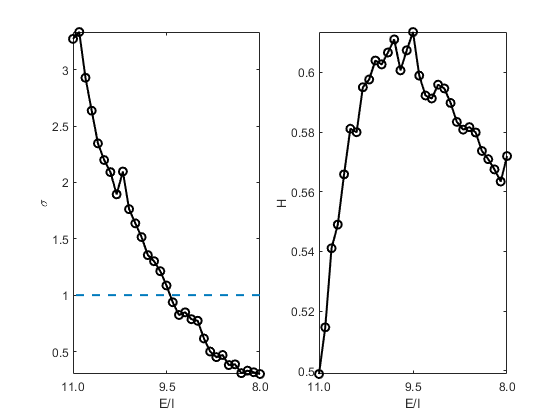

subplot(1, 2, 1), plot(Sigma_average, 'LineWidth', 1.5,  'Color', 'k', 'Marker', 'o');
set(gca,'XDir','reverse');
hold on
subplot(1, 2, 1), plot(ones(length(Sigma_average)), 'LineWidth', 1.5,  'Color', [0 0.47705824 0.741176471], 'LineStyle', '--');
set(gca, 'Xtick', [1, 16, length(Sigma_average)]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'})
xlabel('E/I', 'FontName', 'Arial');
ylabel('\sigma', 'FontName', 'Arial');
axis tight;
hold off;

subplot(1, 2, 2), plot(H_Average, 'LineWidth', 1.5,  'Color', 'k','Marker' ,'o');
set(gca, 'XDir', 'reverse');
xlabel('E/I', 'FontName', 'Arial');
ylabel('H', 'FontName', 'Arial');
set(gca, 'Xtick', [1, 16, length(H_Average)]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'})
axis tight;